## Toy example on how to visualize fastcore model output using the new pipeline

This example is meant to show the different types of visualizations you can do to further inspect your models build with fastcore. 

Read in object with the stored singleModelAnalysis:

working_path = "/Users/leonie.thomas/Documents/fastcore_workflow_with_vanille";
load(working_path + filesep + "context_specific_models" + filesep + "20260119_1042" + filesep + "project_23012026_1453_28012026_1508_obj_vanille_sampling_20260306_sampling.mat")

Execute the comparison model function: 

% choose which models to compare
modelList = ["WT","KO","PLV"];
% choose which of the analysis stored in the object to compare 
% by default: the most recent one (name of the object is the date)
[project, analysisID] = chooseActiveAnalysisForComparison(project,modelList);

% choose the model which entails all the reactions and metabolites
referenceModel = "consistent_medium_constrained_model";
% choose which of the analysis you want to expecute
identifier = "_test";


[project,comparison_name] = modelsComparison(project,modelList, analysisID,...
                                            referenceModel,"modelStructureComparison",identifier);

modelsToTest = 1×4 string array
    "WT"    "KO"    "PLV"    "consistent_medium_constrained_model"


Transcripts will temporarily be removed to allow matching with the discretized data.
1258 of 1261 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1253 of 1256 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1274 of 1277 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1264 of 1267 genes of the model matched


ans = 3×3 table
           count_reactions    count_metabolites    count_genes
           _______________    _________________    ___________

    KO        {[2421]}            {[1951]}          {[1261]}  
    PLV       {[2412]}            {[1939]}          {[1256]}  
    WT        {[2514]}            {[2024]}          {[1277]}  


plots = project.comparisons.(comparison_name).plots;

### Structural vs. Functional model comparison

Working with context-specific metabolic models, 2  of the main analysis routes are the structural vs. the functional model analysis. Since we construct models using fastcormics, the models have different reations in their models. 

Therefore before inspecting the behaviour of the models using FVA, FBA, and sampling we check how different the models are on a structural basis, and how many of those changes are based on the expression data we give as an input. This also is one QC measure of the models, since we ensure that the functional changes we see later in the functional analysis are based on the expression data we give as an input and are not due to other effects. 

#### Size of the context specific models/Feature presence and their inter and outersection between models:

The first step after building a model is to inspect how different the models are, are the meaningful differences between the models that were constructed. Even though that seems trivial when inspecting models build on data from different tissues or different organisms, it is less trivial when the transcrtiptomics data the models are build on are not that heterogeneous, like for in-vitro exeperiments where the only difference is one gene knockdown for example. 

Therefore talking a look at how different the models are in terms of inter and outersections can be critical. 

For the inter- and outersection plots we expect the models to show a high number of intersecting features (genes/reactions/metabolites) since the core metabolism is active in all of the models in order to fullfil the requirement for the biomass. 

- **reaction presence** between models: we see an overlap between all the conditions of over 2000 reactions, which means that 90 % of the reactions are shared between the models, therefore all the functional differences we see in the following analysis come down to the structural differences of those 10% 

- **mets presence** between models: Do the differences between the models on a structural rxns level affect which metabolites can be generated ? Since differen reactions can lead to the production of the same metabolites we expect the outersections to be smaller for the venn diagramm of the metabolites. 

- **gene presence** between models: How many genes are used by the reactions of the outer and intersections ? Most of the genes are involved in multiple rxns + reactions are not all linked to genes, so how many of the reaction changes can actually be mapped to the transcrtiptomics level

**Interpretation:** Given that we here have models with only one knockout we do not expect huge differences + we do expect that a large aspect of the metabolism is the same since the core metabolism needs to be functional. But we have differences at the structural level that can be mapped to genes so to the transcriptomic level. So in the follow up analysis figures, we will investigate where those changes are located in the metabolic network in terms of pathways.

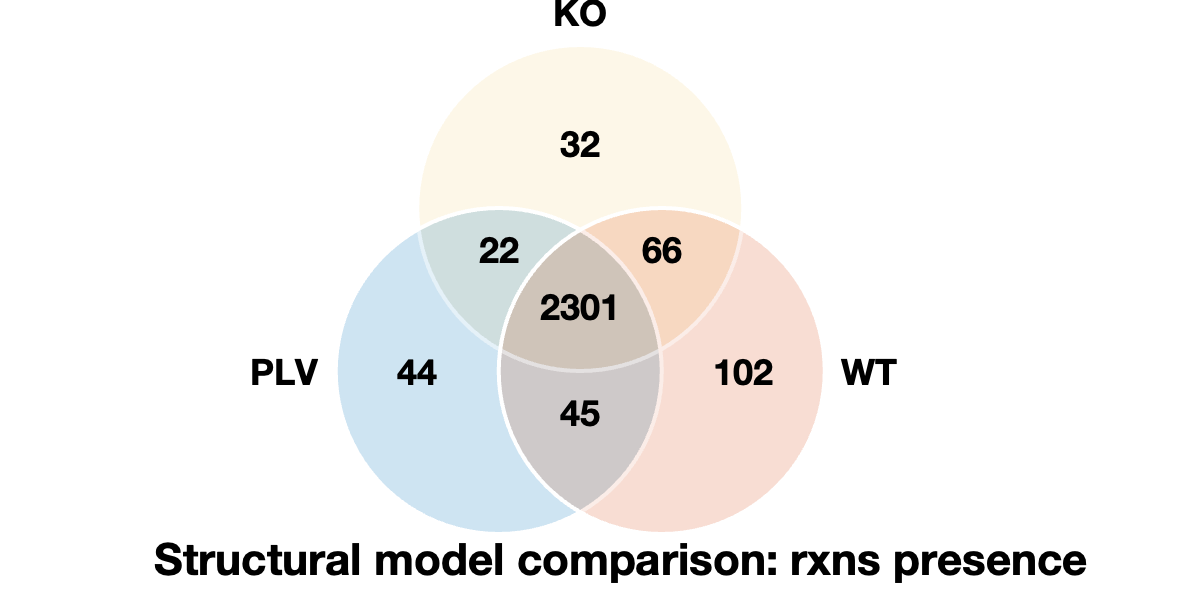

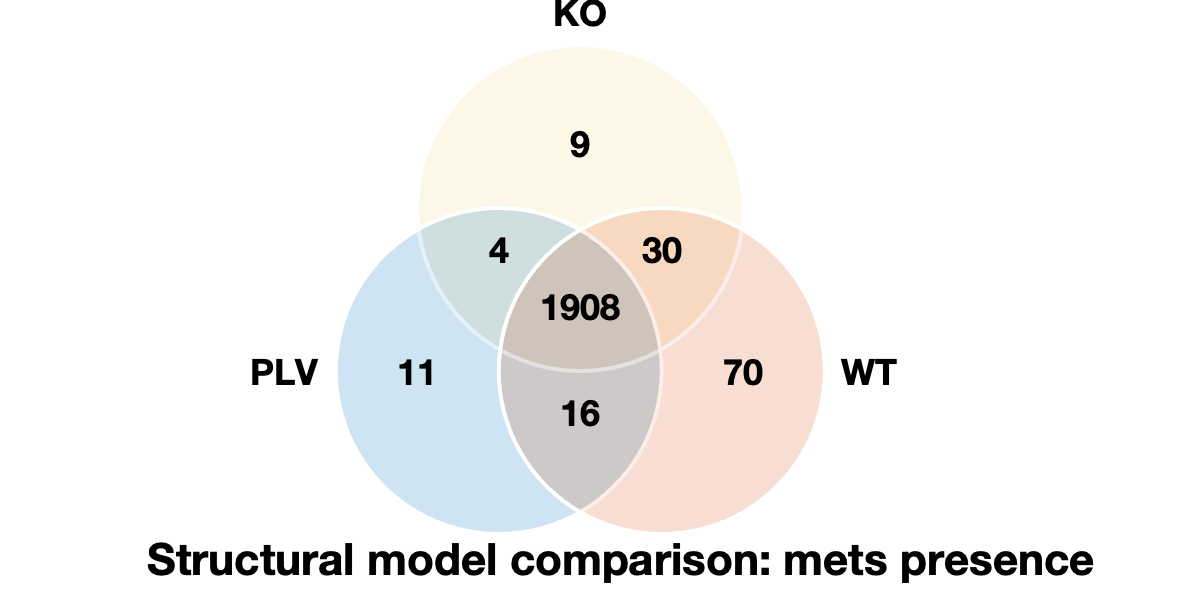

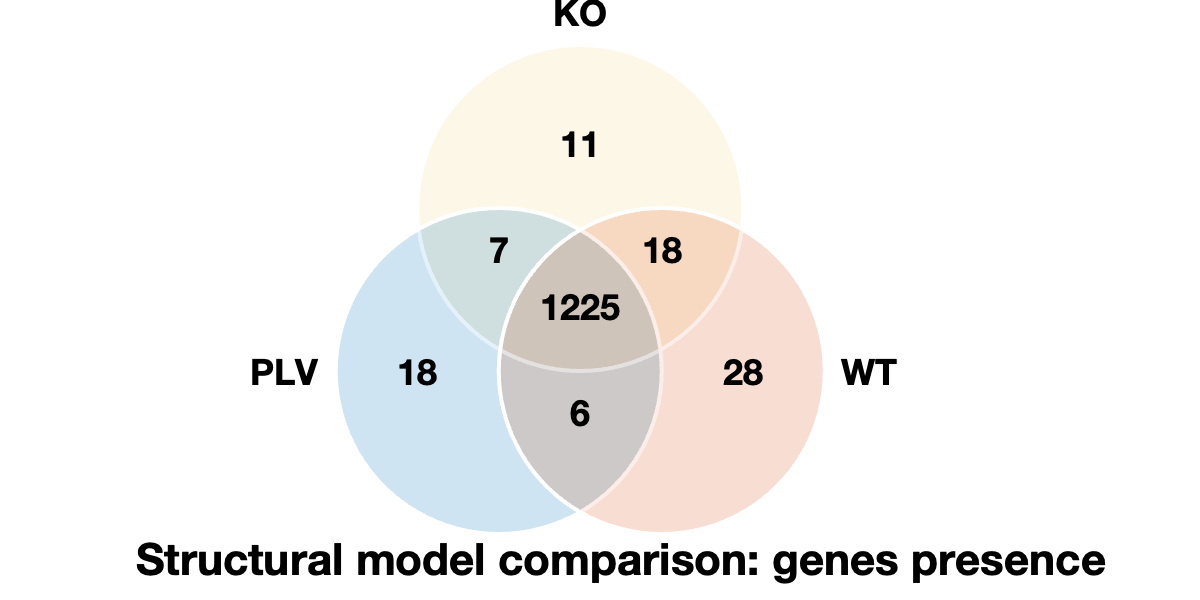

show_figure(plots.struct.intersections.rxns);show_figure(plots.struct.intersections.mets);show_figure(plots.struct.intersections.genes);

**Reaction presence quantified in jaccard similarity: **As implied by the absolute number of reactions in the outer and intersections we can see that a large proportion of the reactions are in all the models, wht a jaccard similarity that is always over 90. We see that the similarity is lowest when comparing the WT with the PLV condition, for metabolites, reactions and genes. We can also see that the jaccard similarity is lowest when computing it over the reaction presence, compared to the genes and metabolites, this also makes sense since not all the reactions are associated with genes and multiple reactions can produce the same metabolites.

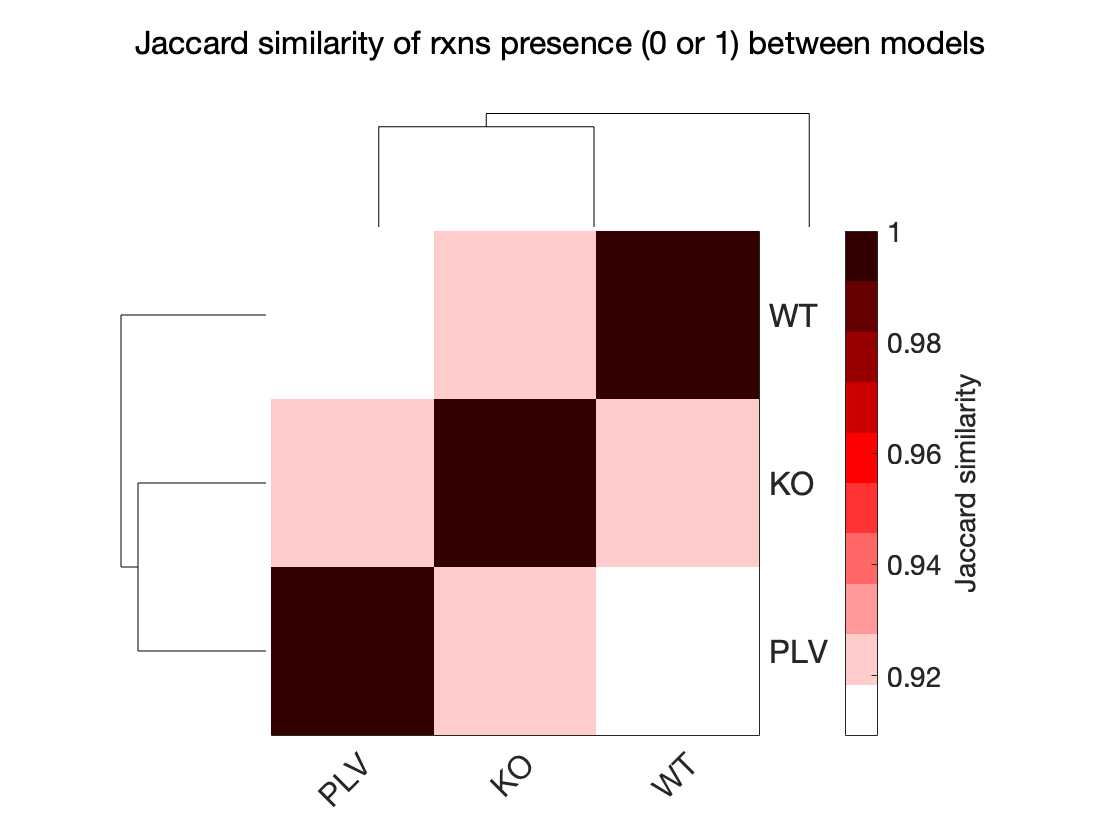

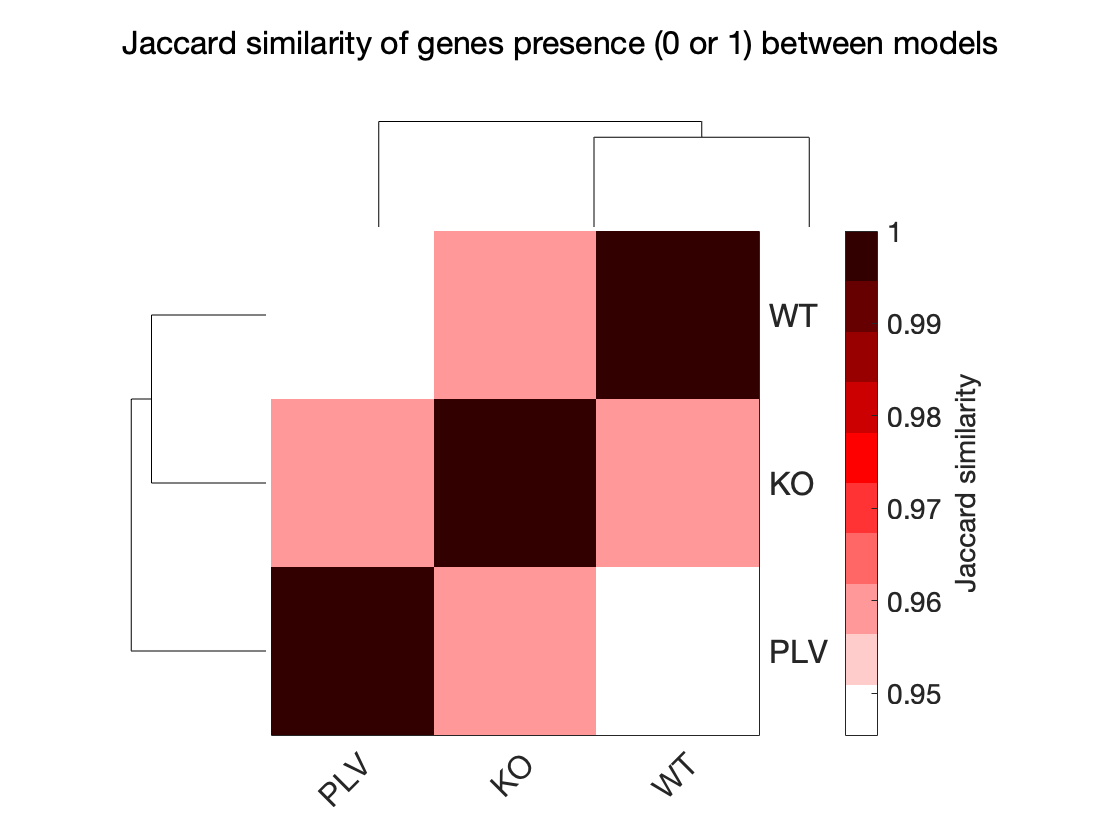

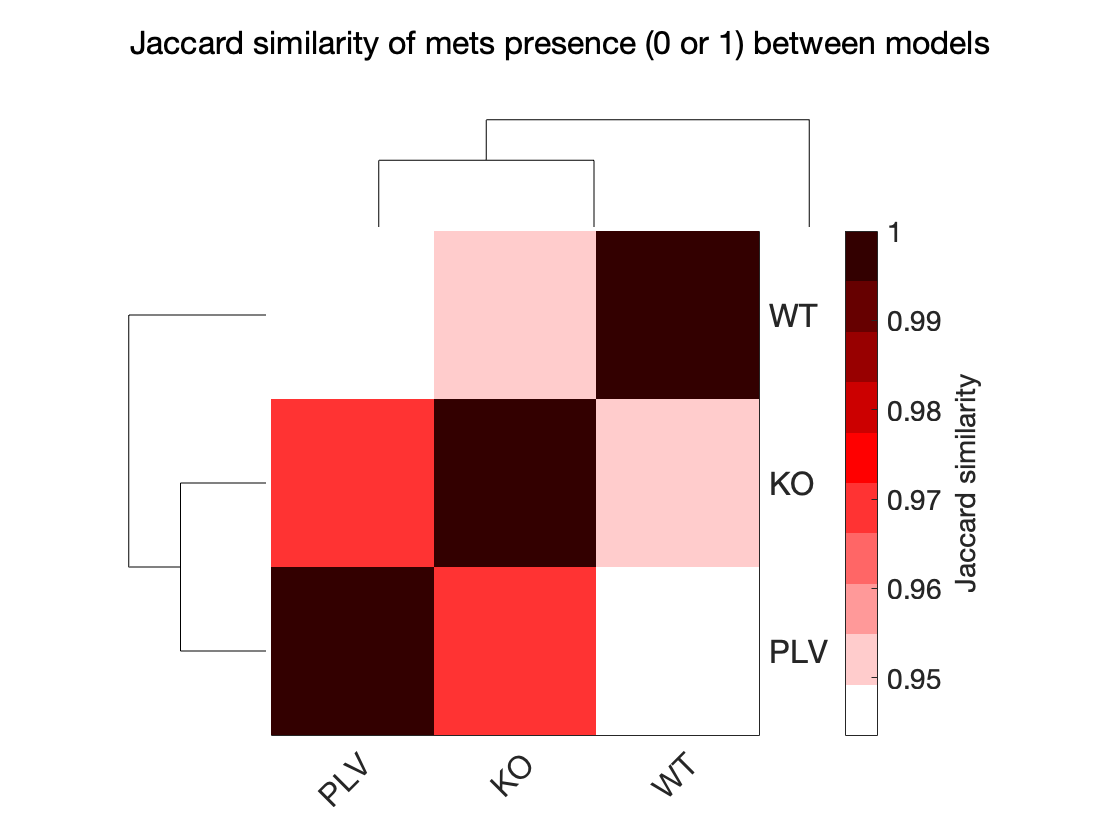

show_figure(plots.struct.jaccard_dist.rxns);show_figure(plots.struct.jaccard_dist.genes);show_figure(plots.struct.jaccard_dist.mets);

**Wants to visualize the intersection for a specific set of rxns ? **

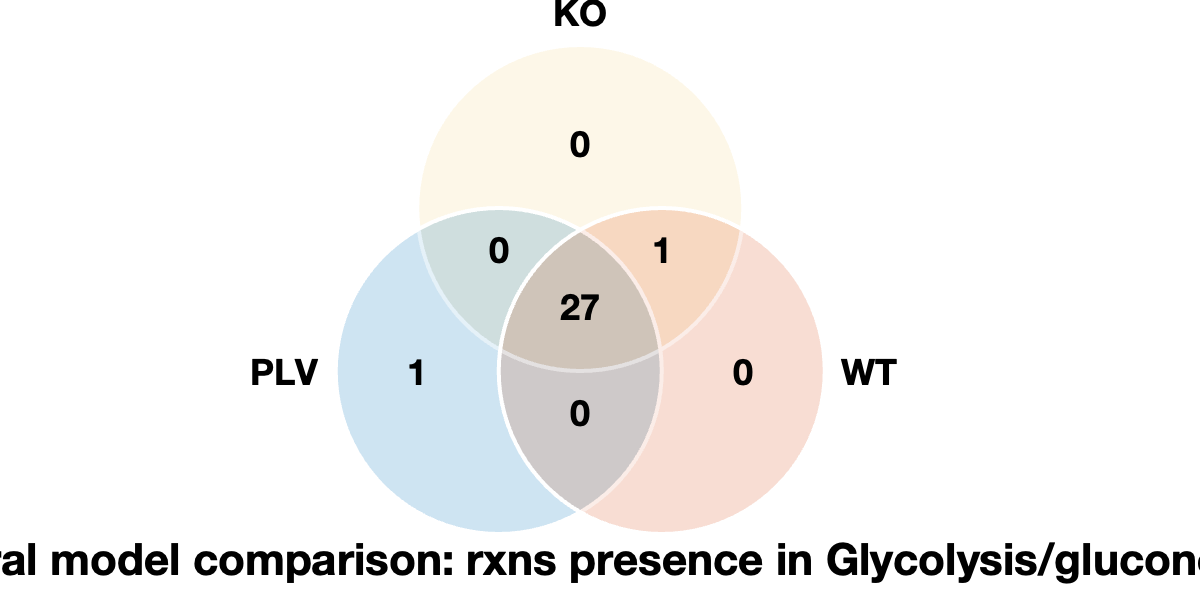

% first access the rxn presence for a specific pathway ? or defined rxn set ? 
% get the rxn_idx of the glycolysis as an example ? 
pathway_to_vis = "Glycolysis/gluconeogenesis";
gly_rxn_idx = find(matches(string(project.models.(referenceModel).model.subSystems),pathway_to_vis));
% get the rxn presence from the comparison object
subsystem_feature_presence = project.comparisons.(comparison_name).rxn_mapping_table{gly_rxn_idx,:} ~= 0;

% generate venn
[fig,idx, ~] = plotFlexibleVenn(subsystem_feature_presence,...
                 project.comparisons.(comparison_name).modelNames, ... 
                 "Structural model comparison: rxns presence in " + pathway_to_vis);

% inspecting the reactions that are in the inter and outersections? 
project.models.(referenceModel).model.rxnNames(idx.PLV)

ans = 1×1 cell array
    {'1-Alpha, 24R, 25-Vitamin D-Hydroxylase (D2)'}


project.models.(referenceModel).model.rxnNames(idx.KO_WT)

ans = 1×1 cell array
    {'6-Glutamyl-10Fthf Transport, Mitochondrial'}


**Want the jaccard similarity over a specific subsystem ?  **A subsystem that makes sense to check is the export and import. Since we gave the cells the same medium to grow on we do not want the exprot and import to be hugely different.

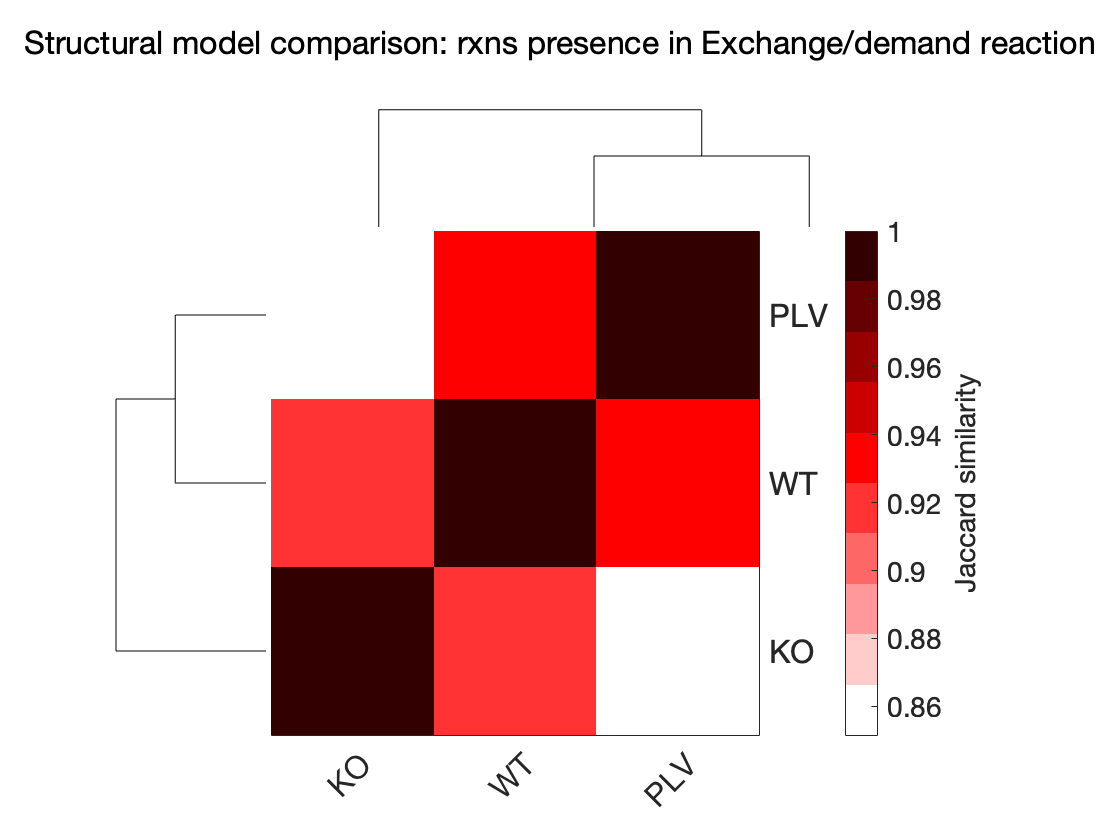

% first access the rxn presence for a specific pathway ? or defined rxn set ? 
% get the rxn_idx of the glycolysis as an example ? 
pathway_to_vis = "Exchange/demand reaction";
gly_rxn_idx = find(matches(string(project.models.(referenceModel).model.subSystems),pathway_to_vis));
% get the rxn presence from the comparison object
subsystem_feature_presence = project.comparisons.(comparison_name).rxn_mapping_table{gly_rxn_idx,:} ~= 0;

plotJaccard(subsystem_feature_presence,...
                 project.comparisons.(comparison_name).modelNames, ... 
                 "Structural model comparison: rxns presence in " + pathway_to_vis);

**All the structural differences that we see in the model comparison how many of them are due to the core reactions defined based on the expression ? **

In the figure below we see that from all the approx. 2500 rxns per  model around 60 percent are in the model because there were binarized to be core model reactions based on the expression of the genes coding for the enzymes of this reaction. So the 60 percent that you see in the upper left figure are the core reactions that made it into the model, but how many core reactions were defined based on the expression data ? Ideally you would want all the core reactions to make it into the model, this means the upper right figure would show us 100 percent. As you see for the models we are currently building the percentage is more around 74%. Adjusting the thresholding of the discretization approach could help to find a trade of between the two figures, as much core reactions as possible in the model, while sustaining to have the higher proportion of core against non-core reactions.

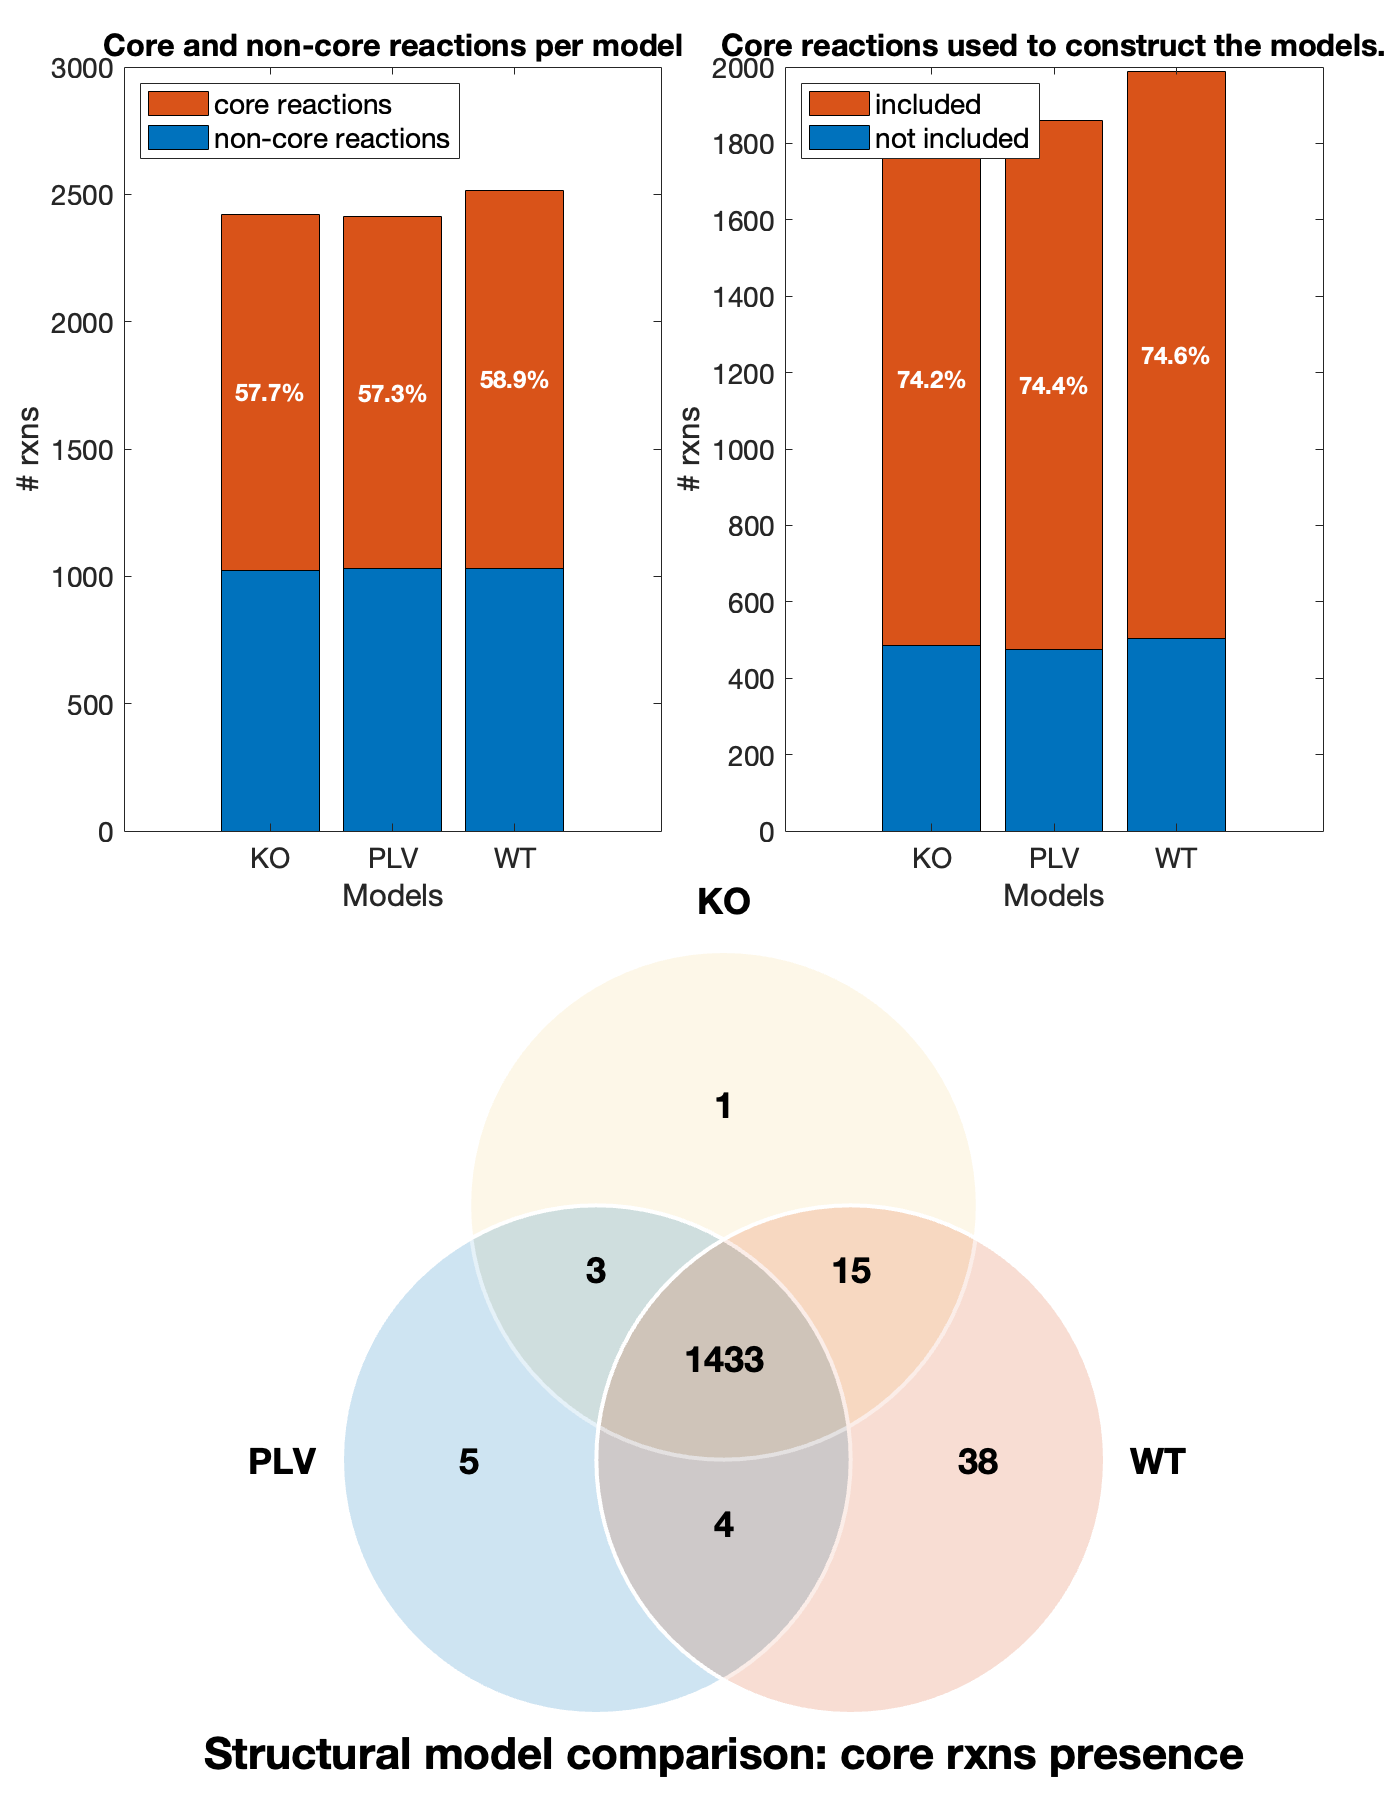

set(plots.struct.core_reactions,'Position', [100 100 700 900]) % resize so it is comfortable to read the whole figure!
show_figure(plots.struct.core_reactions);

Here we see that the outersections for the core reactions is a lot lower compared to the outersections we saw on all the reactions. The core reactions define which of the non-core reactions need to be added to make a model consistent + able to carry biomass. Which pathways do the rxns in the outersections belong too ? 

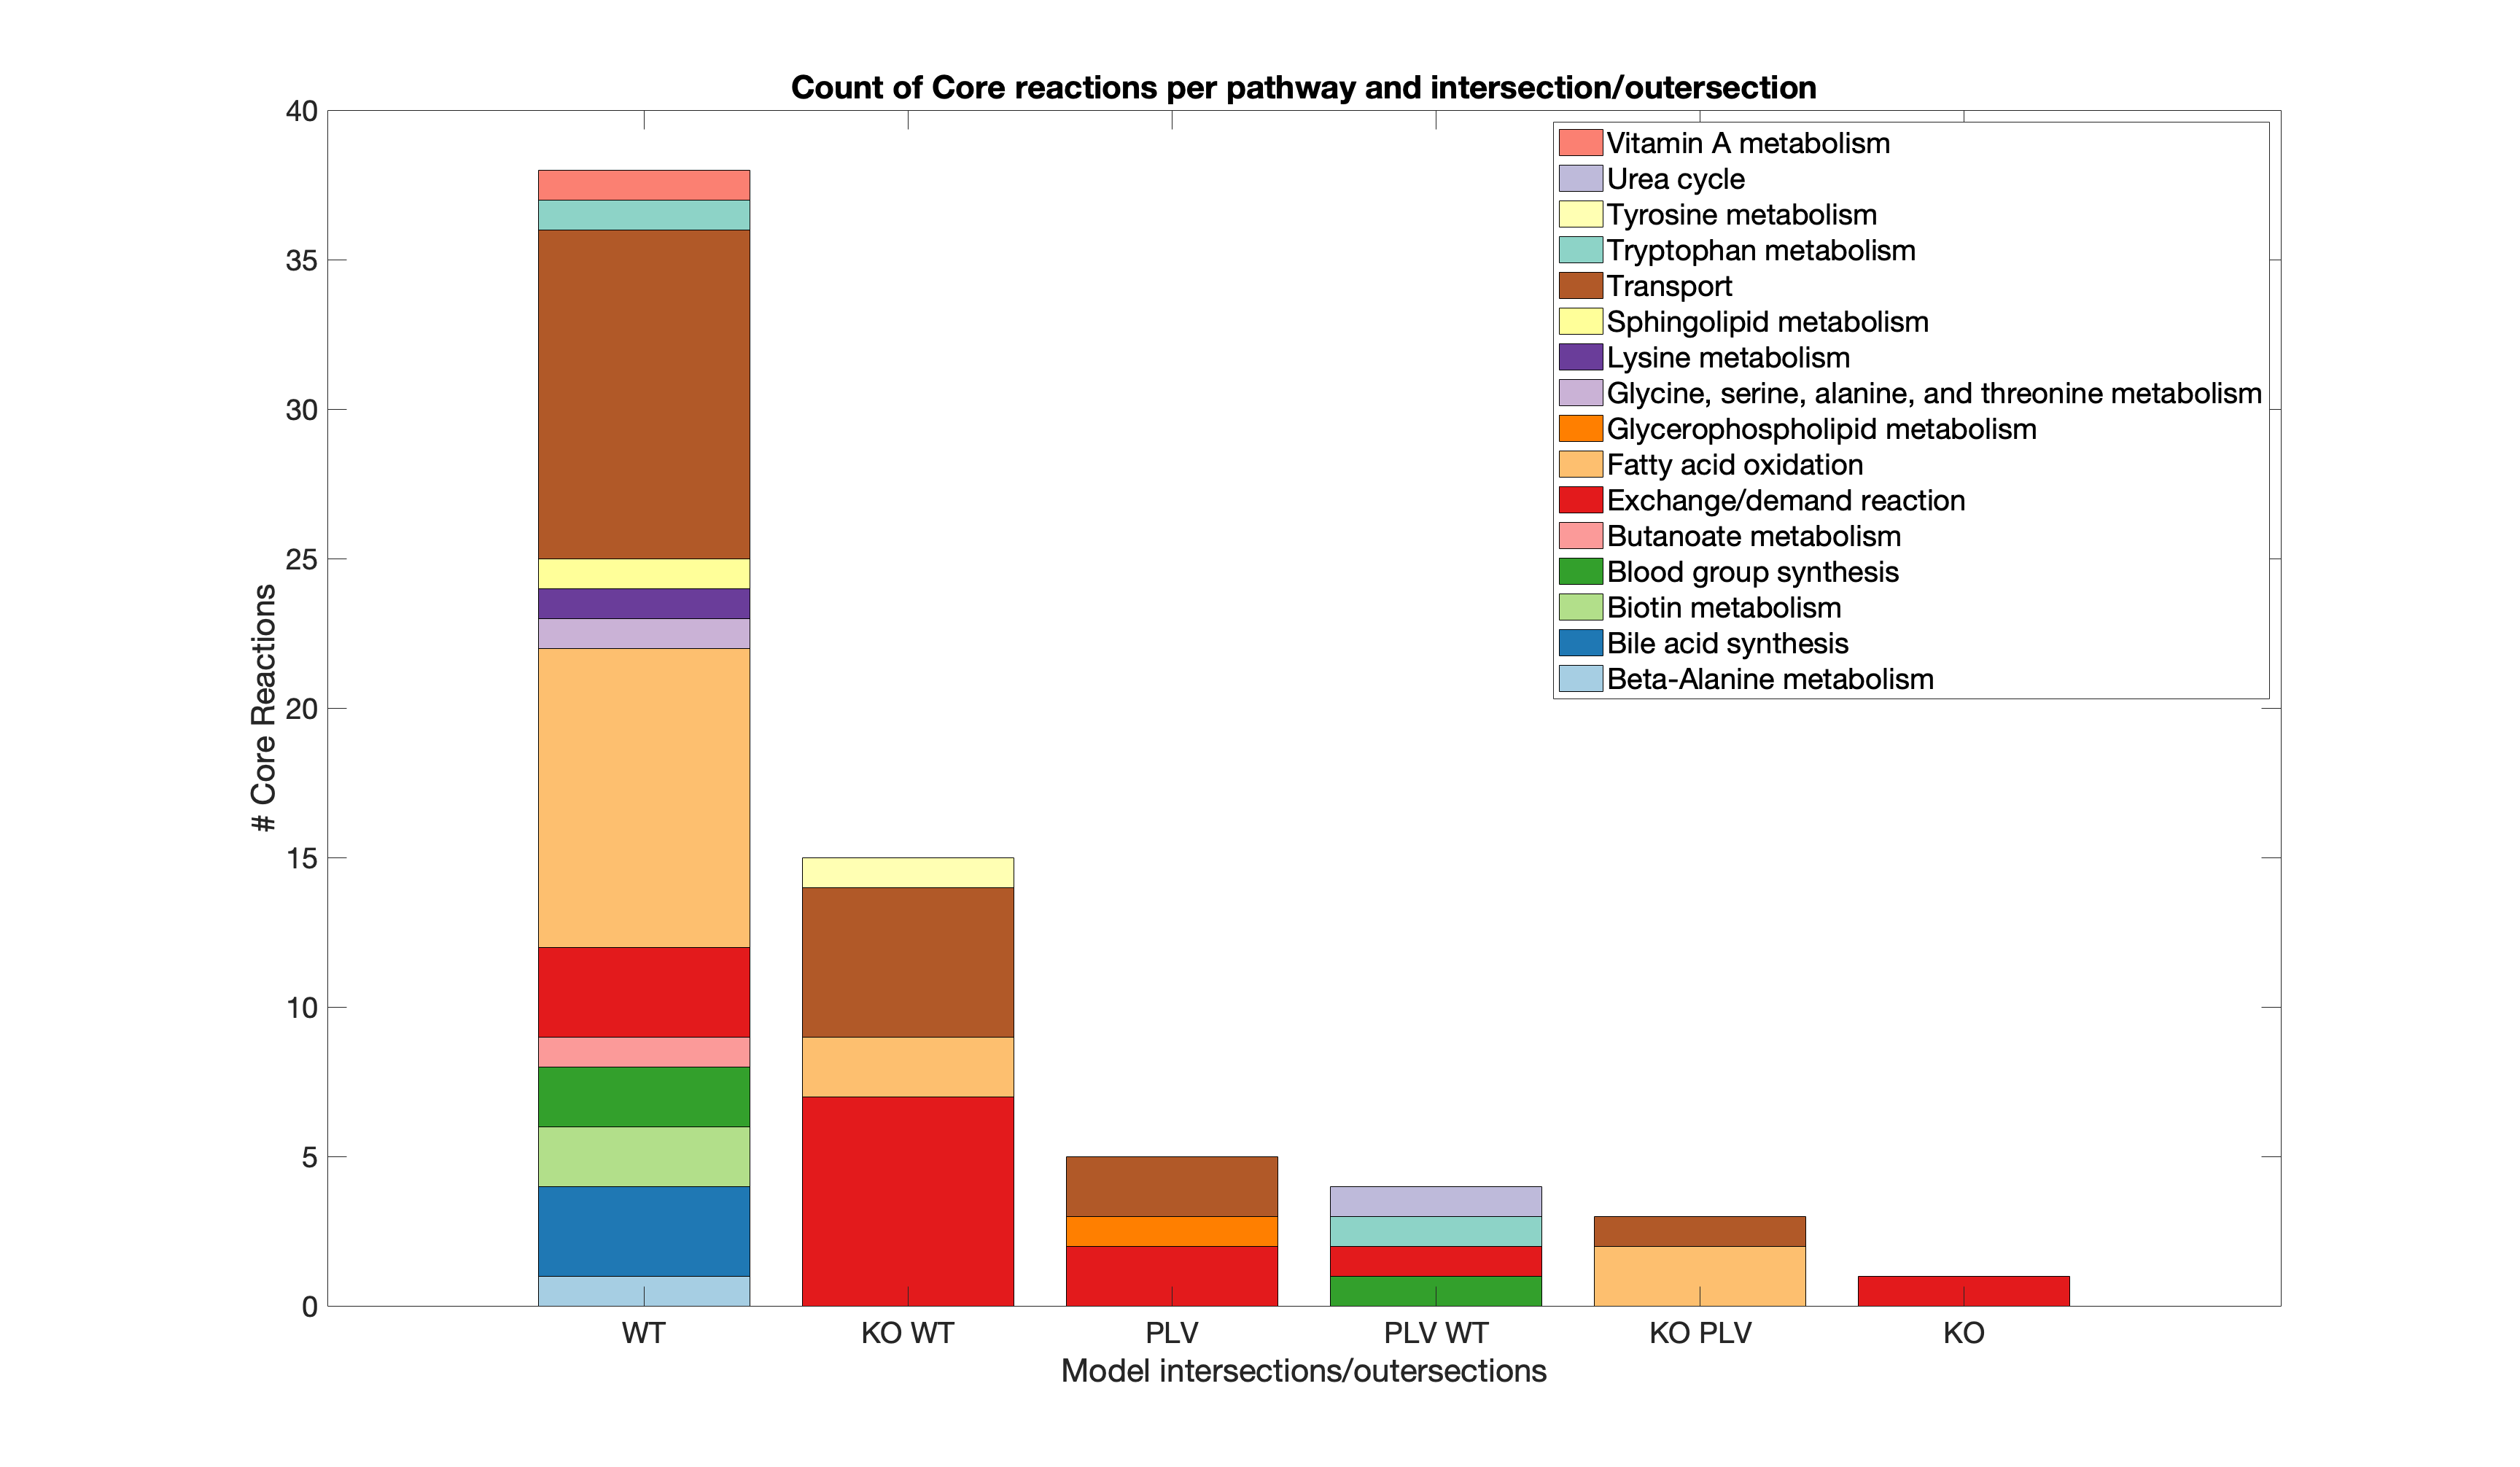

show_figure(plots.struct.core_reactions_intersections)

As also seen before for all the reactions the highest amount of rxns (besides the intersection of all models) is associated with the WT (wild type) model. The rxns in the core of model WT specifically are part of mainly Transport and Exchange/demand reactions reactions, but also Fatty acid oxidation and Bile acid synthesis. In addition the KO model shares a few reactions of the Fatty acid oxidation with the WT and the PLV model (2nd and 5th bar). This plot serves more as a QC to check that the rxns that are added to the core and are thereby defining the model construction are not only Exchangers and Transport rxns but also other parts of the metabolism. Interestingly we see that the absence of some of some core rxns of the Fatty acid oxidation seems to play a major role in the differences between the models. 

**QC - overview of the discretization of the data:**

As mentioned previously the core reactions are defined on basis of a discretization step. Here we get an overview about how the genes that are in the model were discretized. 

The first figure (left) shows the discretization of the transcrtiptomics data on basis of the approx. 1200 genes that are defined in the metabolic model. Around 50 % percent were after the application of a sample specifc thershold been categorized to be active (1), around 3 percent were categorized to have an unknown expression status (0) and 10-20 % are discretized to be unexpressed (-1). So we see that only 50 percent of the genes that are in our  context specific models are also labeled to be active, this is due to the fact that one reaction is connected to multiple genes and therefore a gene can still be in the gpr rules of the model while not being discretized as active. This we then see when we switcht from the gene level to the reaction level (middel subfigure) where the mapping of the gene expression status to the rxn activation status is made, and here we see the model is compromised of 60 percent of reactions for which the discretization status is (1)( this is the core we saw in the previous figure already) while around 40 percent are through to have a unknown status. As you can see the reactions with 0 status can be added to the mdoel while the reactions with -1 will not be added to the model (with only a few exceptions - hence the blue bar on the bottom of the 2 rightmost subfigures). After looking at the discretization status per sample the samples are combined into the respective models, and as we see in the rightmost plot there is no big changes in the discretization status after applying the consensus proportion. The consensus proportion is something that can be adjusted too. With this figures it is important to check that we see the same tendendies in discretization on the sample as on the conrresponding model level. Which we do see here - no outliers on the sample level that could influence the consensus model construction.

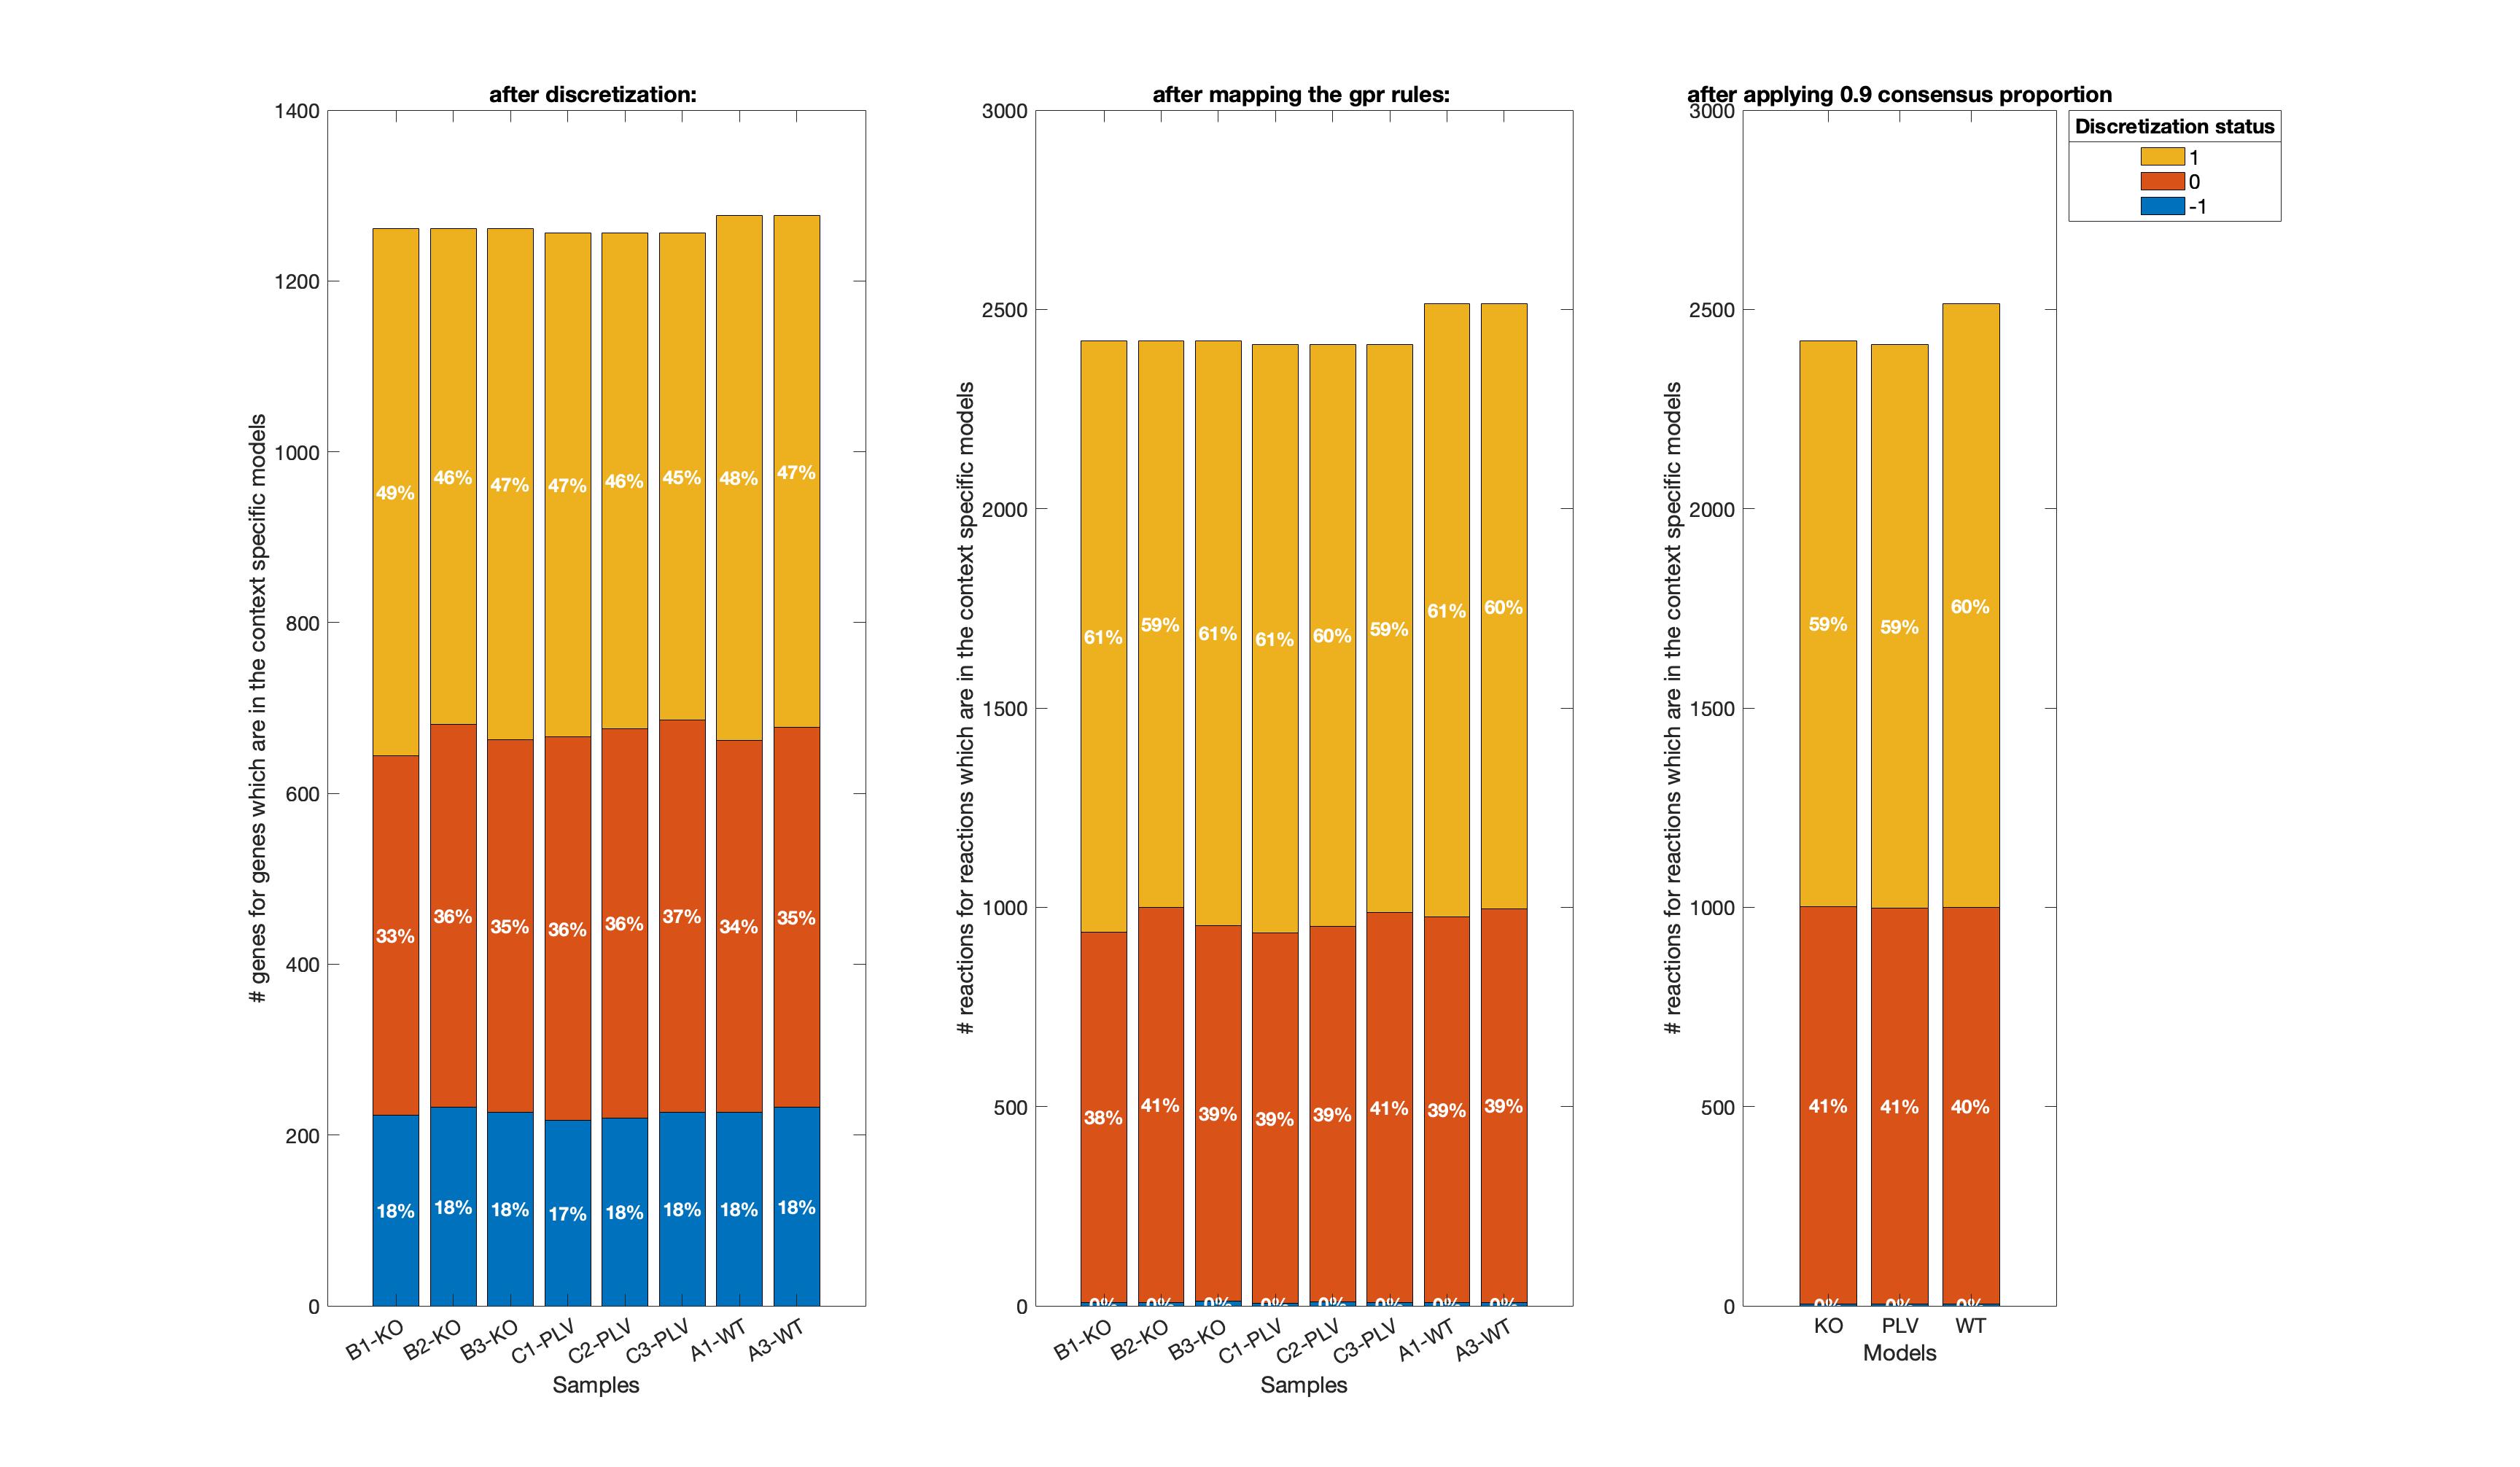

set(plots.struct.data_discretization,'Position', [100 100 3000 2000]) % resize so it is comfortable to read the whole figure!
show_figure(plots.struct.data_discretization)

**Which subsystem is enriched for structural changes? **

This figure shows in which subsystem the structural changes can be found. The heatmap is ordered by the variance in rxn count between models. So at the top you will find pathways which in absolute rxns counts are most different between models. The number of rxns per pathway is written into the tiles, while the color indicates how many of the rxns from the reference model can be found in each of the context specific models. 

A few observations can be made on basis of this figure and will be discussed in the following: 

- The heparan sulfate degradation is the subsystem which has the most difference in rxn count. This means that for the WT all the rxns that are in the reference model are retained, while for the KO and PLV model the reactions are eradicated. Of note here is that looking at the core reactions that are specific to WT, there is no reaction from the heparan subsystem, stating the question why we have so much structural change in this subsystem even though there is nothing in the core ? Maybe a metabolite produced by another subsystem is produced in WT and not in the KO & PLV. So it does not have to be metabolized in the PLV & KO model ?? A similar behaviour can be observed for the Chondroitin synthesis

- Fatty acid oxidation is a big subsystem and for all of the models around 50 % of the reactions from the reference model are kept. But there are more reactions in the WT model, which makes sense since we saw that 15 of the reactions defined to be core in WT but not in the other two models are form the Fatty acid oxidation. 

- The Biotin metabolism is specifically not active in the PLV model, while for the WT model we have seen that there are 2 rxns which are specific for the WT model only this does not explain why the biotin metabolism is active in KO but not in PLV. 

Paper linking the degradation of heparan sulfate to NO. The KO of GSNOR leads to less bioavailable NO and therefore the heparan sulfate degradation does not take place ? see publication: [https://www.sciencedirect.com/science/article/pii/S0021925819717980?via%3Dihub#bib23](https://www.sciencedirect.com/science/article/pii/S0021925819717980?via%3Dihub#bib23)

heparan sulfate as mudlator of breast cancer progression ? https://pmc.ncbi.nlm.nih.gov/articles/PMC3747466/?utm_source

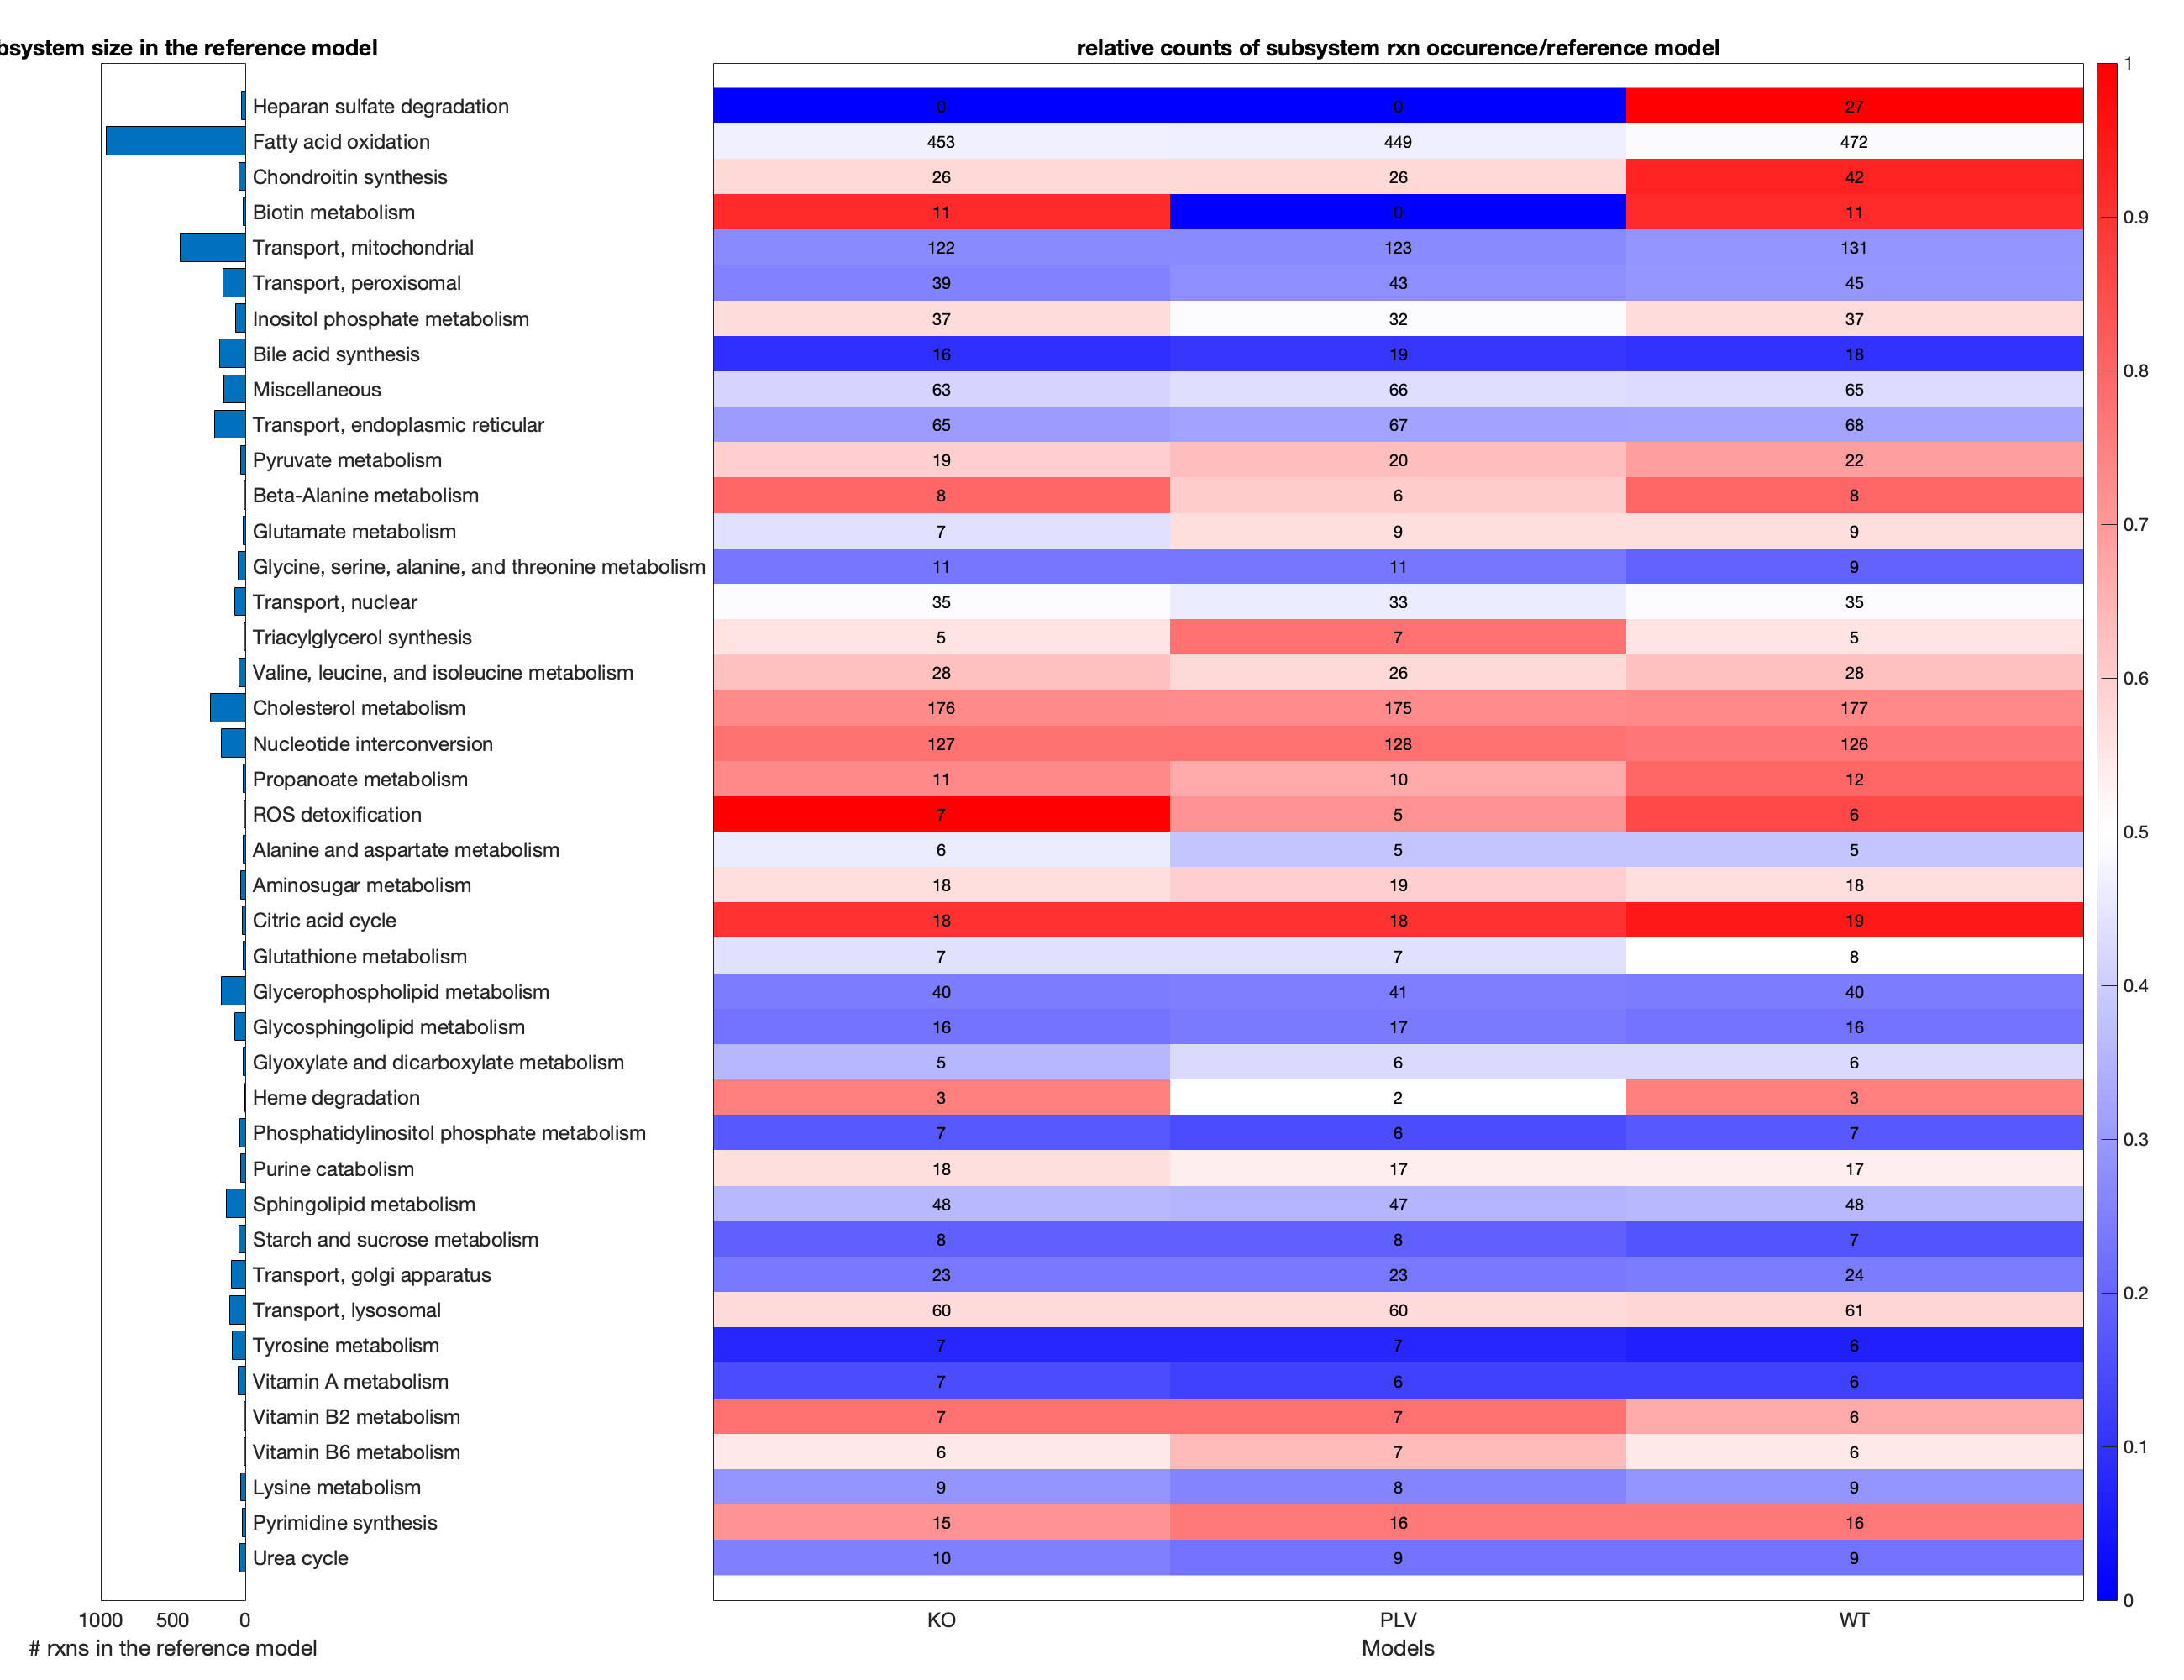

set(plots.struct.reaction_pathway_presence,'Position', [100 100 1300 1000]) % resize so it is comfortable to read the whole figure!
show_figure(plots.struct.reaction_pathway_presence)

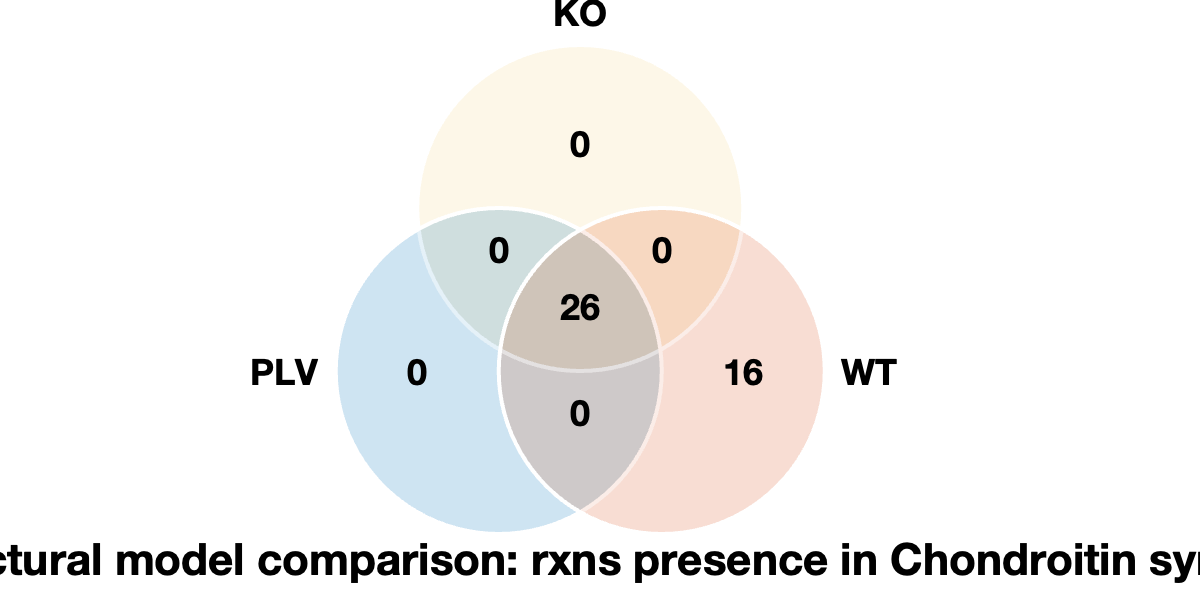


% first access the rxn presence for a specific pathway ? or defined rxn set ? 
% get the rxn_idx of the glycolysis as an example ? 
pathway_to_vis = "Chondroitin synthesis";
gly_rxn_idx = find(matches(string(project.models.(referenceModel).model.subSystems),pathway_to_vis));
% get the rxn presence from the comparison object
subsystem_feature_presence = project.comparisons.(comparison_name).rxn_mapping_table{gly_rxn_idx,:} ~= 0;

% generate venn
[fig,idx, ~] = plotFlexibleVenn(subsystem_feature_presence,...
                 project.comparisons.(comparison_name).modelNames, ... 
                 "Structural model comparison: rxns presence in " + pathway_to_vis);

project.models.(referenceModel).model.rxnNames(idx.KO_WT)


ans =

  0×1 empty cell array



project.models.(referenceModel).model.rxns(idx.WT)

ans = 16×1 cell array
    {'11DOCRTSLtm'    }
    {'1a_24_25VITD2Hm'}
    {'1a_25VITD2Hm'   }
    {'1MNCAMti'       }
    {'1PPDCRp'        }
    {'24_25DHVITD2tm' }
    {'24_25DHVITD3t'  }
    {'24_25DHVITD3tm' }
    {'24_25VITD2Hm'   }
    {'24_25VITD3Hm'   }
    {'24NPHte'        }
    {'25HVITD3tin_m'  }
    {'25VITD2Hm'      }
    {'25VITD3Hm'      }
    {'2AMACHYD'       }
    {'34DHPHEt'       }


### Functional analysis of the models: FBA, FVA and sampling

modelsToTest = 1×4 string array
    "WT"    "KO"    "PLV"    "consistent_medium_constrained_model"


Transcripts will temporarily be removed to allow matching with the discretized data.
1258 of 1261 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1253 of 1256 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1274 of 1277 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1264 of 1267 genes of the model matched


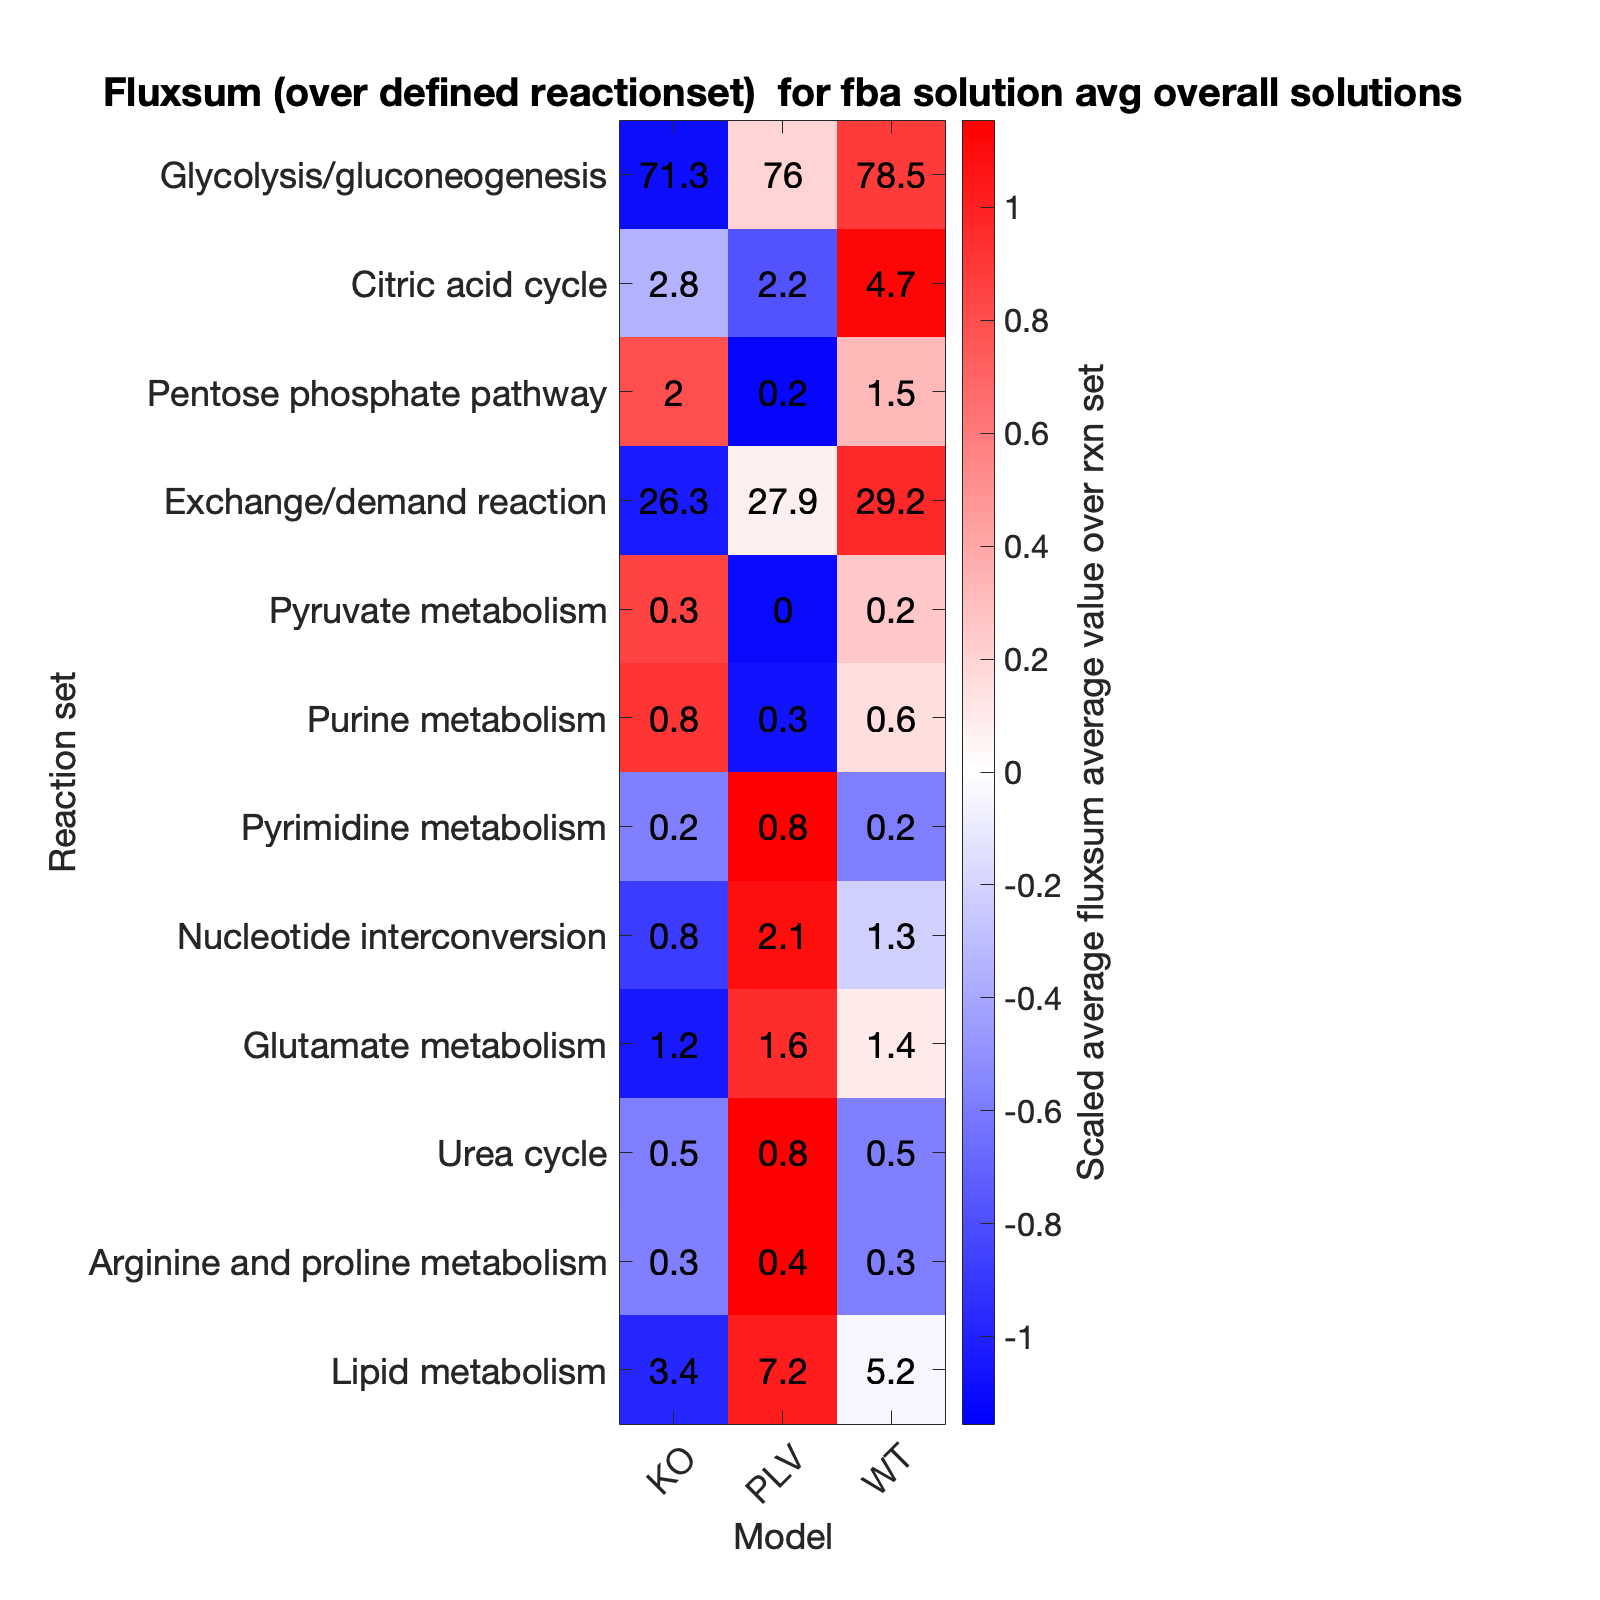

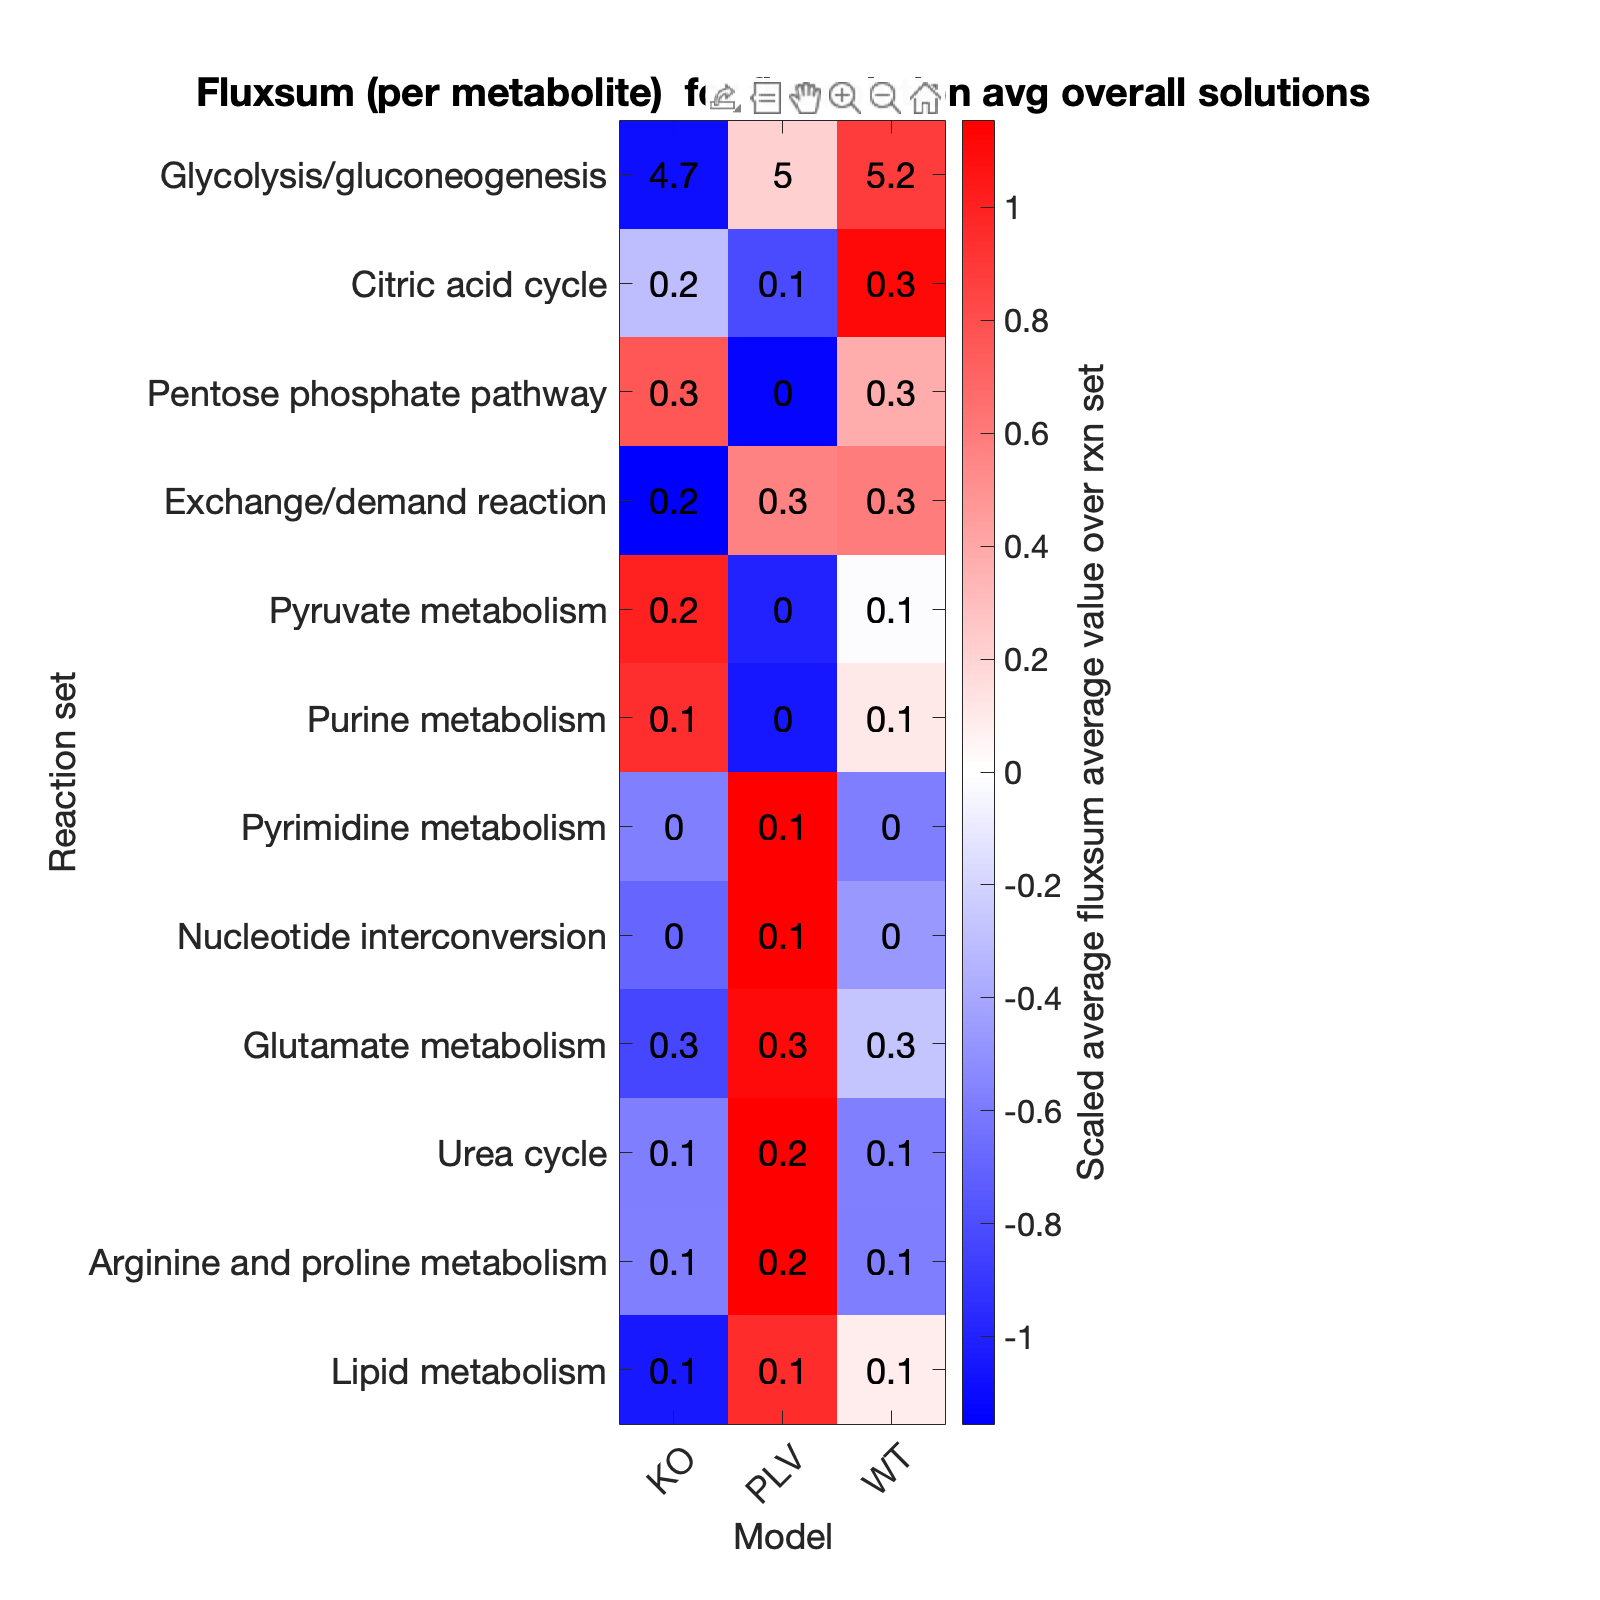

[project,comparison_name] = modelsComparison(project,modelList, analysisID,...
                                             referenceModel,"modelFunctionalComparison",identifier);

**On what do the models grow ? FBA solution: **

plots = project.comparisons.(comparison_name).plots;
show_figure(plots.funct.import)
show_figure(plots.funct.export)

show_figure(plots.funct.fba.heatmap_rxn_activity_fba)

MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ViewModel' for class 'handle'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 476)
            parentView = parentController.ViewModel;
                         ^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 

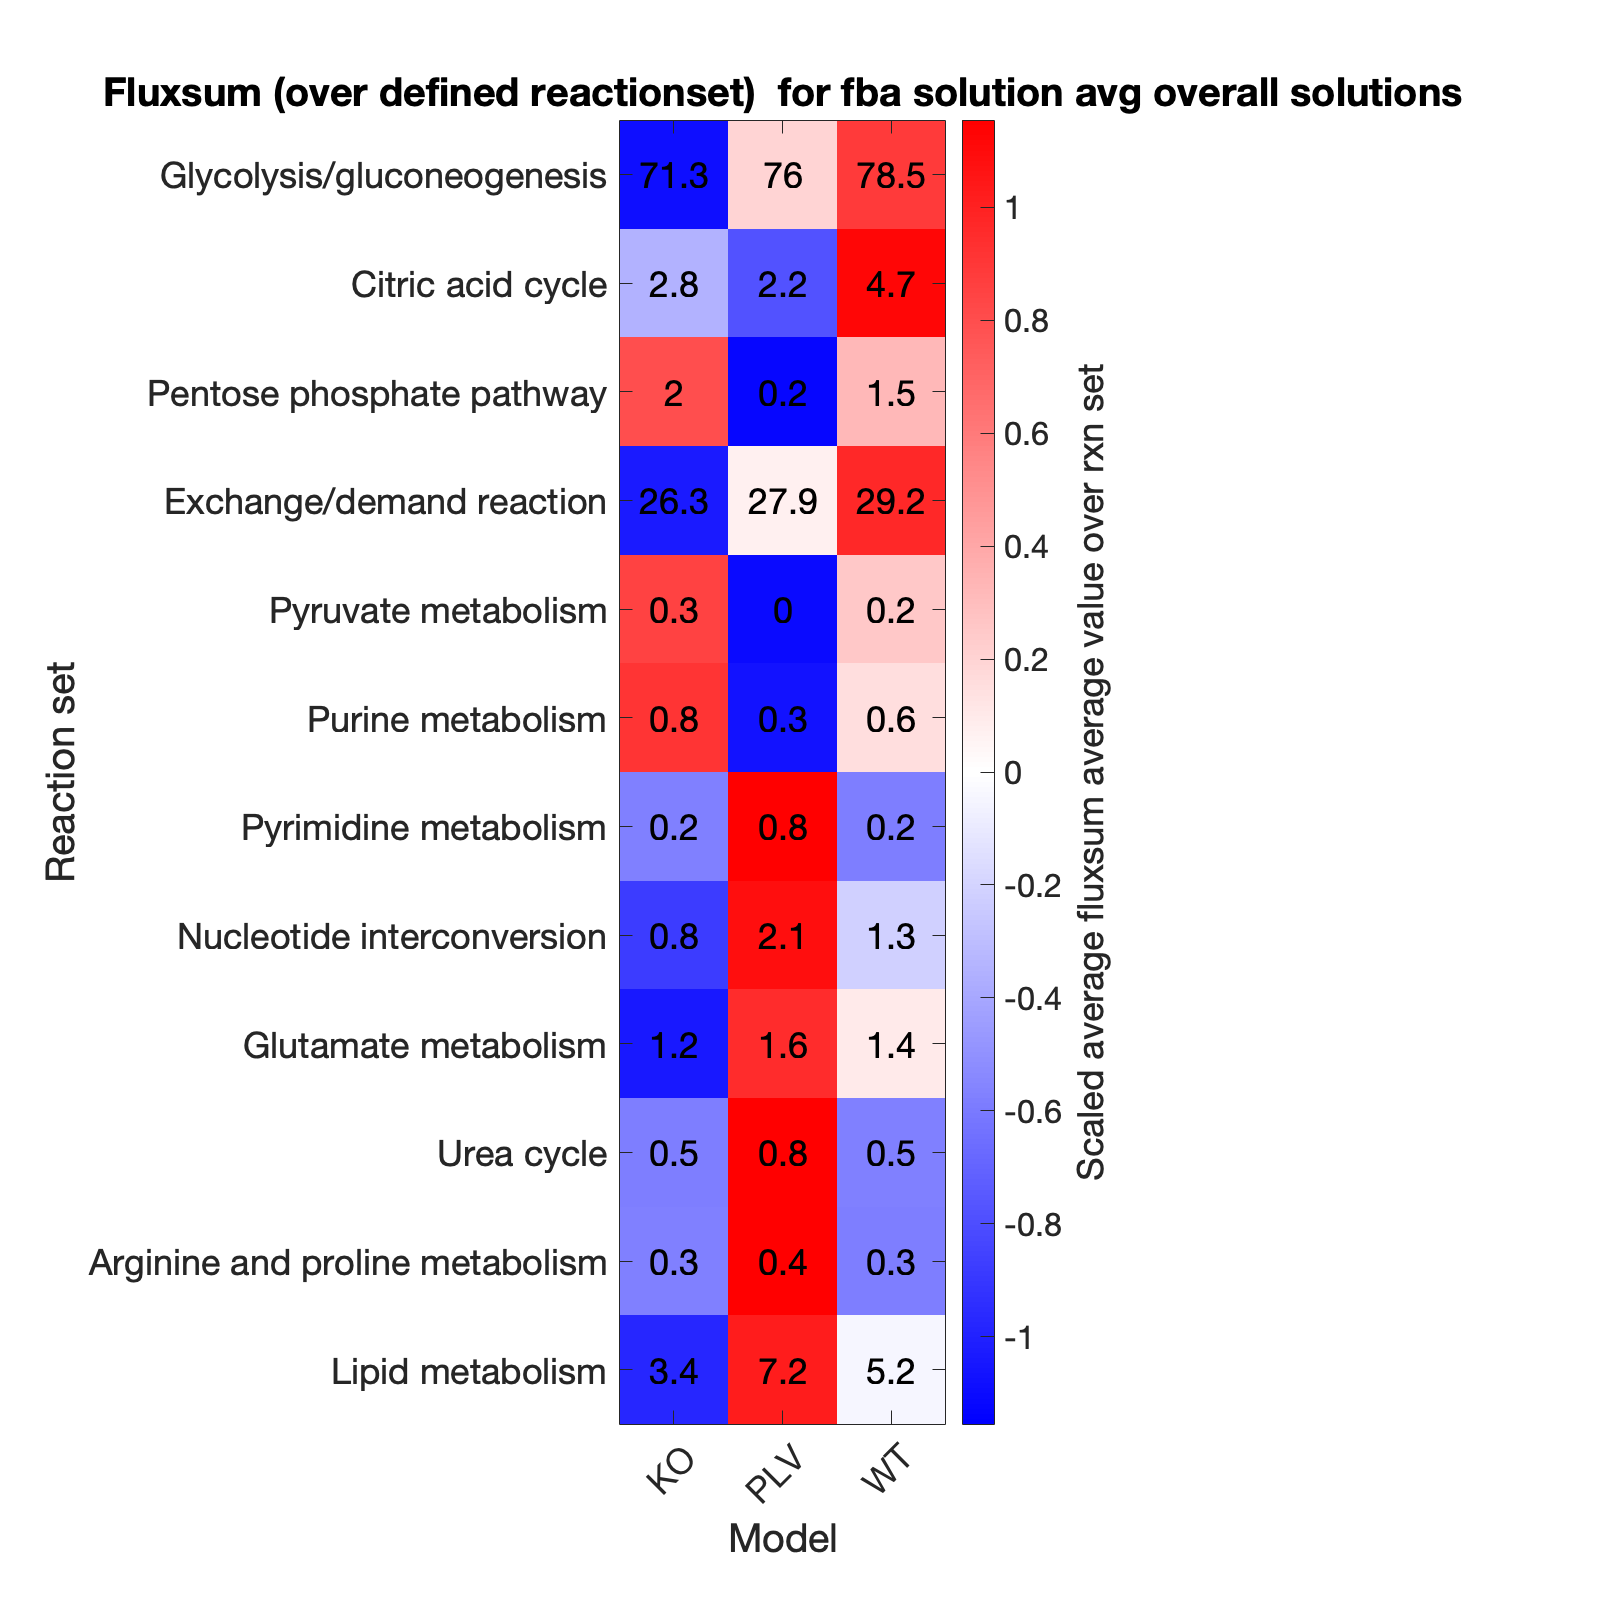

show_figure(plots.funct.fba.heatmap_rxn_fluxsum)

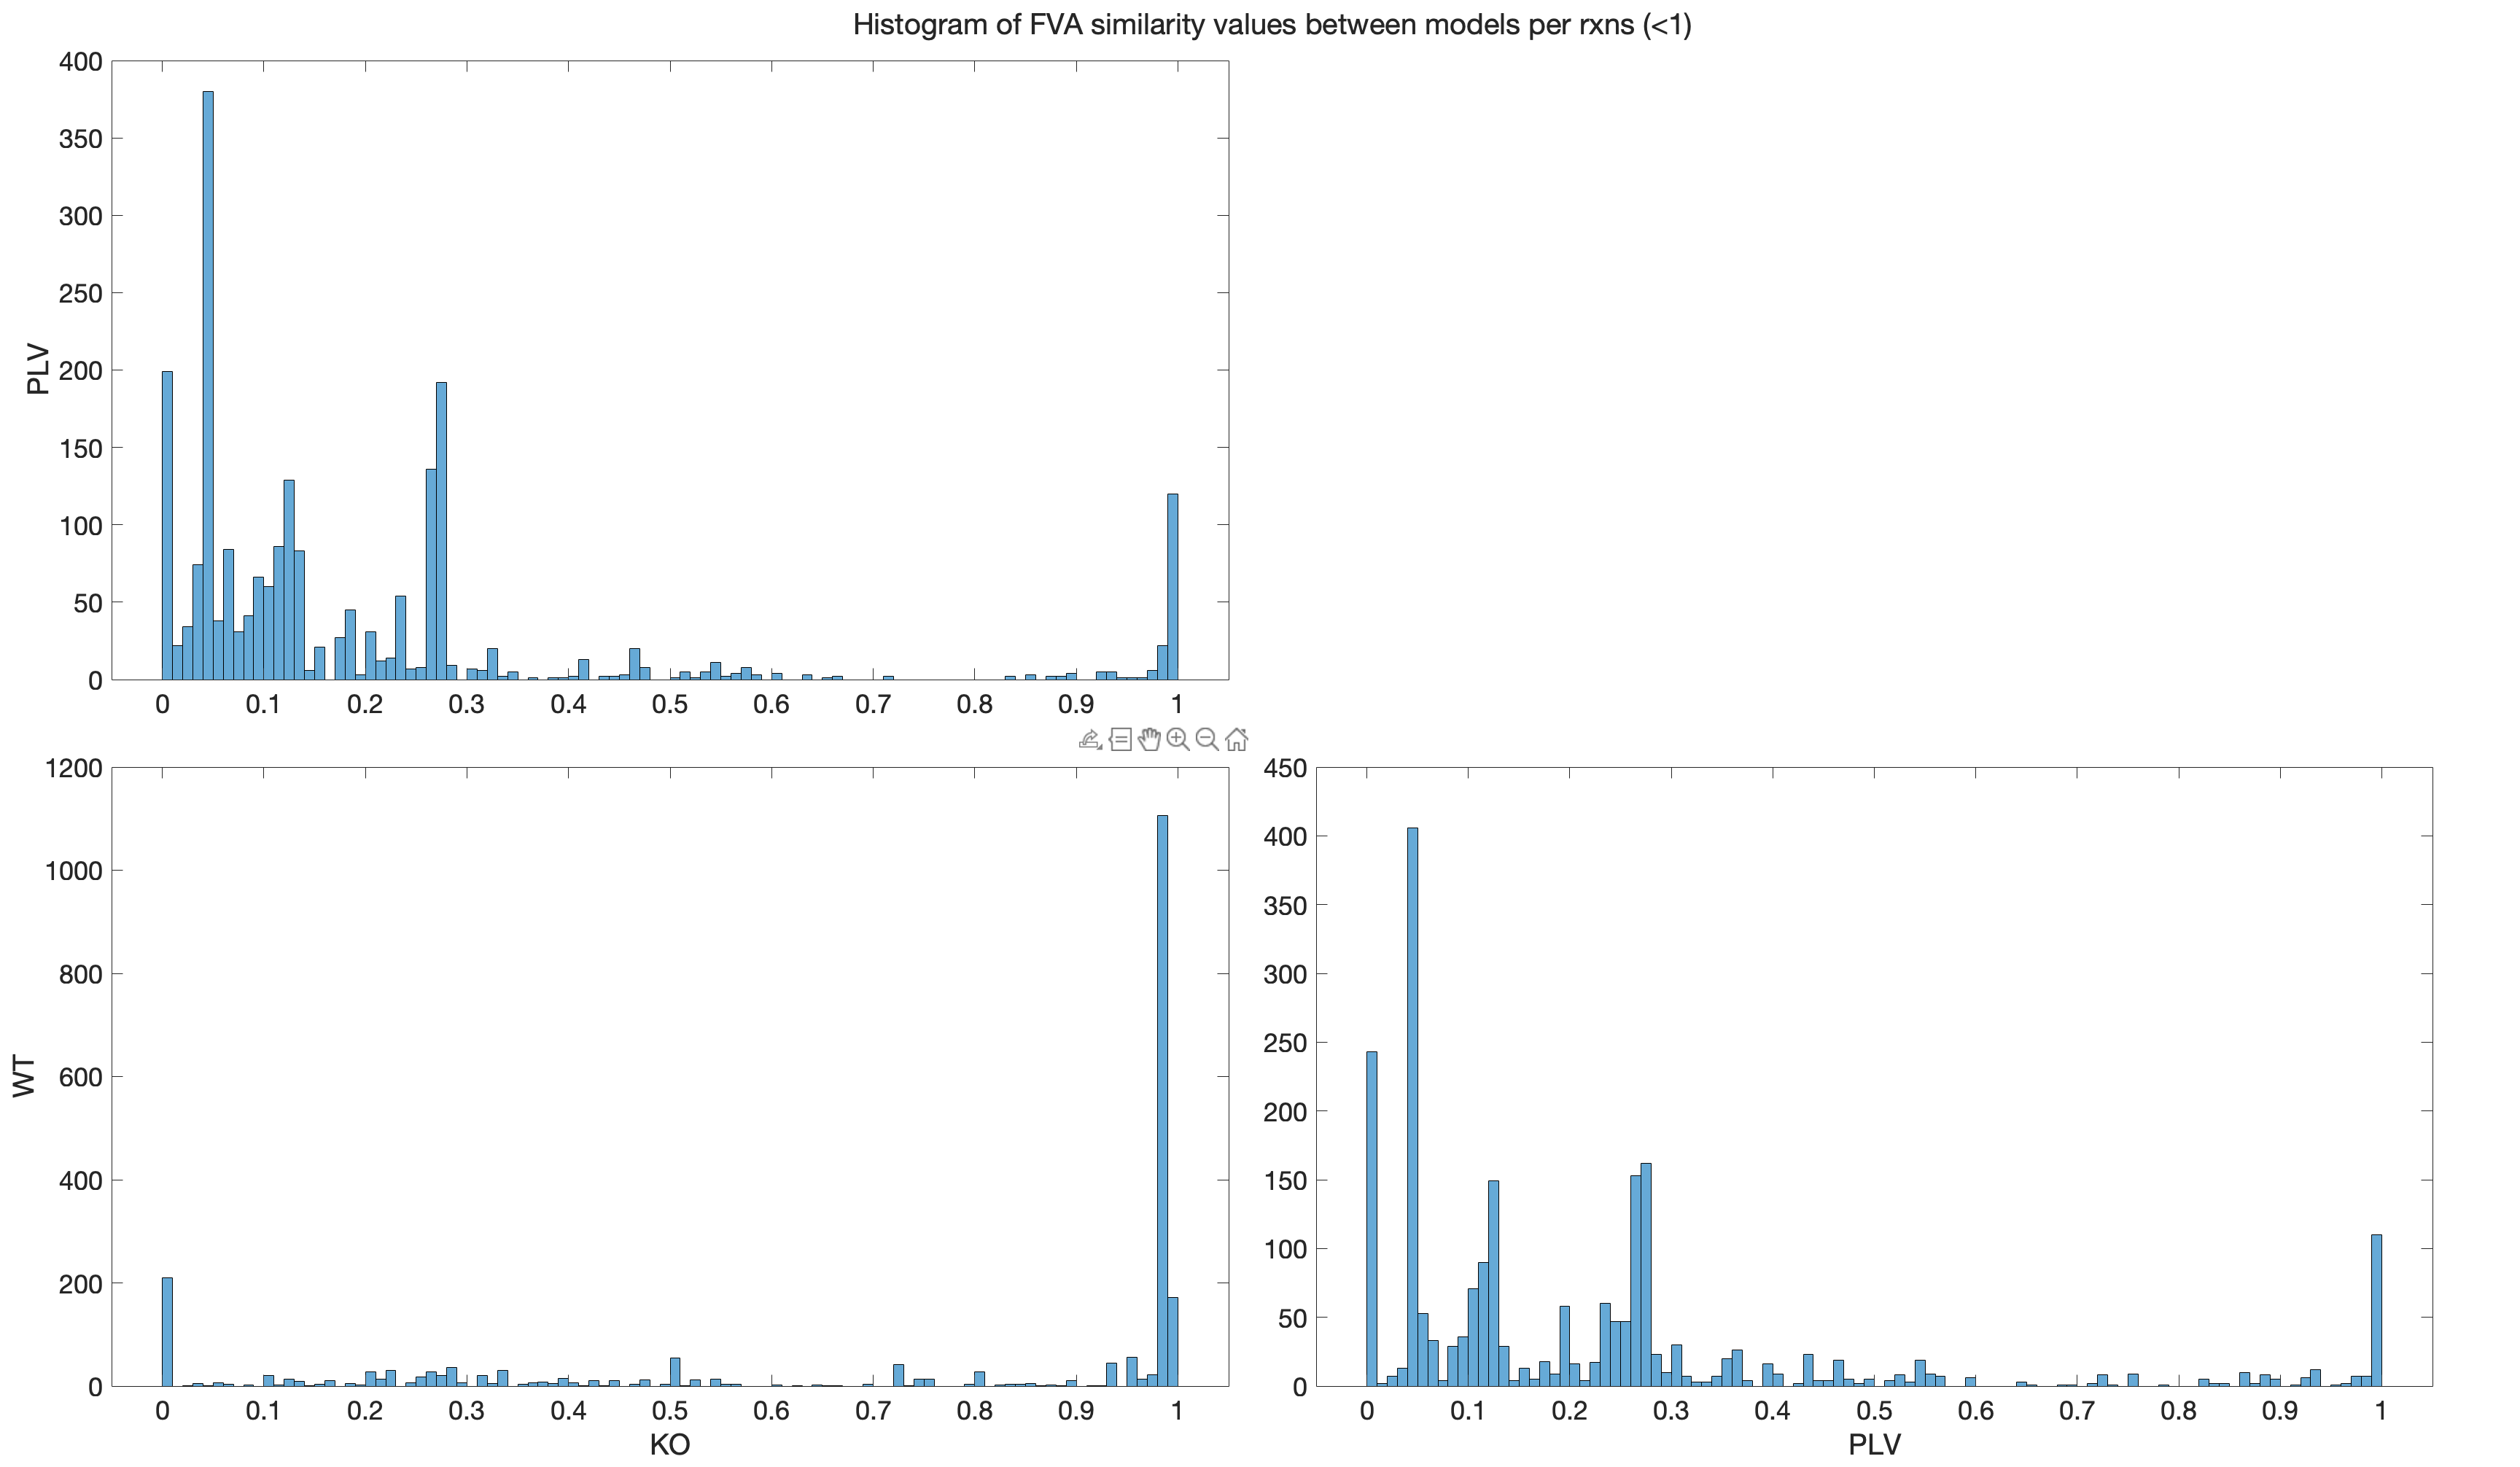

show_figure(plots.funct.fva_sim.hist)

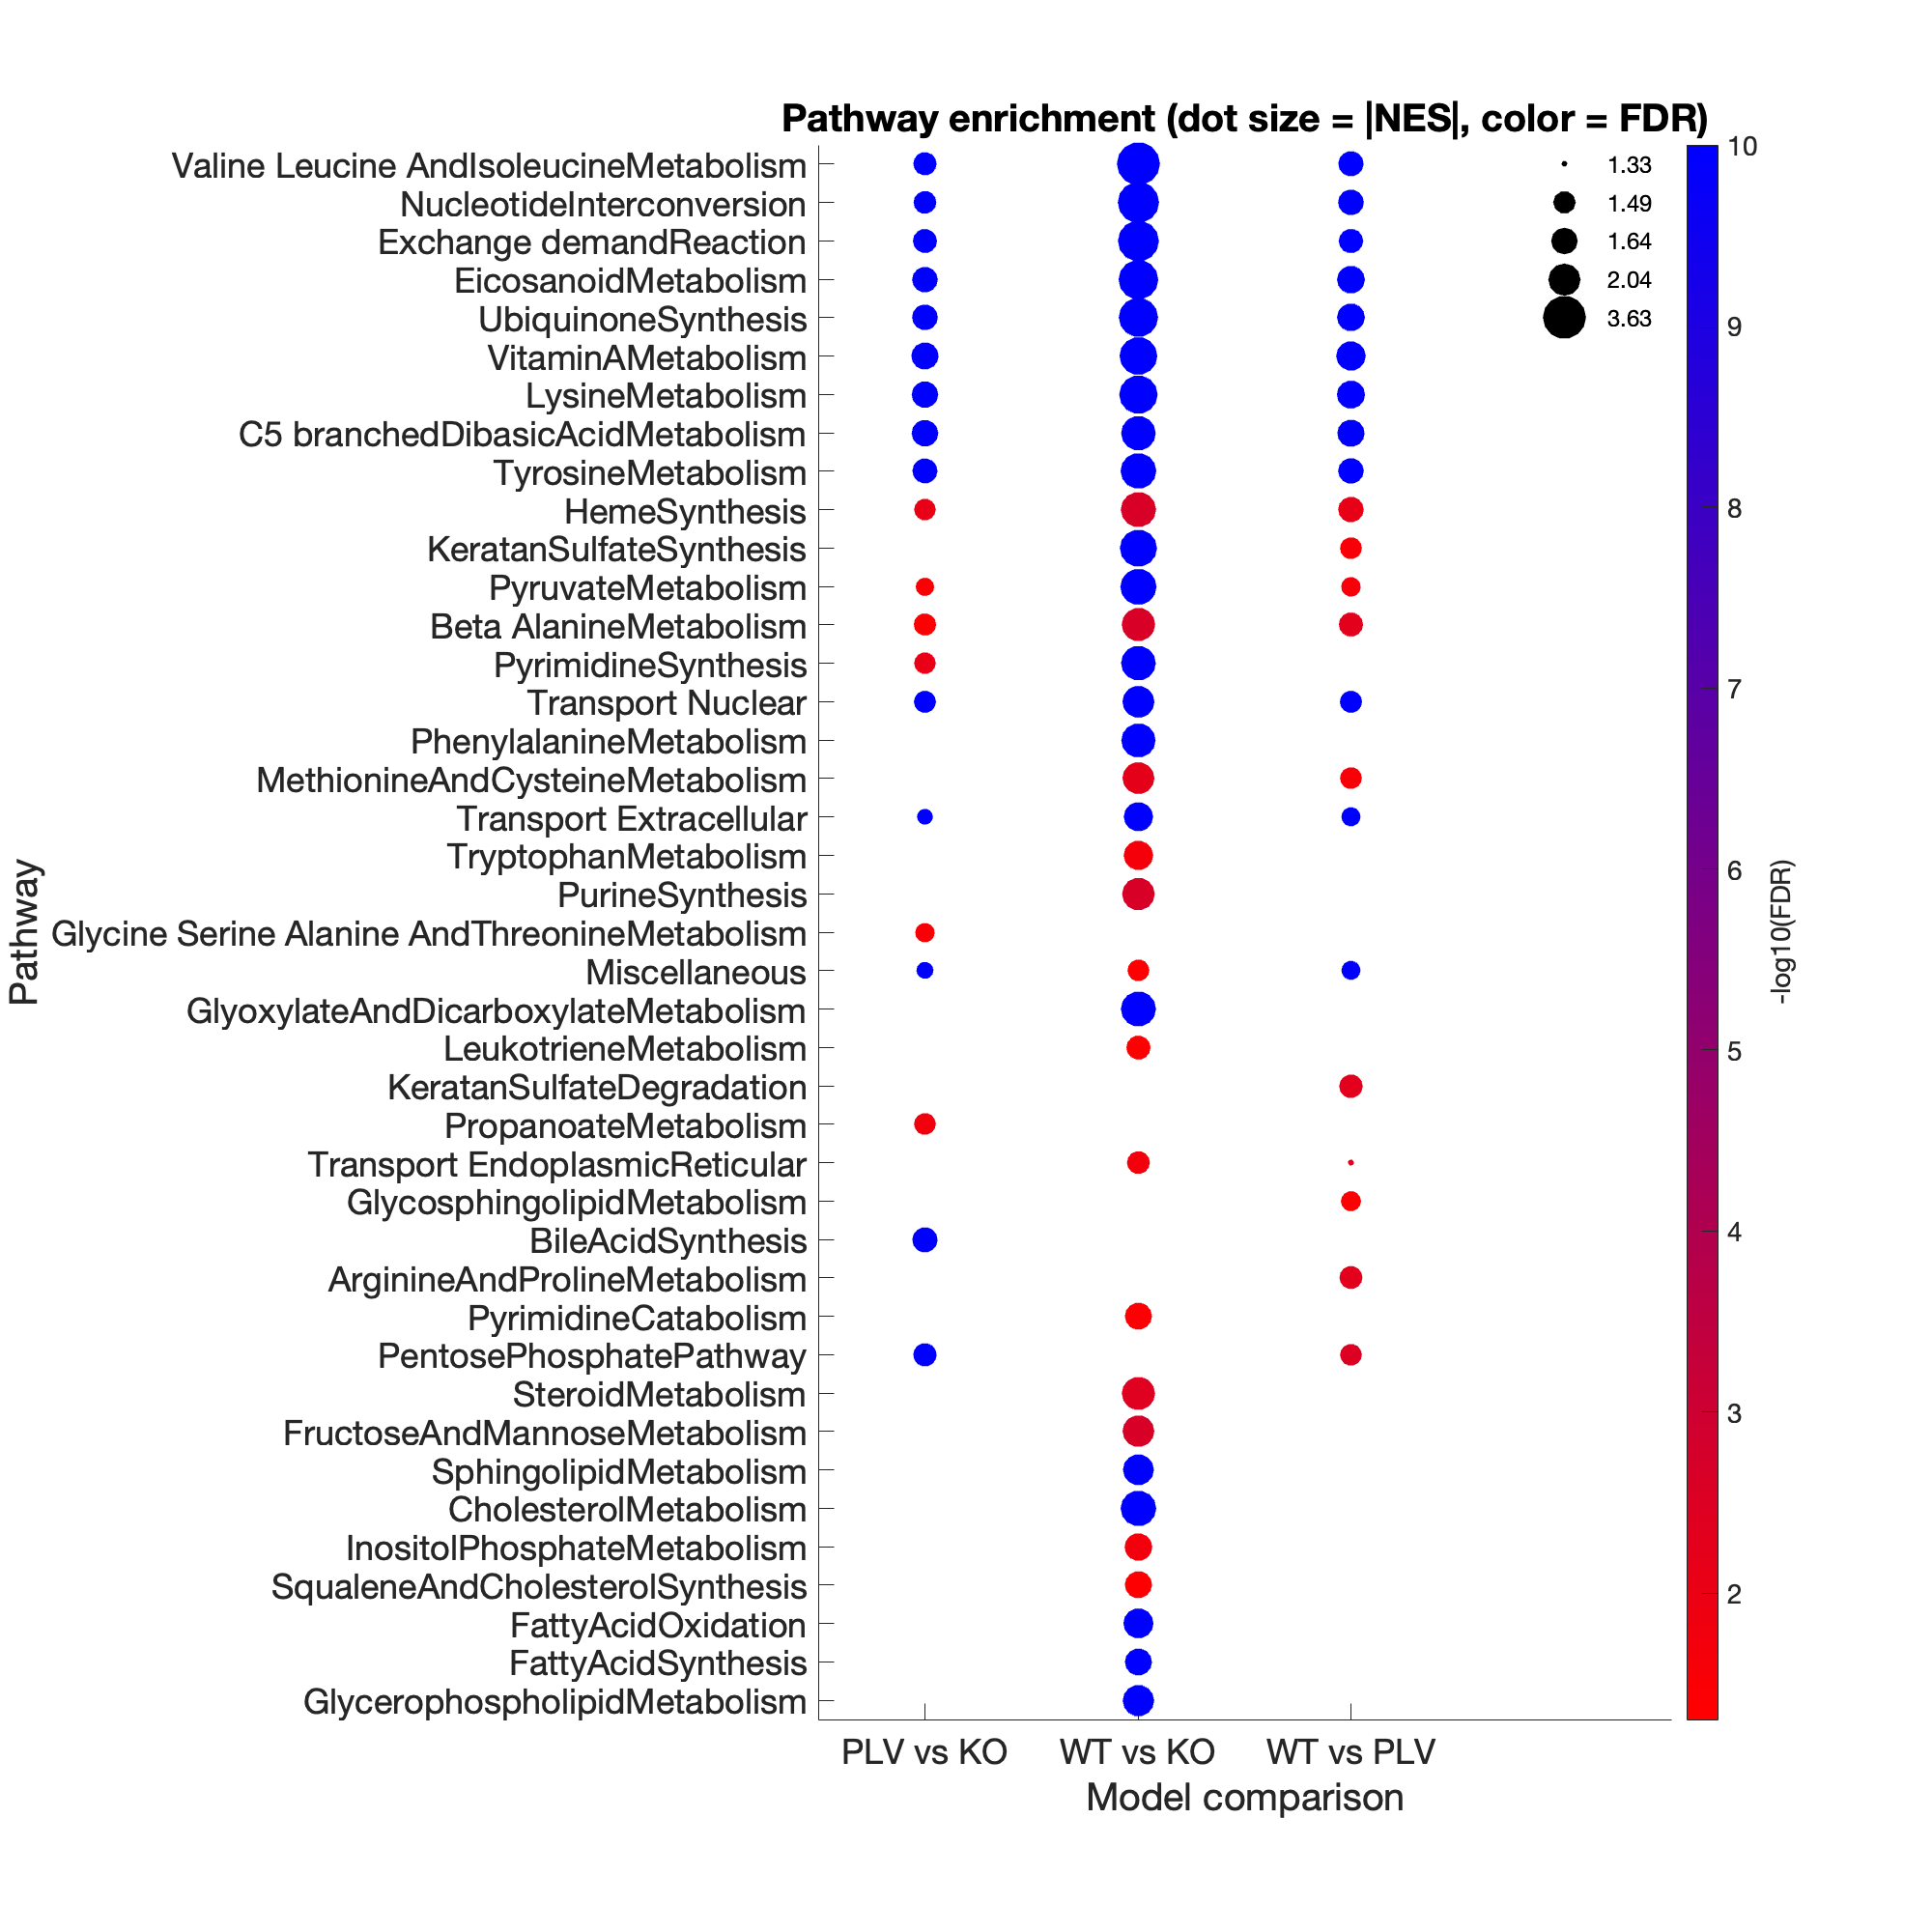

show_figure(plots.funct.fva_sim.enrich)

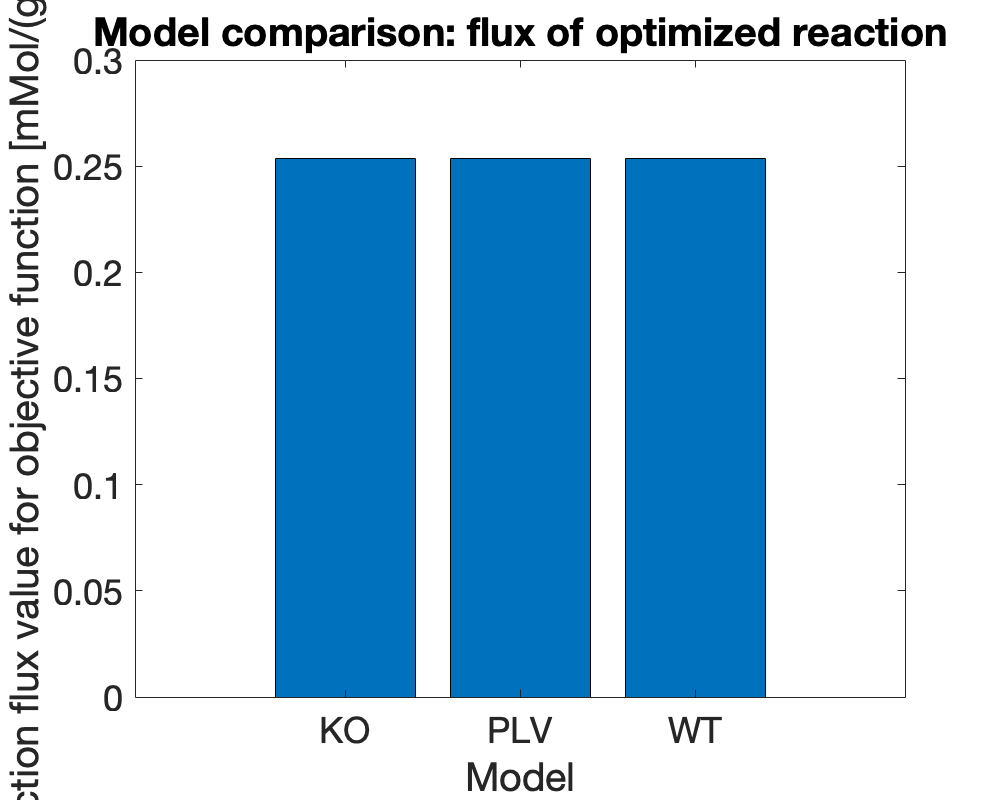

set(plots.funct.obj_value,'Position', [100 100 500 400]) % resize so it is comfortable to read the whole figure!
show_figure(plots.funct.obj_value)

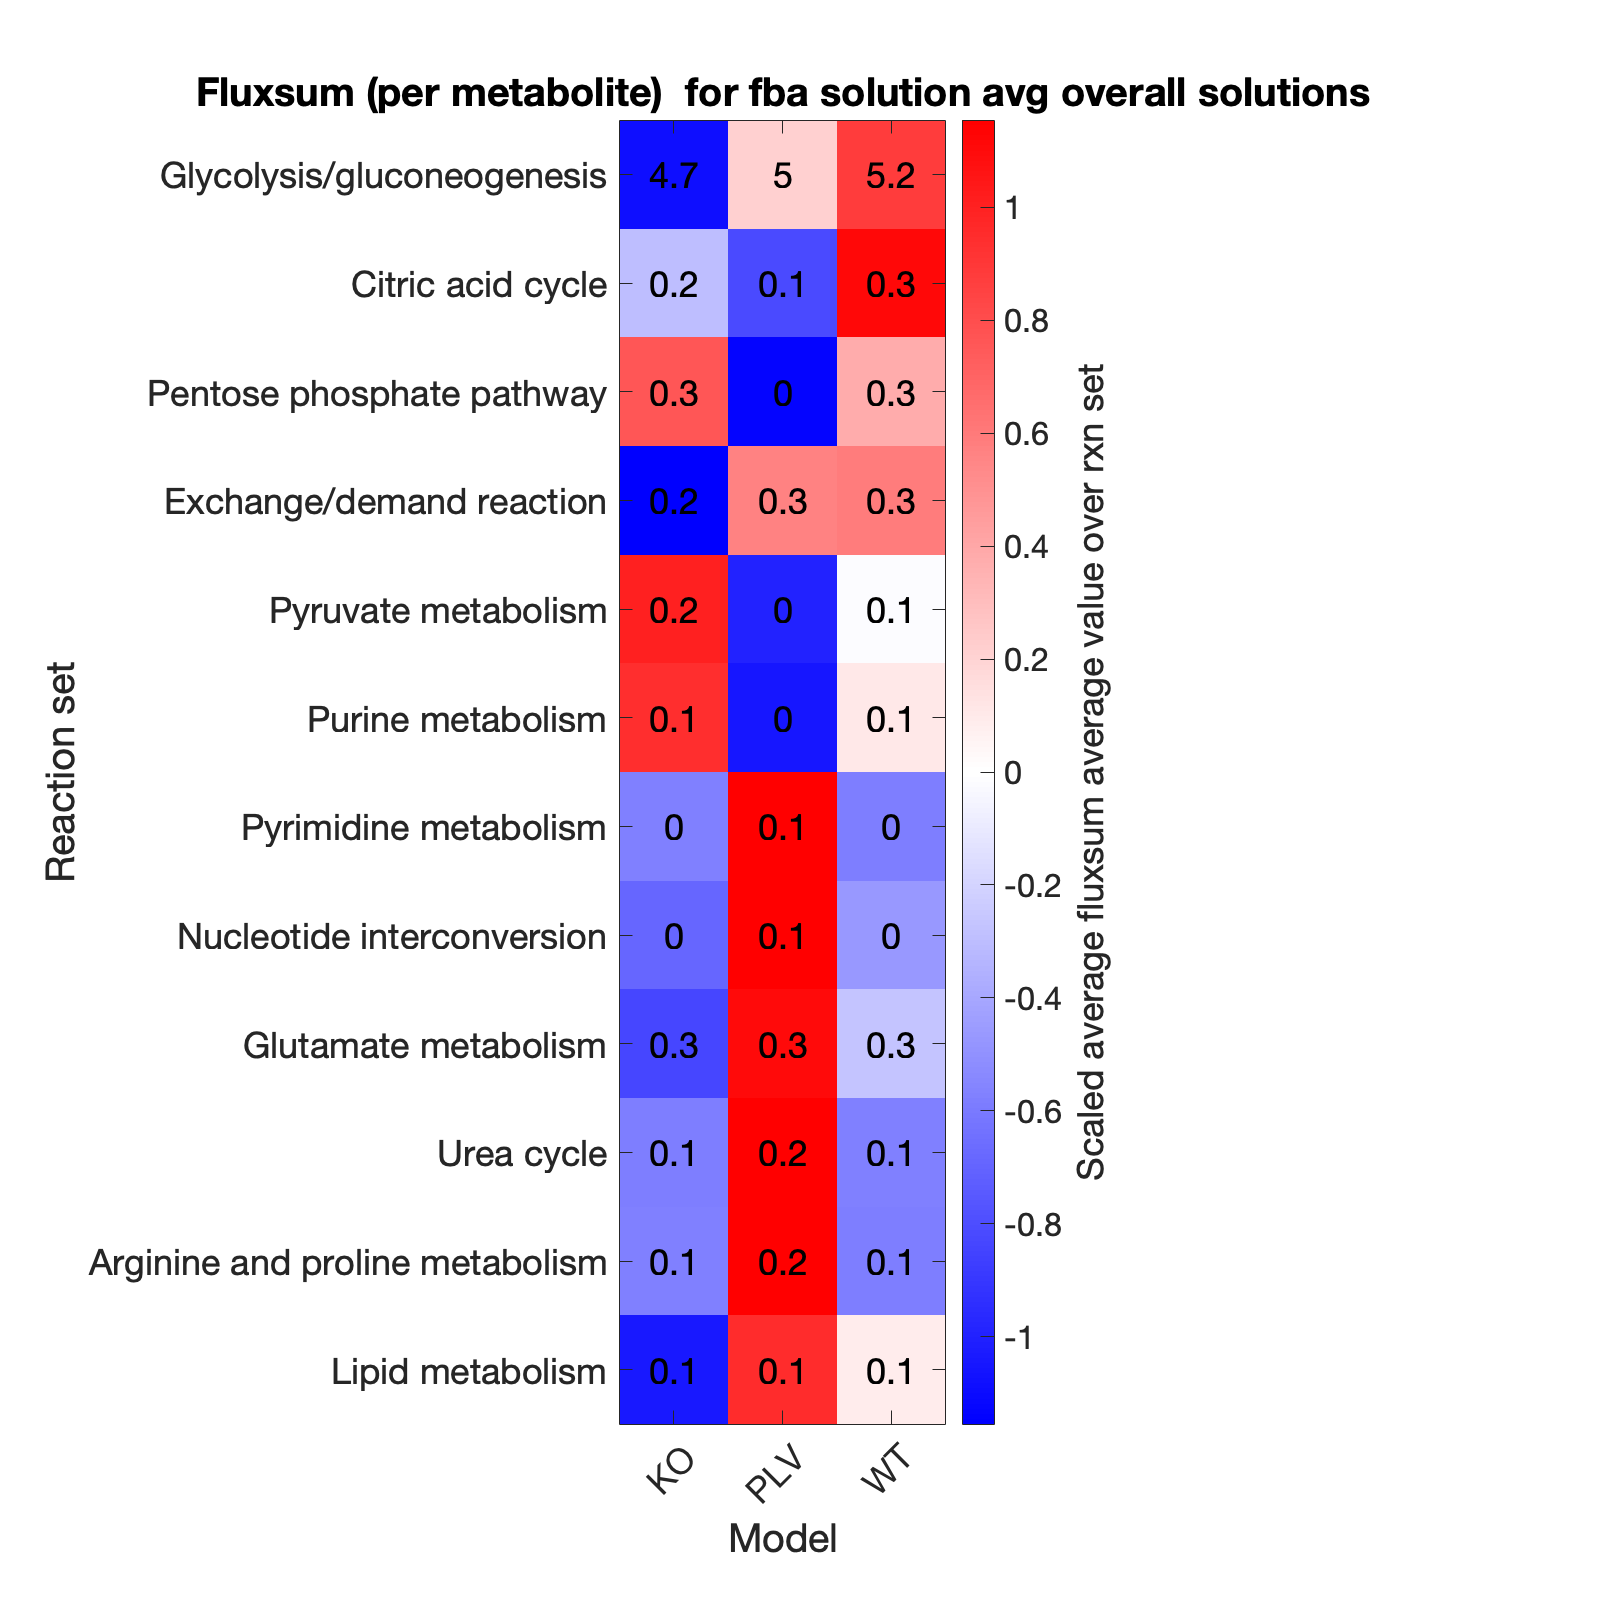

show_figure(plots.funct.fba.heatmap_mets_fluxsum)

show_figure(plots.funct.fba.heatmap_rxn_fluxsum)

[project,comparison_name] = modelsComparison(project,modelList, analysisID,...
                                            referenceModel,"modelsComparisonSampling",identifier);

modelsToTest = 1×4 string array
    "WT"    "KO"    "PLV"    "consistent_medium_constrained_model"


Transcripts will temporarily be removed to allow matching with the discretized data.
1258 of 1261 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1253 of 1256 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1274 of 1277 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1264 of 1267 genes of the model matched


plots = project.comparisons.(comparison_name).plots

plots = struct with fields:
      struct: [1×1 struct]
       funct: [1×1 struct]
    sampling: [1×1 struct]


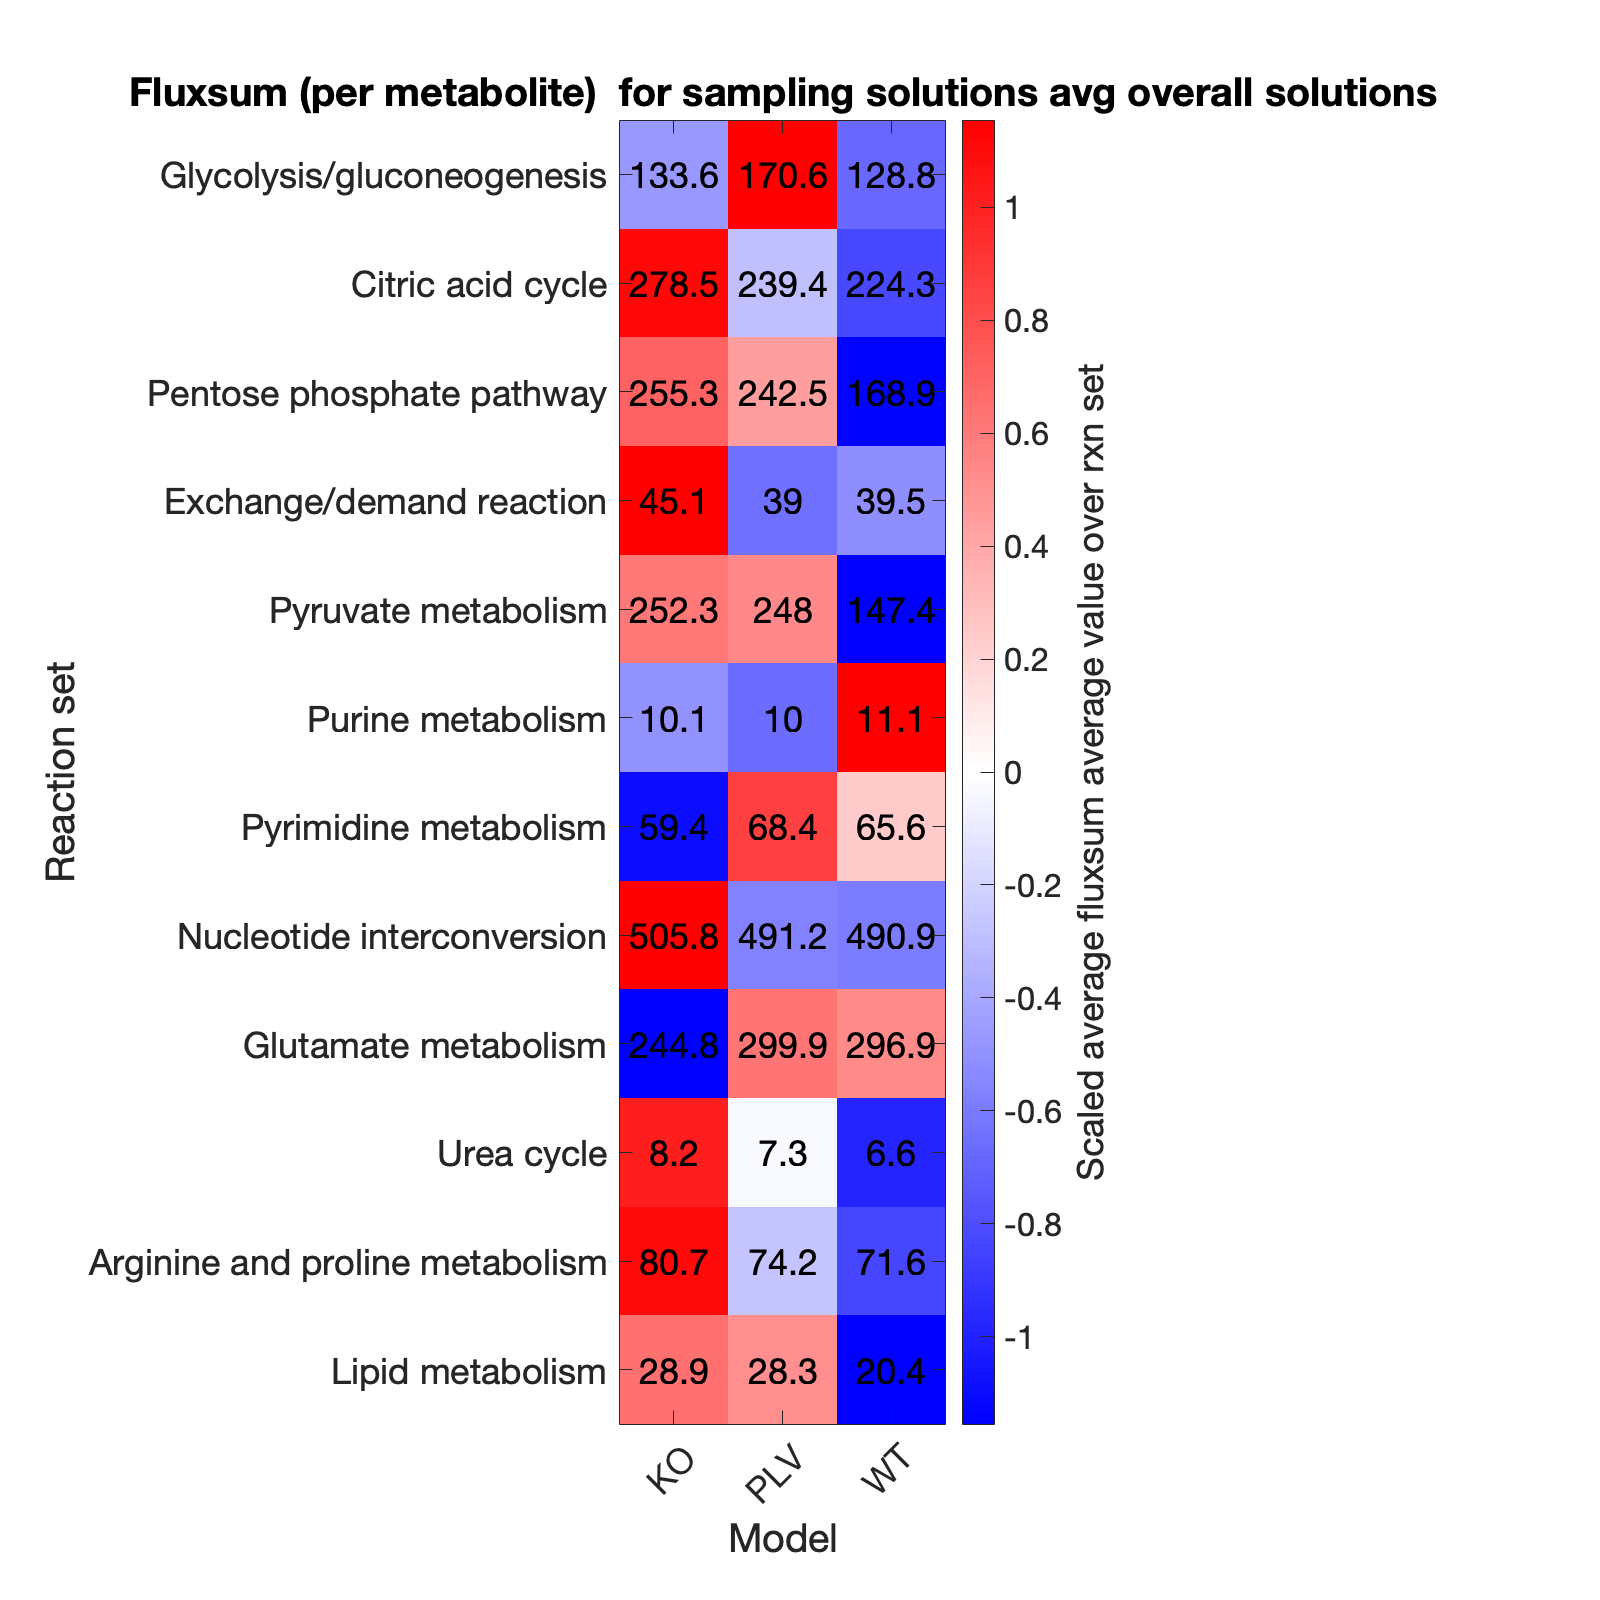

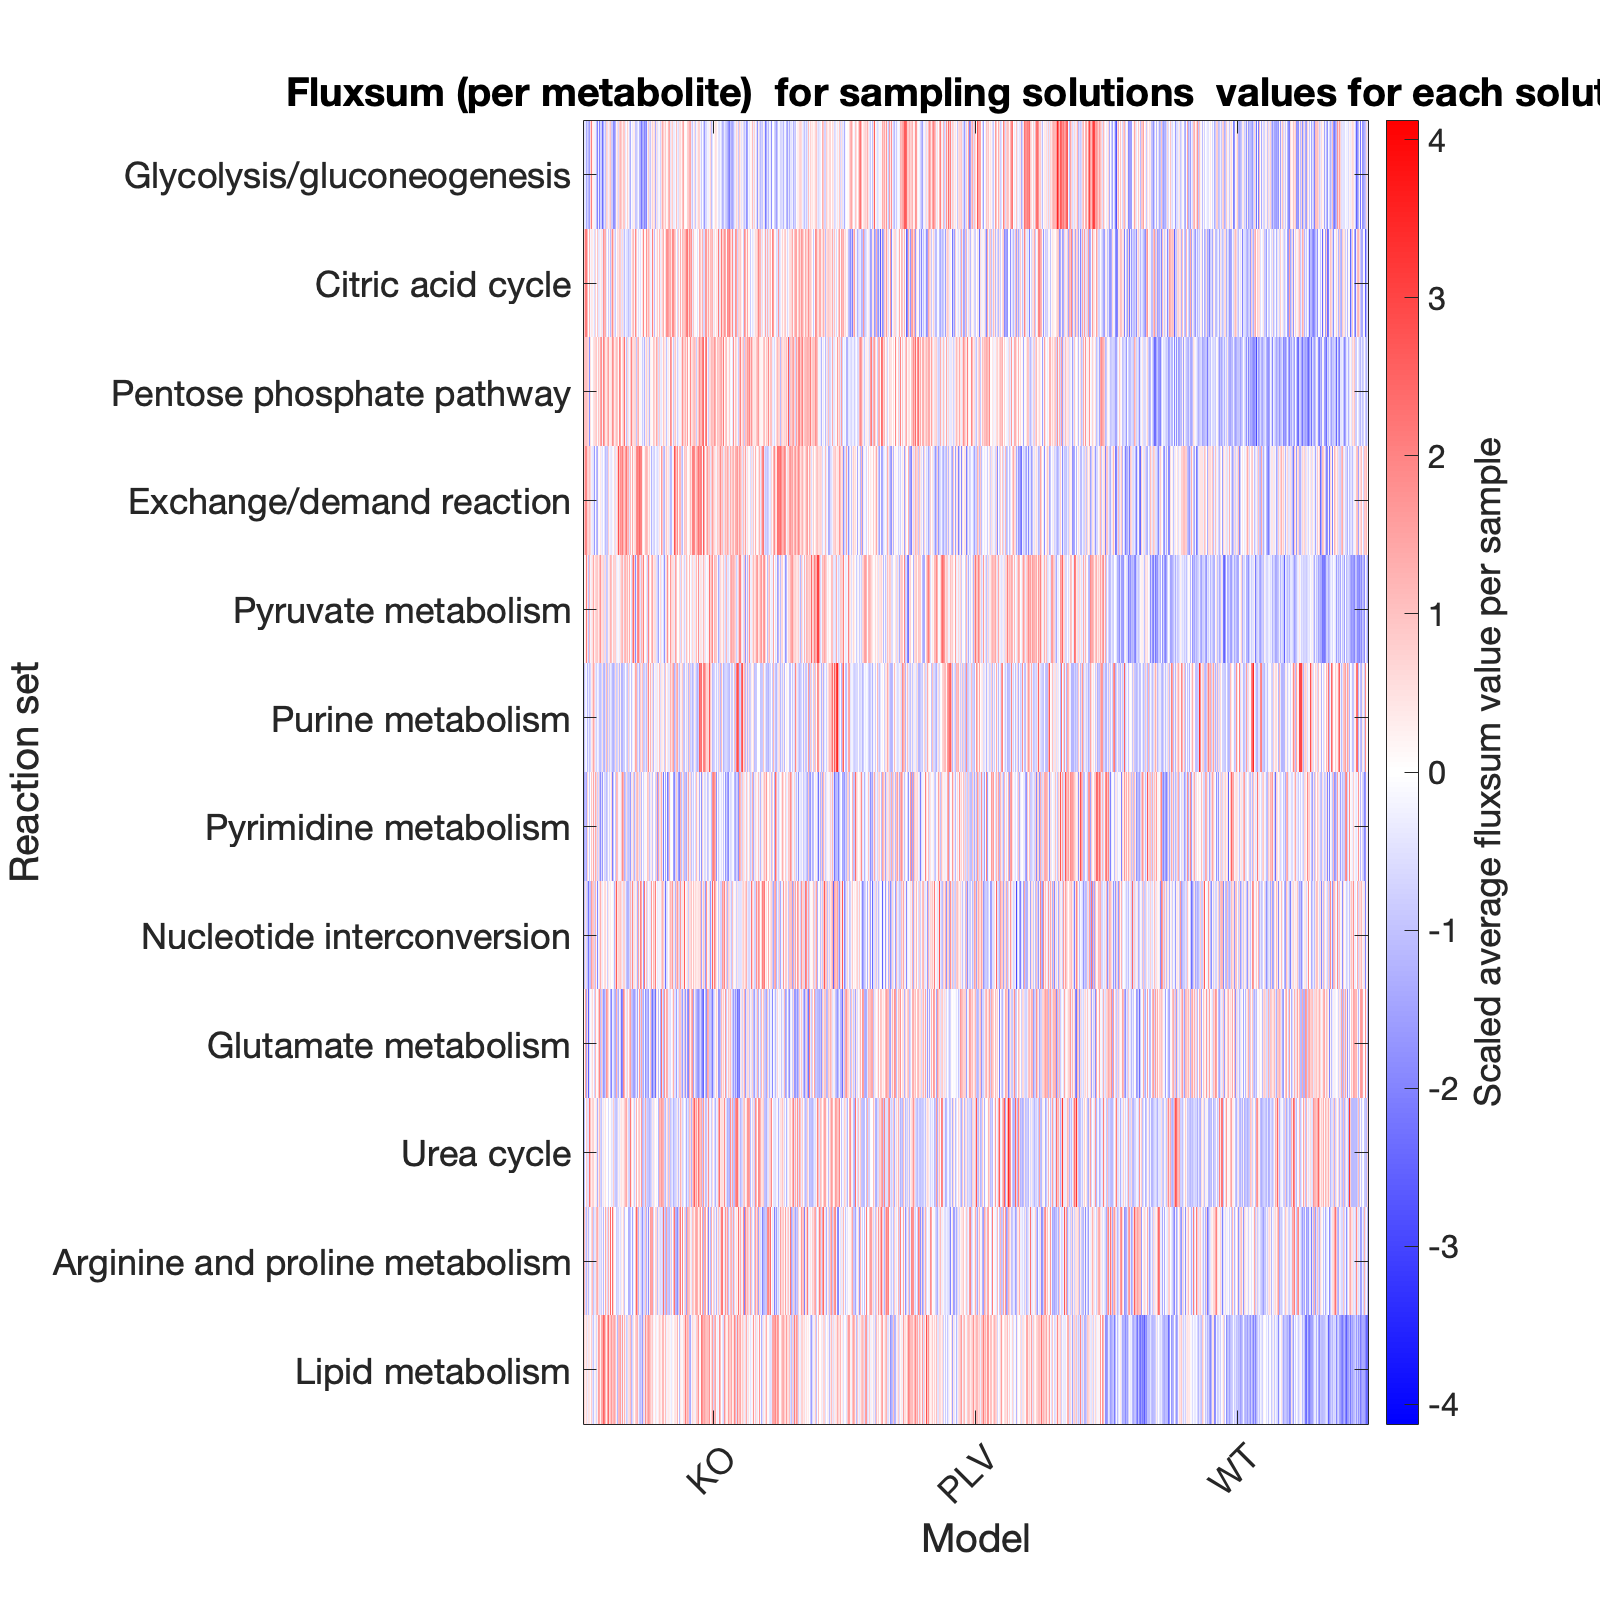

show_figure(plots.sampling.heatmap_mets_fluxsum);show_figure(plots.sampling.heatmap_mets_fluxsum_samples);

show_figure(plots.sampling.heatmap_mets_fluxsum_samples);

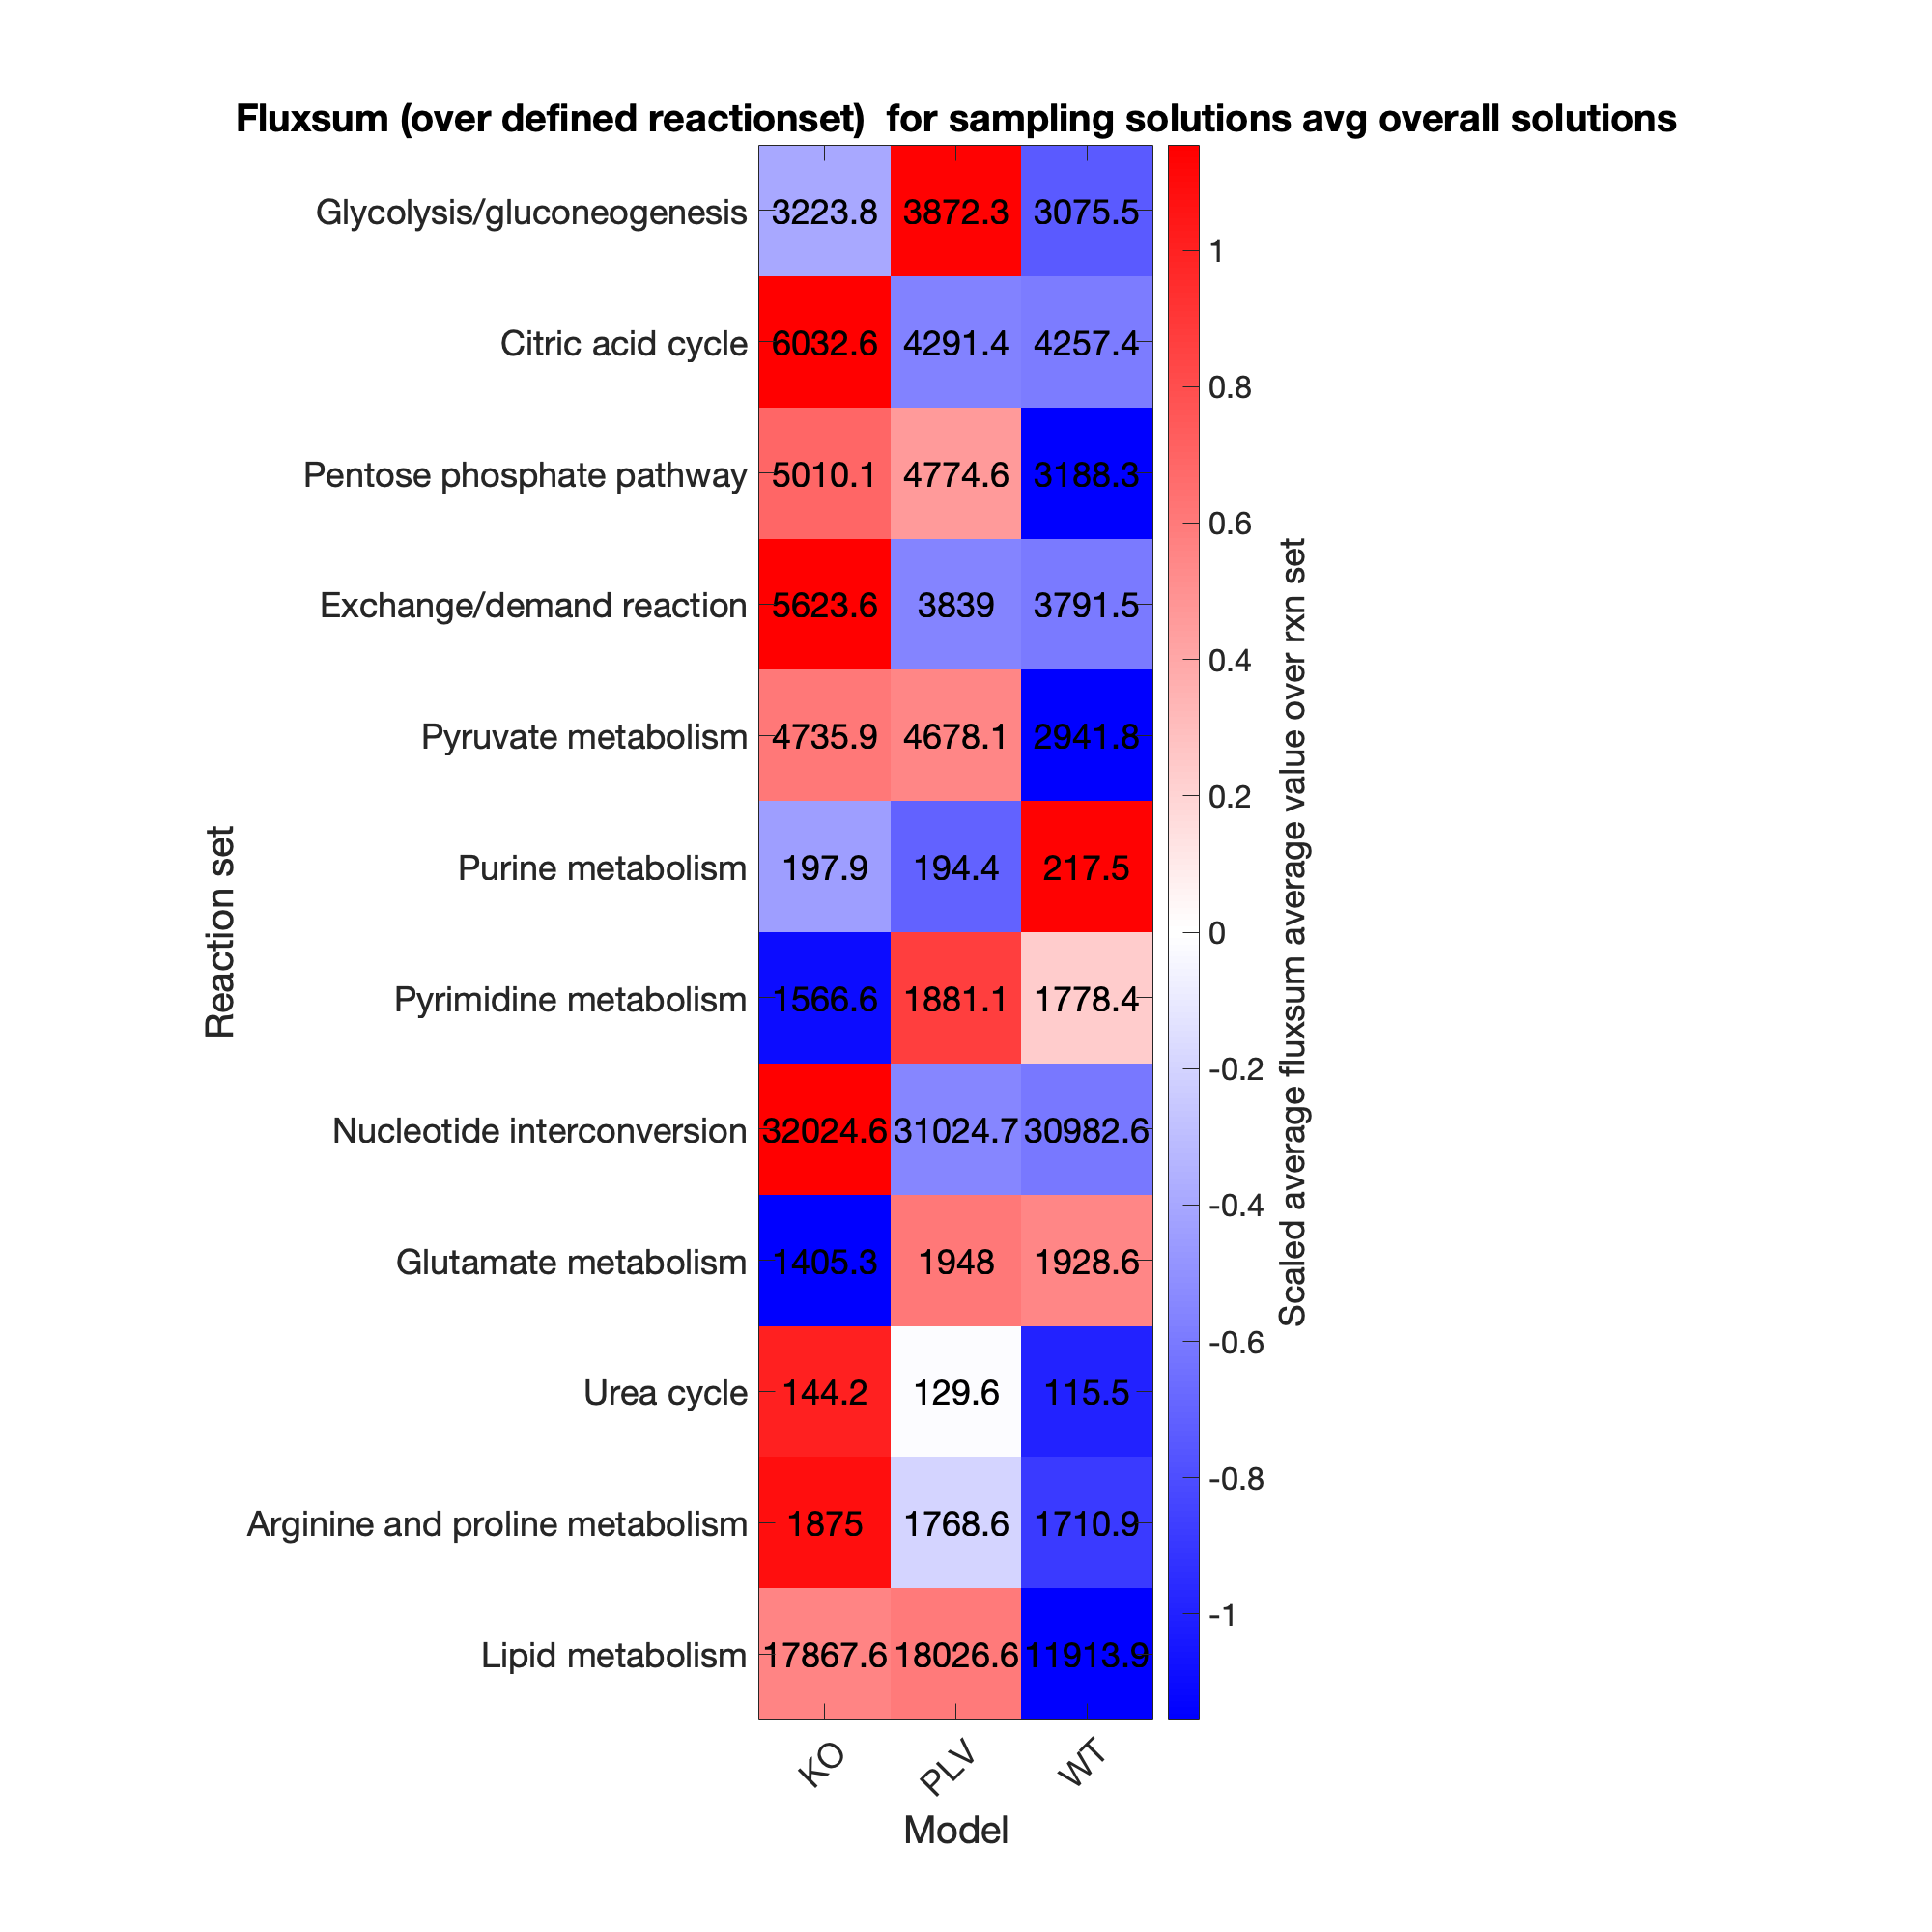

set(plots.sampling.heatmap_rxn_fluxsum,'Position',[100 100 1000 1000])
show_figure(plots.sampling.heatmap_rxn_fluxsum);

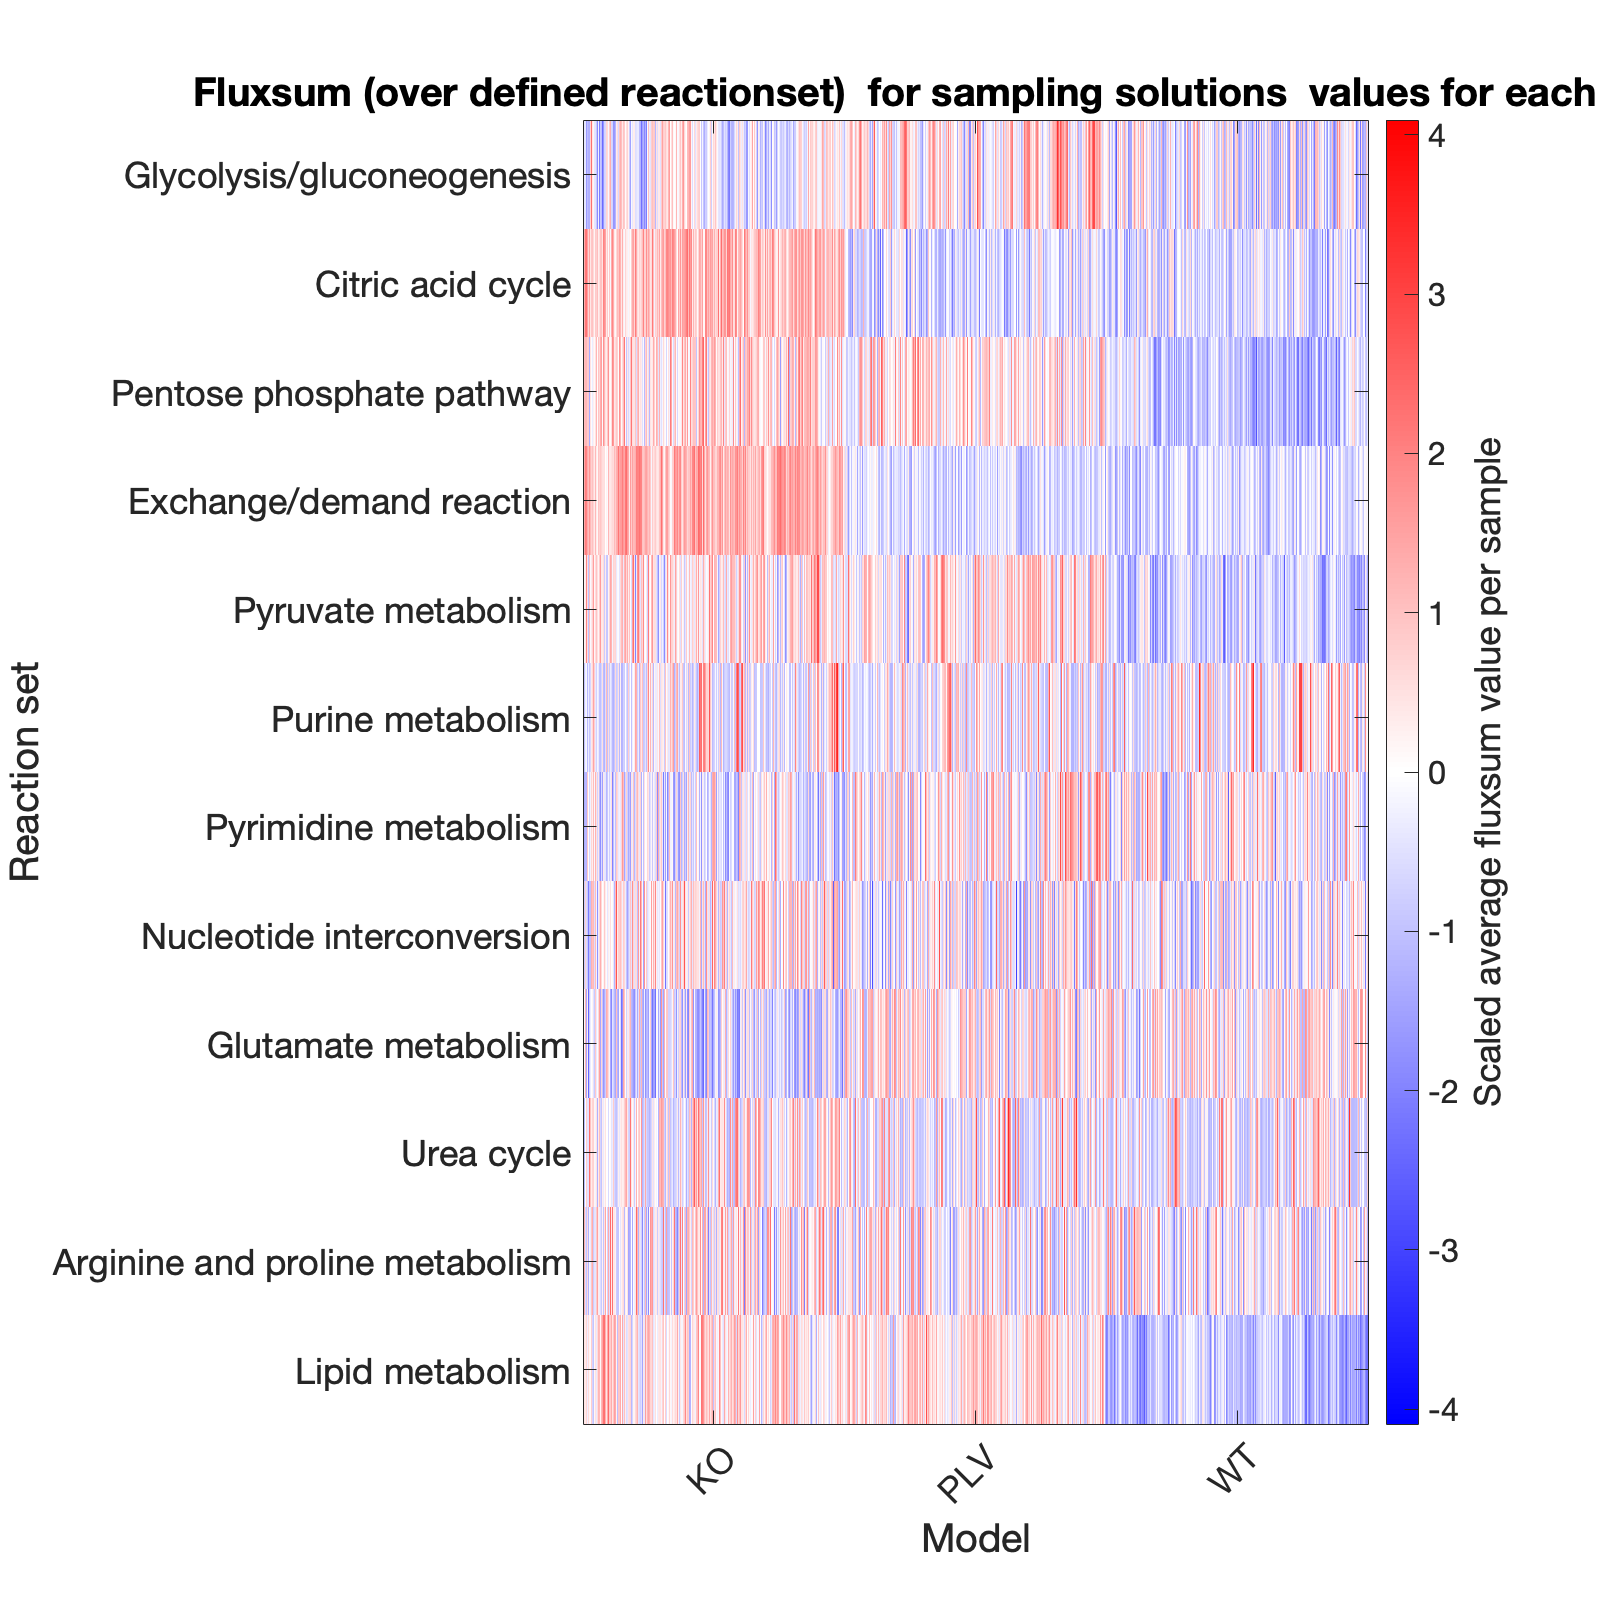

show_figure(plots.sampling.heatmap_rxn_fluxsum_samples);

show_figure(plots.sampling.heatmap_mets_fluxsum);

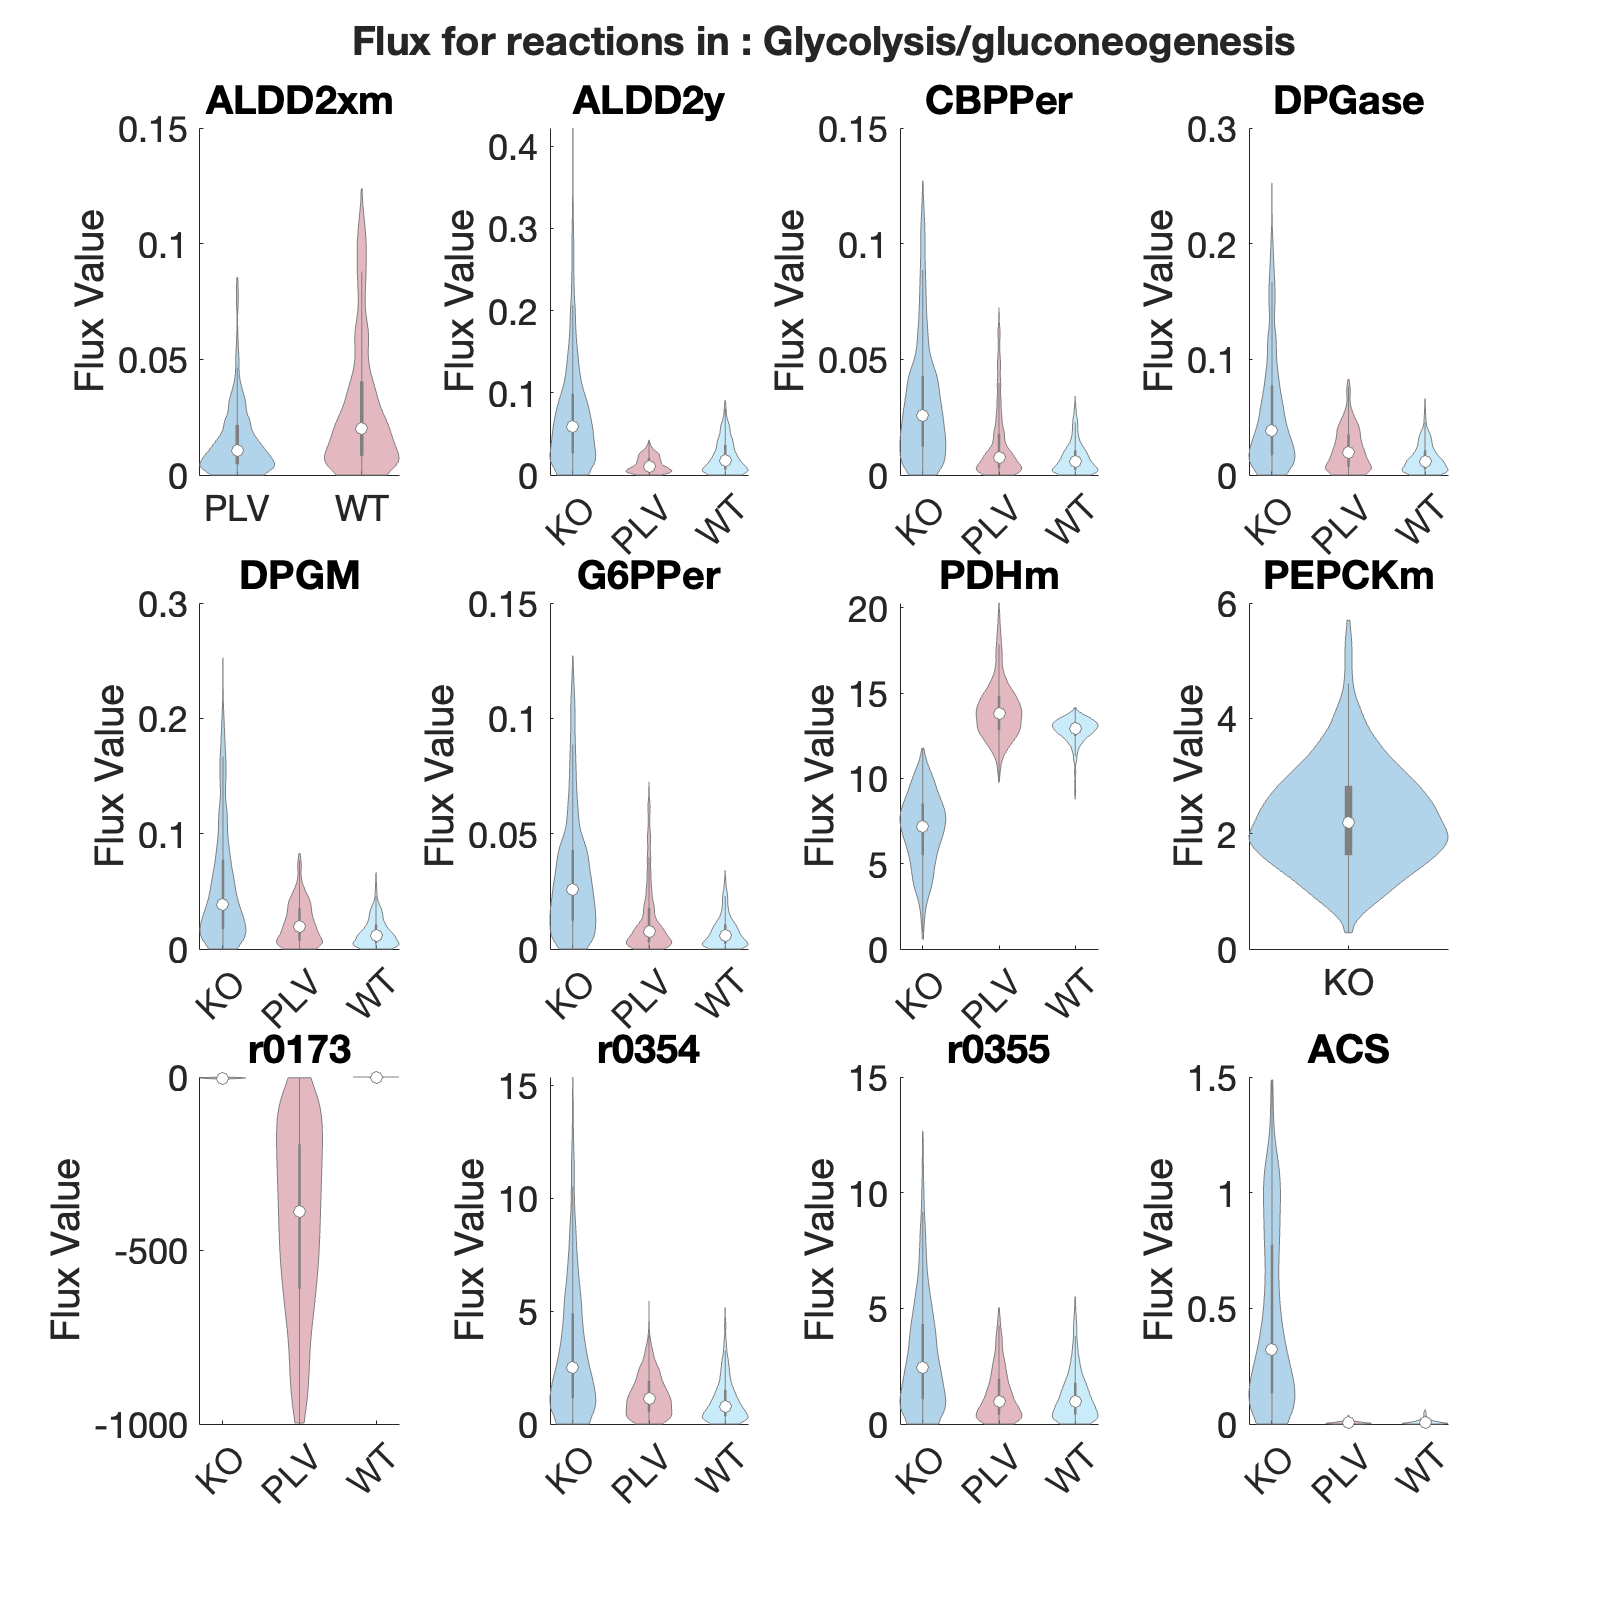

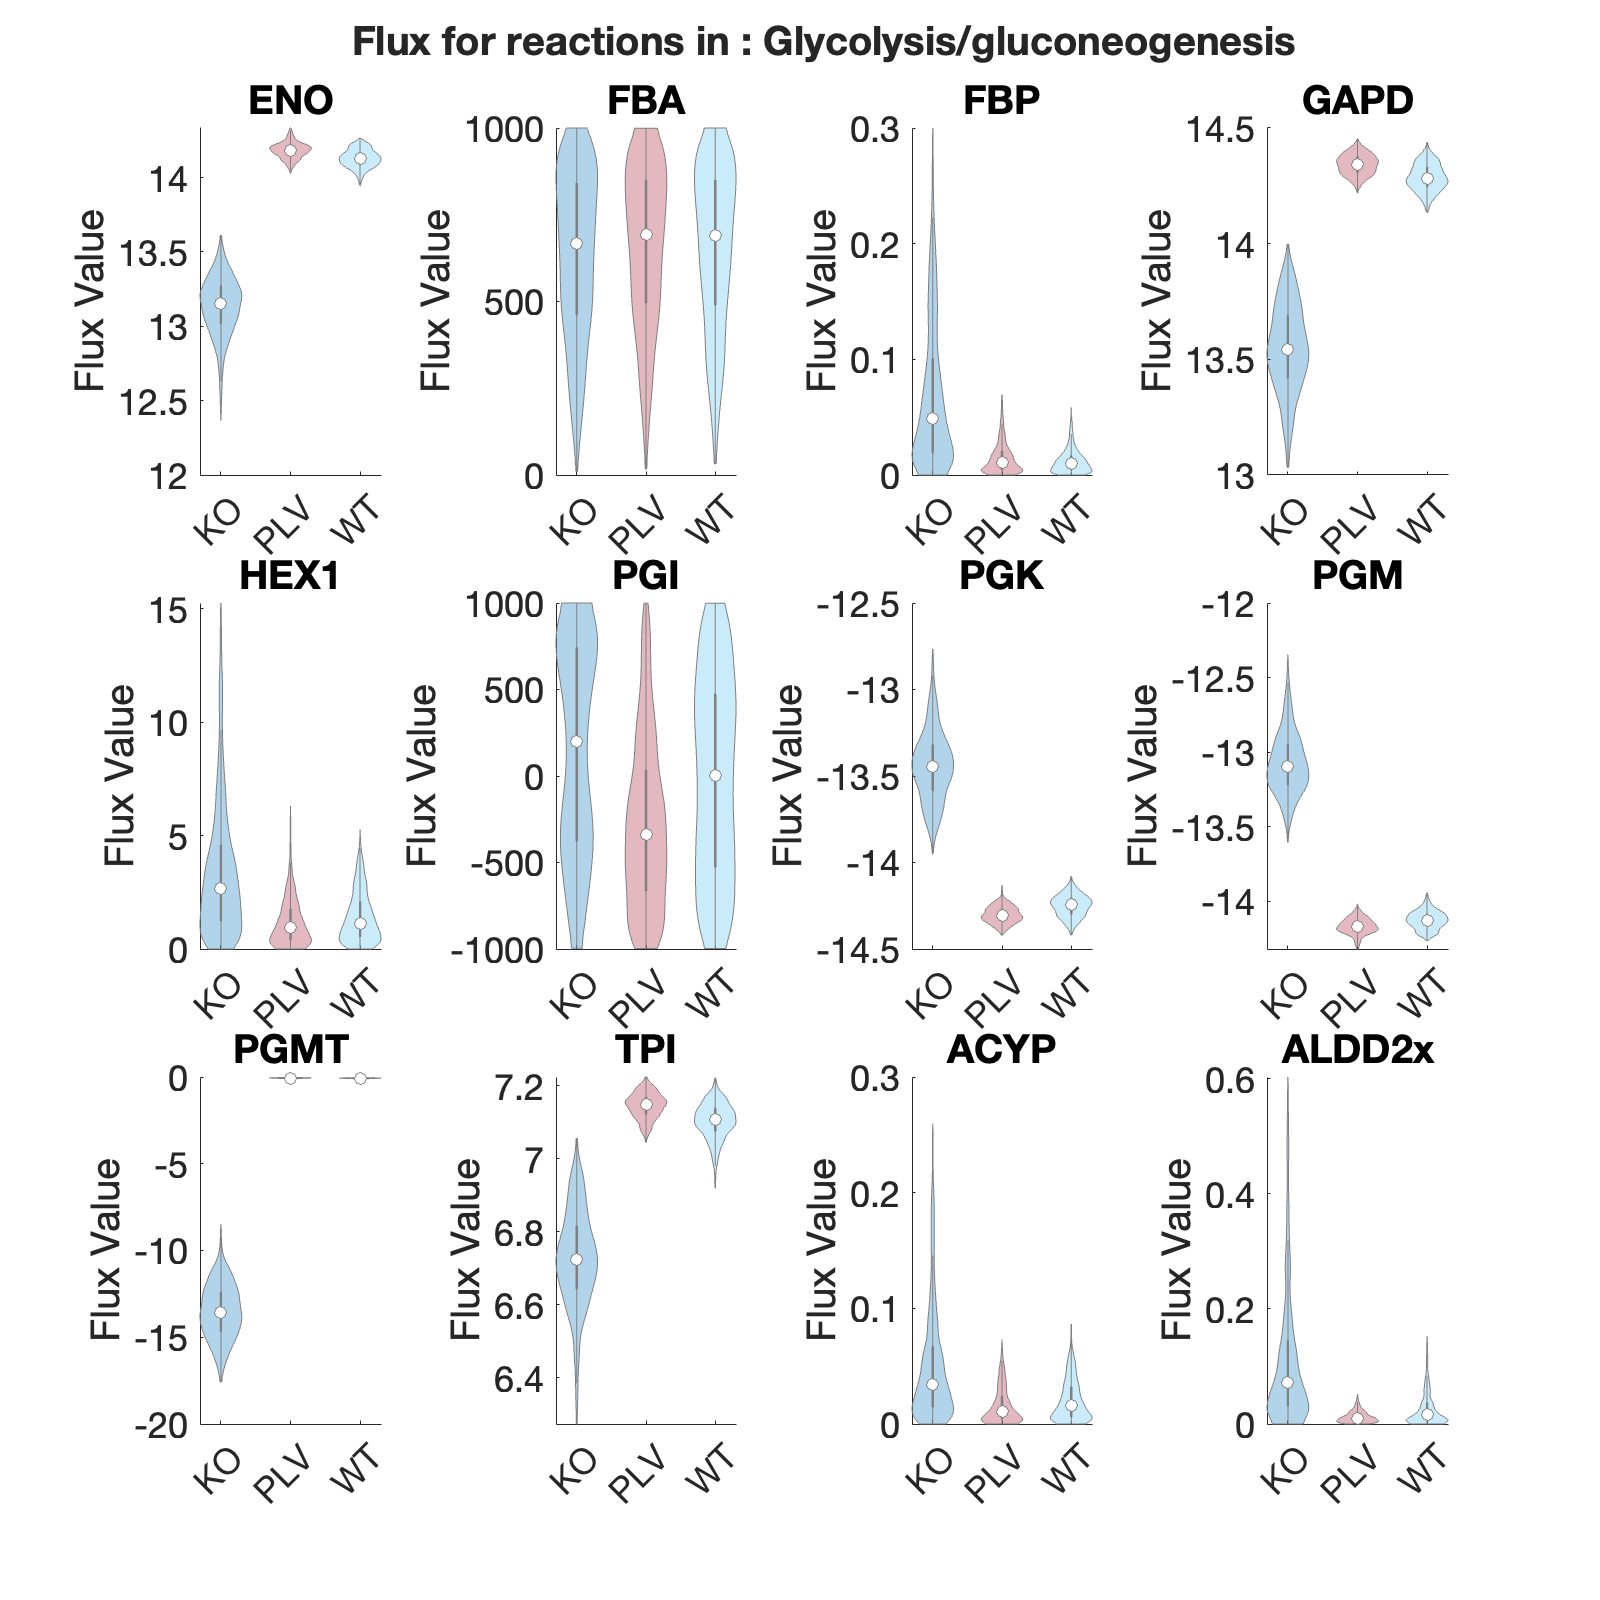

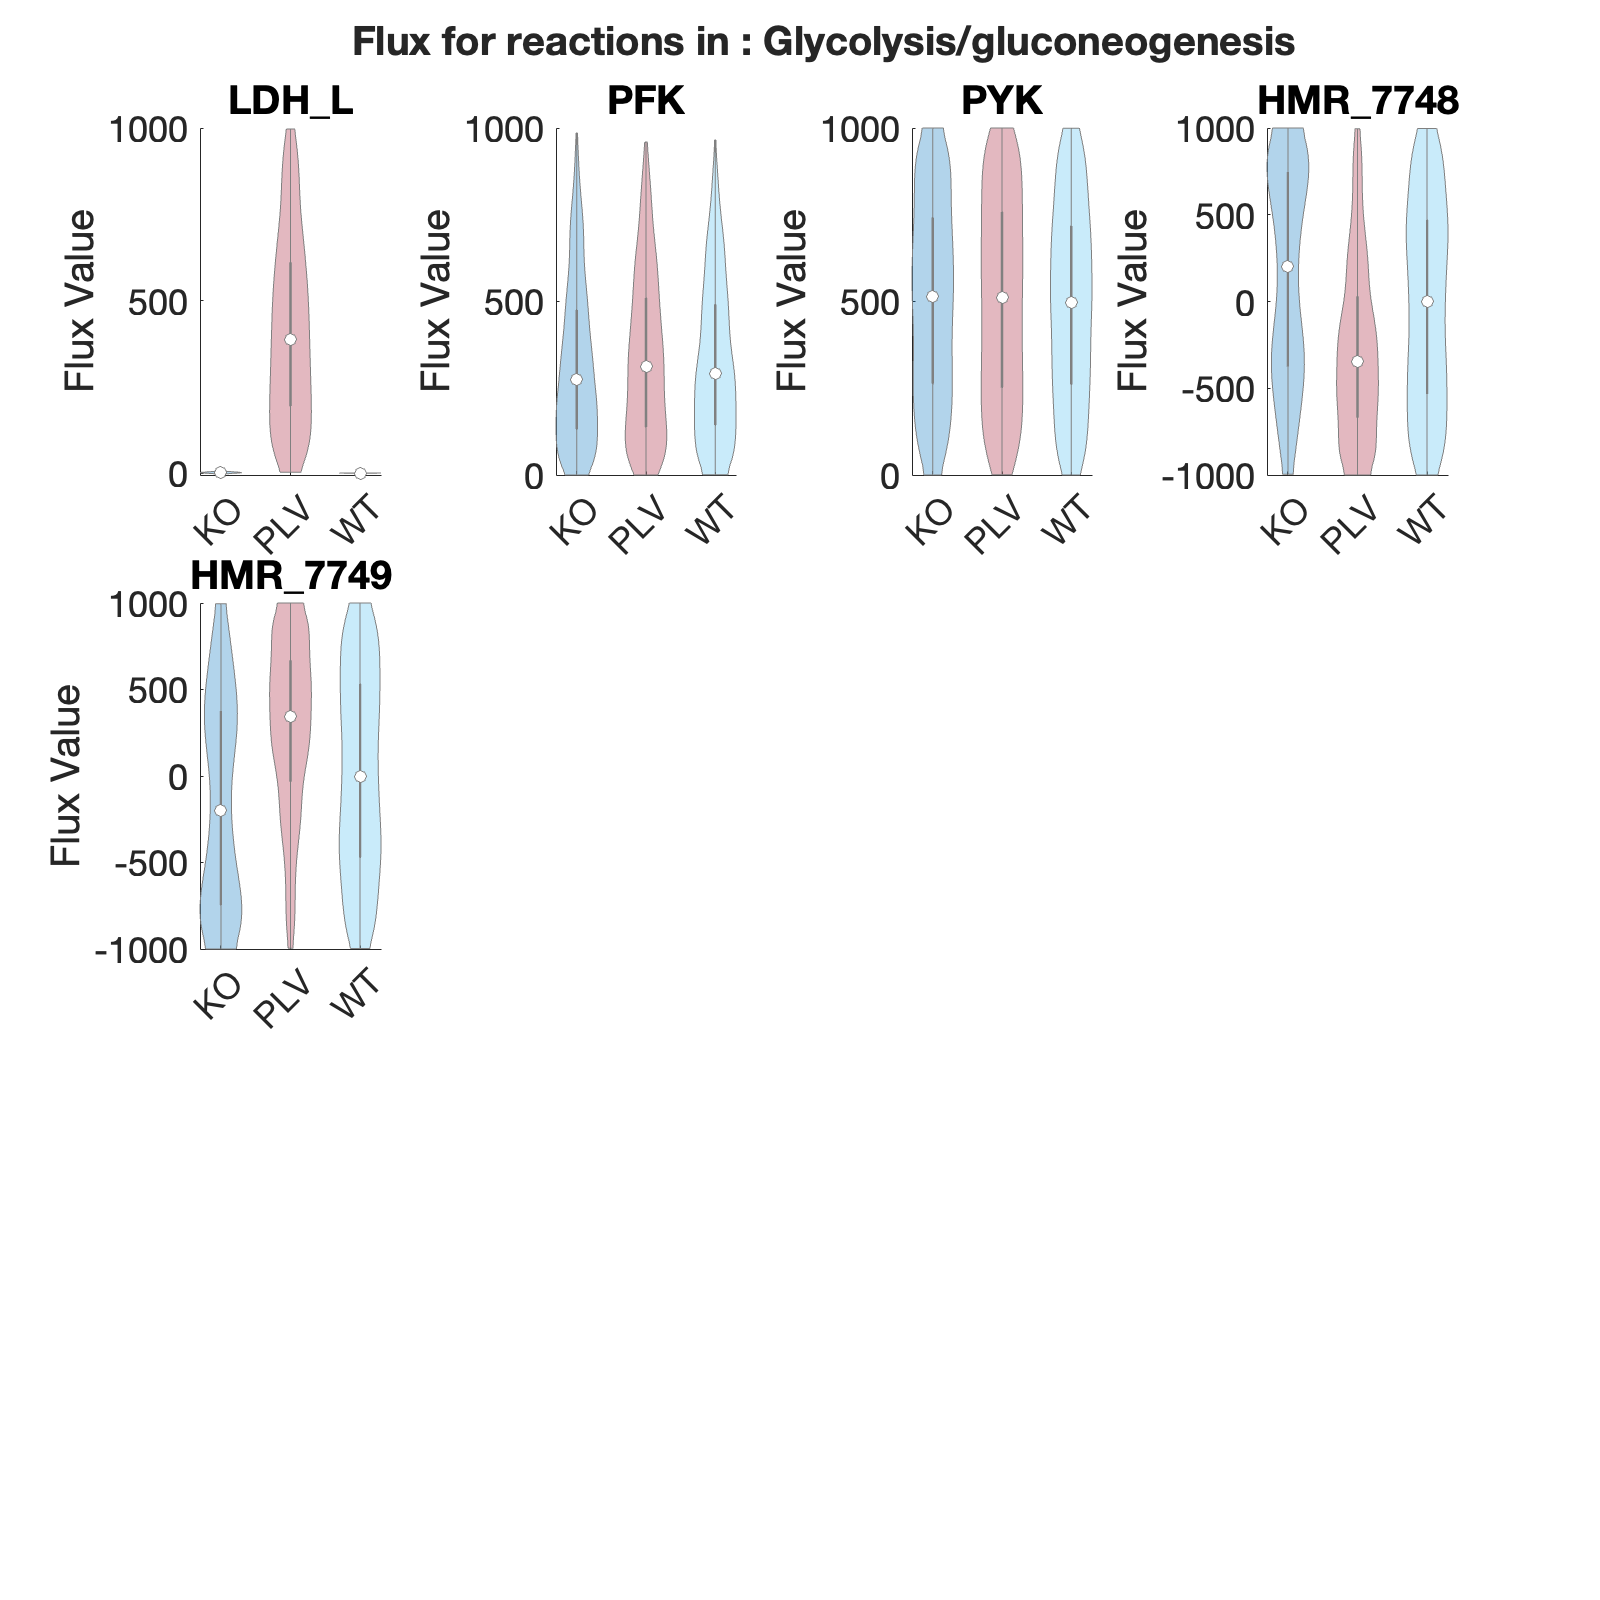

show_figure(plots.sampling.violing_flux_Glycolysisgluconeogenesis.fig1); show_figure(plots.sampling.violing_flux_Glycolysisgluconeogenesis.fig2);show_figure(plots.sampling.violing_flux_Glycolysisgluconeogenesis.fig3)

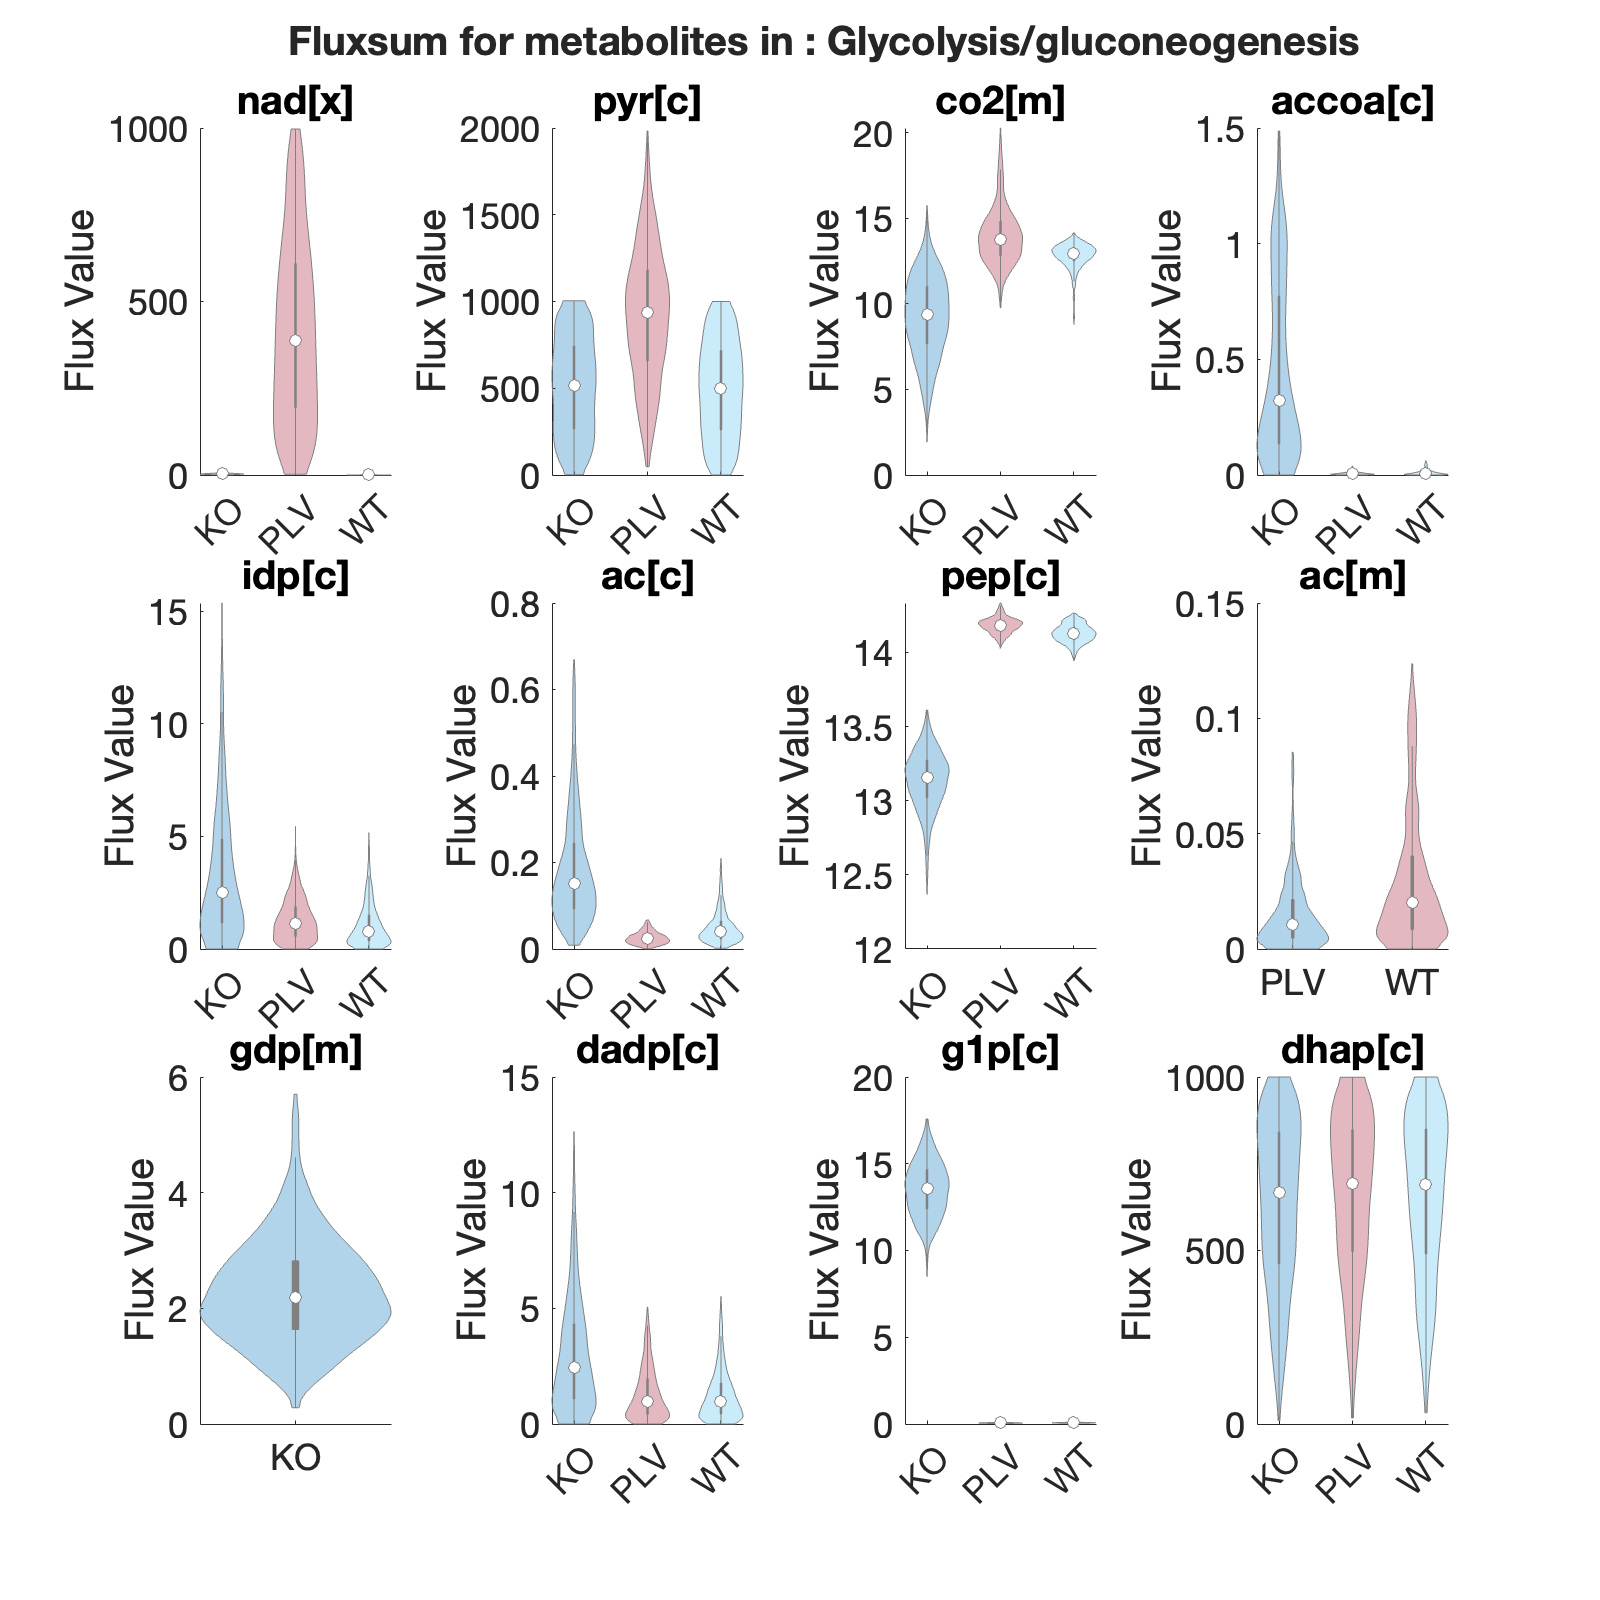

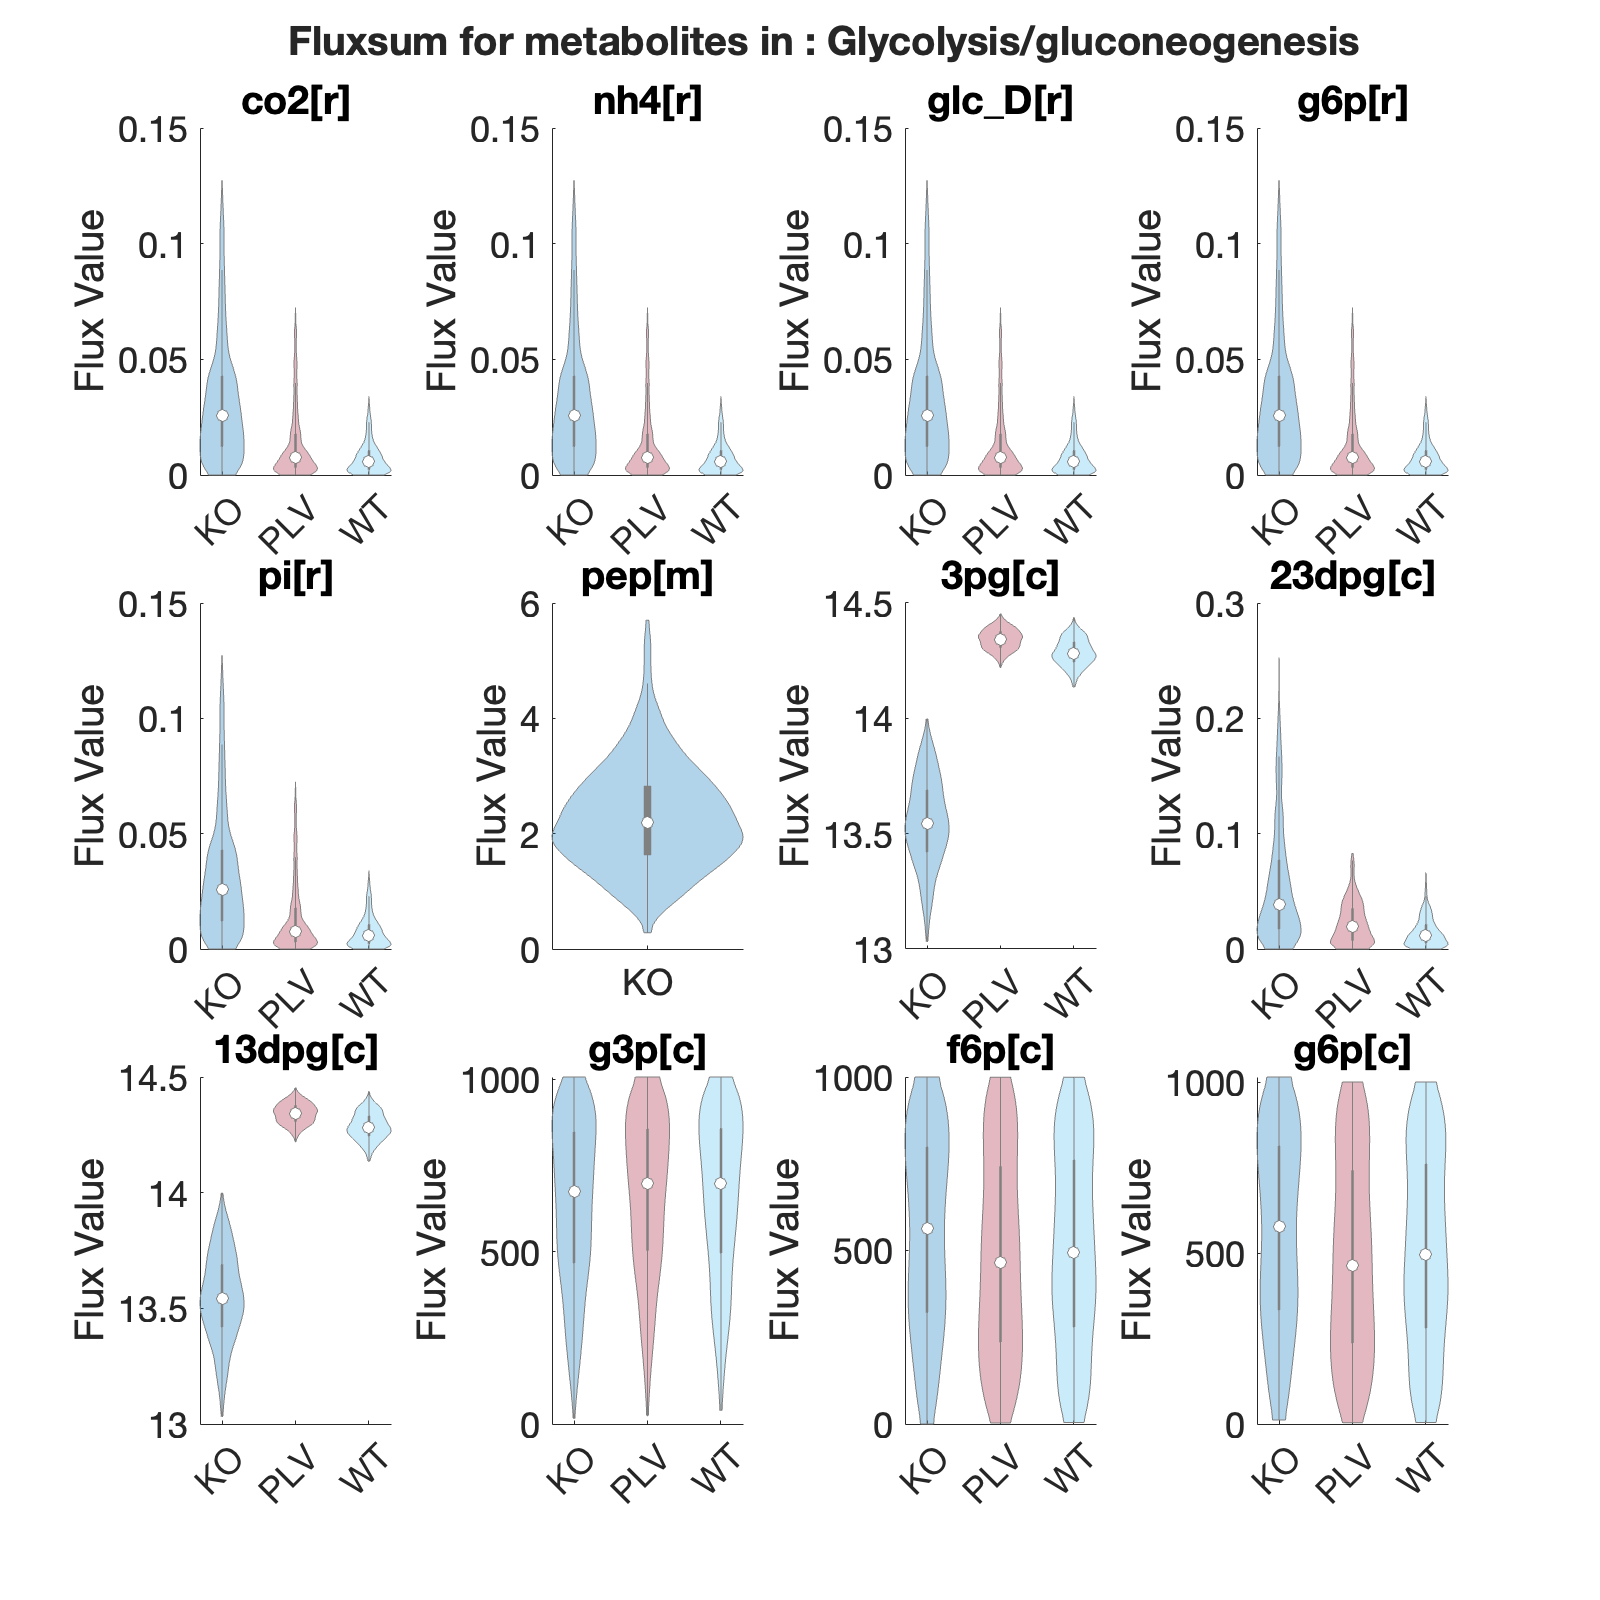

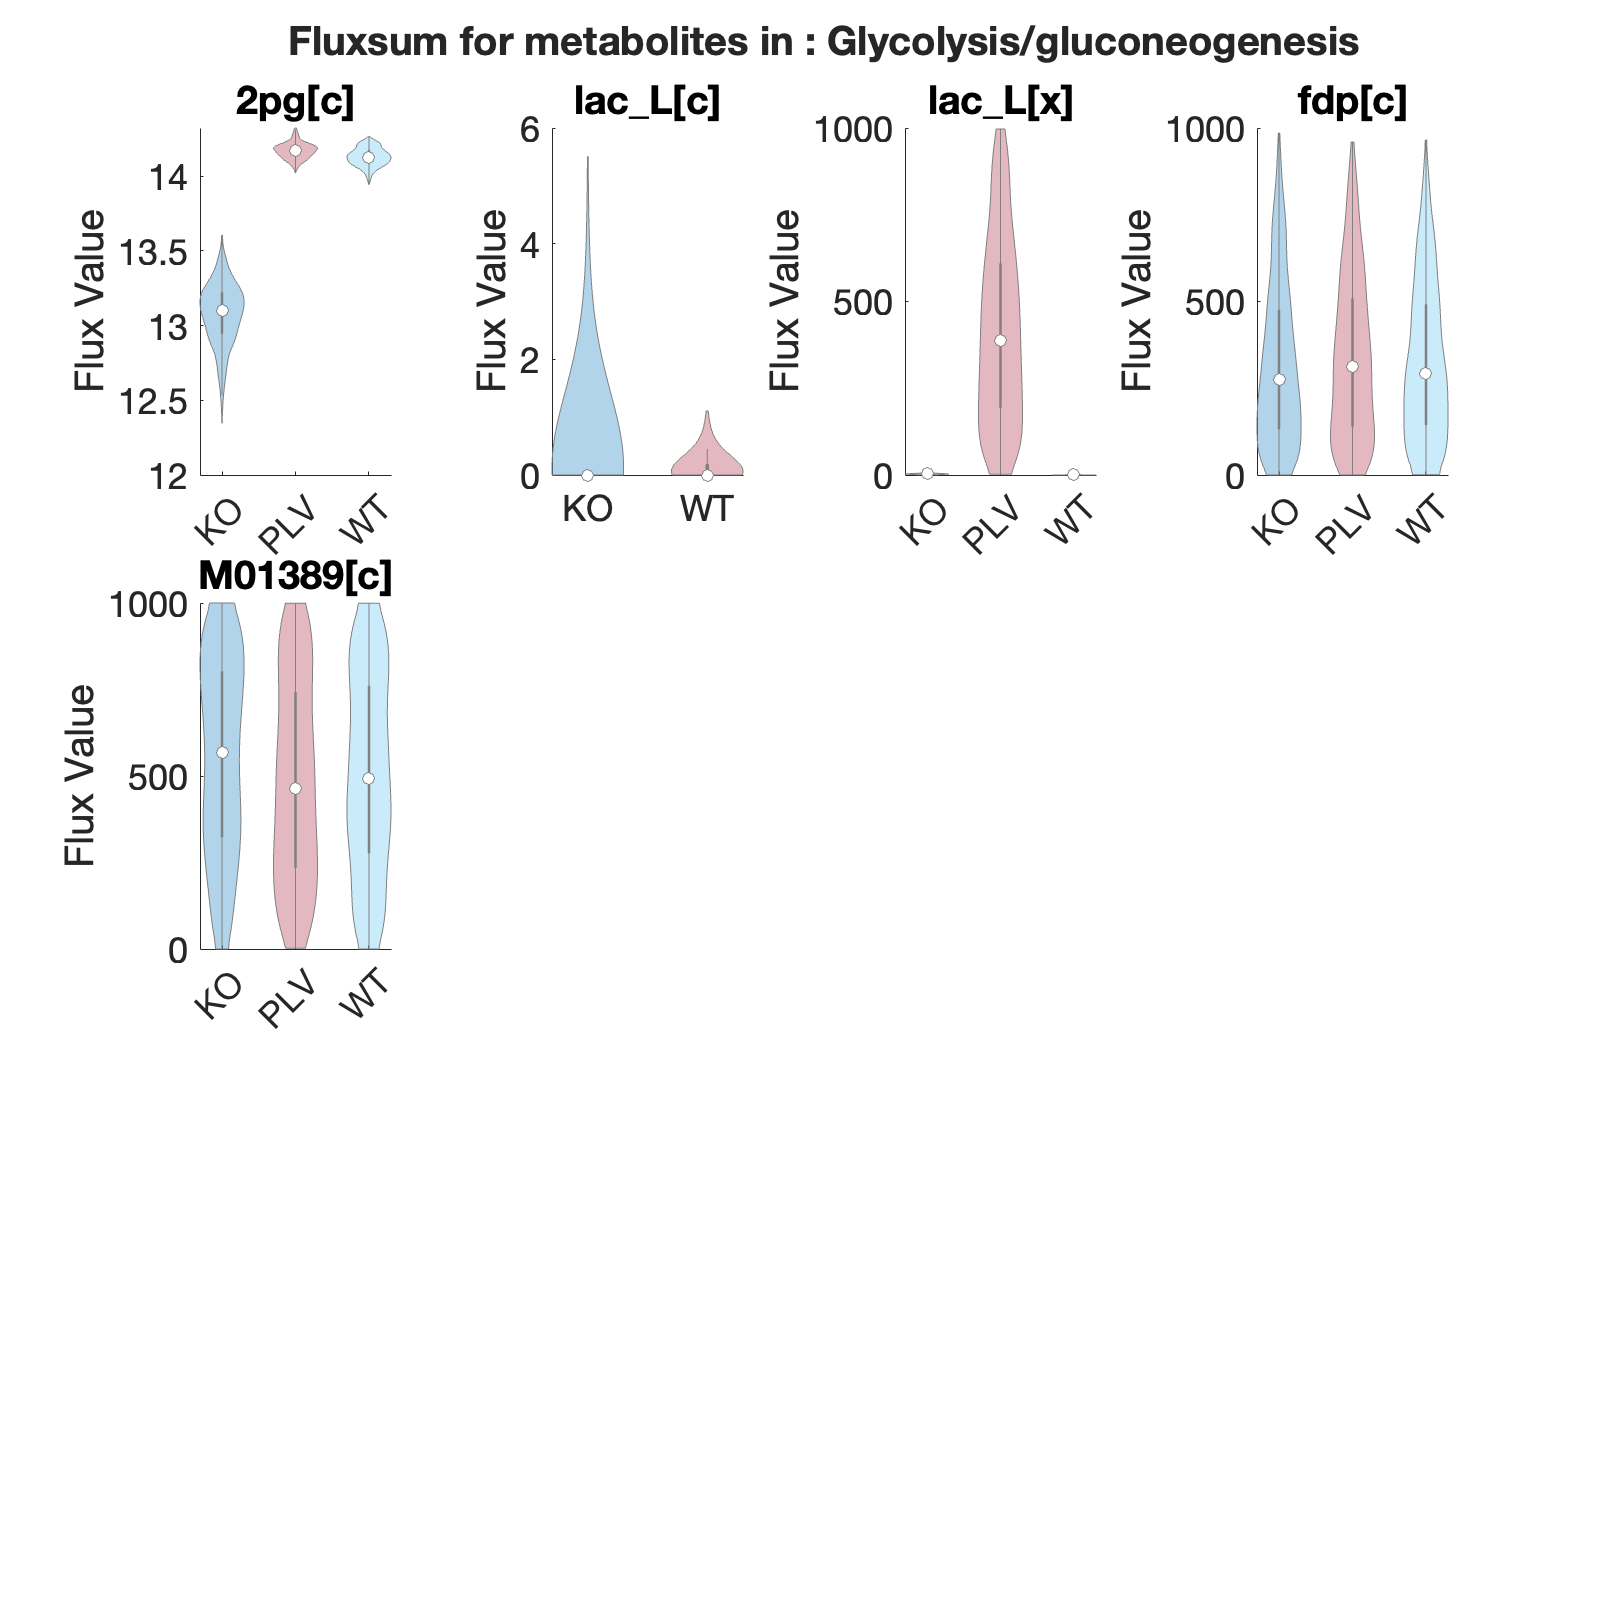

show_figure(plots.sampling.violing_fluxsum_Glycolysisgluconeogenesis.fig1); show_figure(plots.sampling.violing_fluxsum_Glycolysisgluconeogenesis.fig2);show_figure(plots.sampling.violing_fluxsum_Glycolysisgluconeogenesis.fig3)